# **Project**

# 'Uncompensated System'

numg=[1]; % Generate numerator of G(s).
deng=[1 14 48 80]; % Generate denominator of G(s).
G=tf(numg,deng) % Create and display G(s).

G =
 
             1
  ------------------------
  s^3 + 14 s^2 + 48 s + 80
 
연속시간 전달 함수입니다.



s = tf('s');

pos=10.1;
z=0.589

z = 0.5890

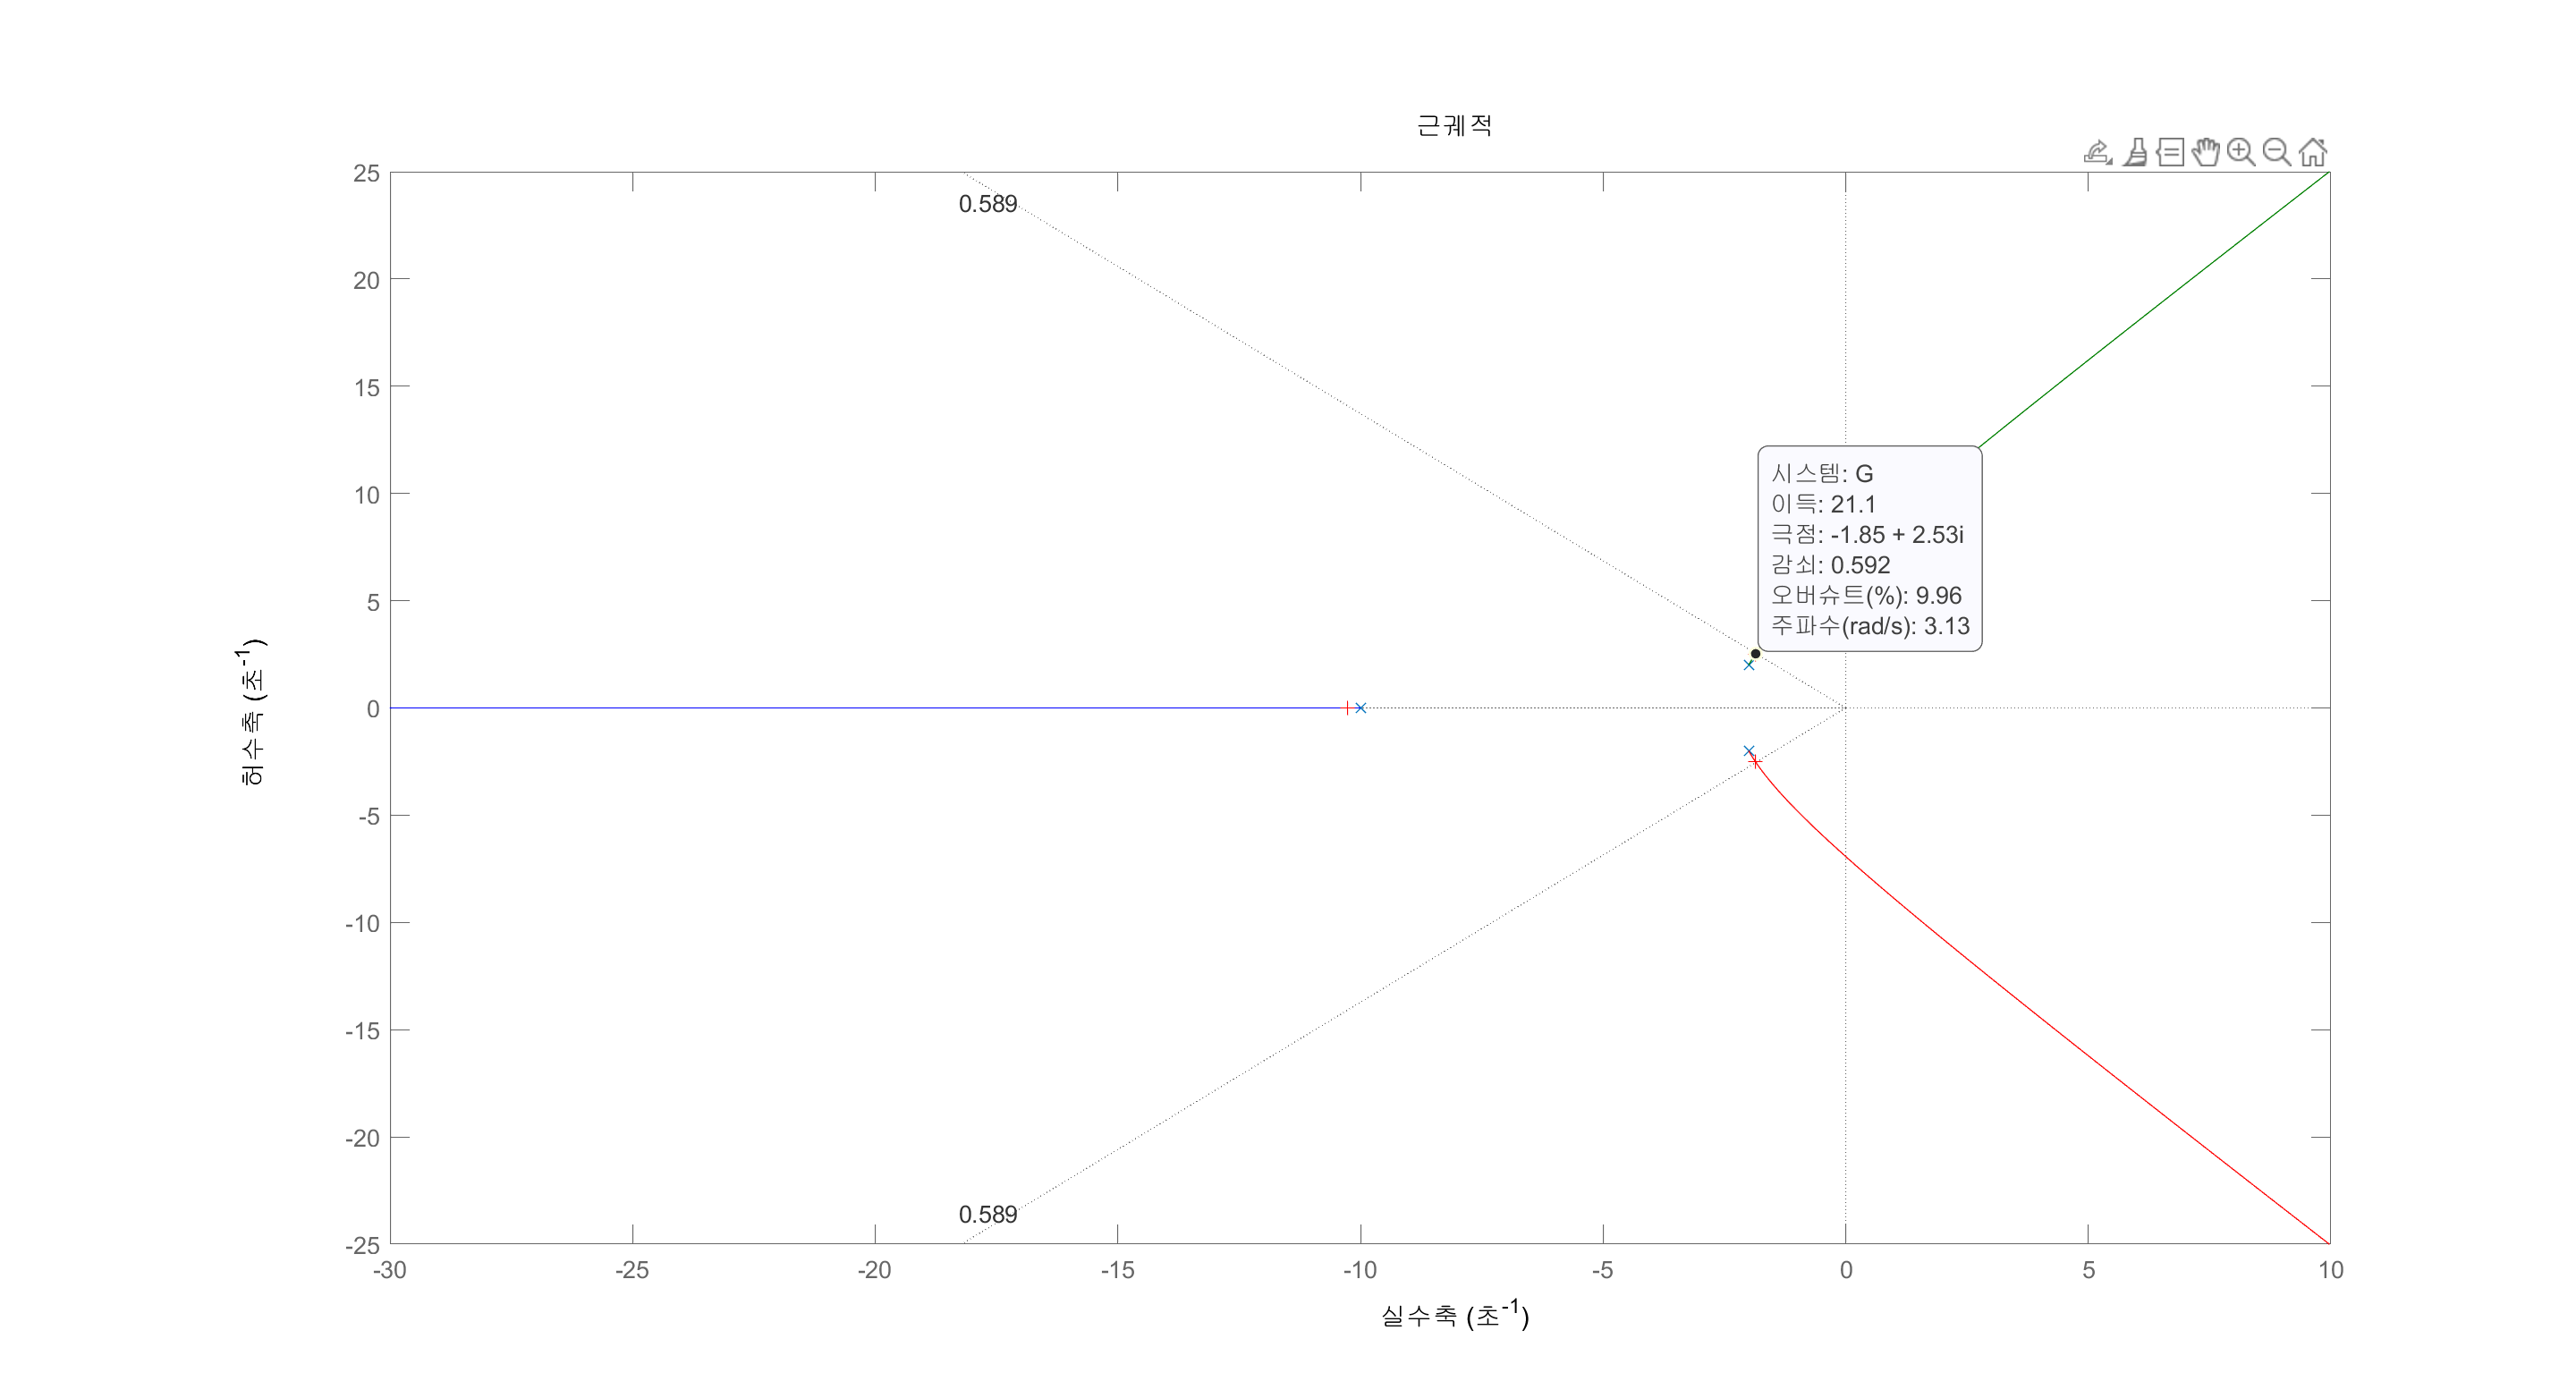

Select a point in the graphics window


selected_point = -1.8618 + 2.5021i

K = 19.9714

p =  -10.2755 + 0.0000i
  -1.8622 + 2.5022i
  -1.8622 - 2.5022i


rlocus(G) % Plot uncompensated root locus.
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(G) 

p; % Display closed-loop poles.'

complex f;
f=-1.8388+2.4919i;
gain=24; 
estimated_settling_time=4/abs(real(f))

estimated_settling_time = 2.1753

estimated_peak_time=pi/abs(imag(f))

estimated_peak_time = 1.2607

estimated_percent_overshoot=pos

estimated_percent_overshoot = 10.1000

estimated_damping_ratio=z 

estimated_damping_ratio = 0.5890

estimated_natural_frequency=sqrt(real(f)^2+imag(f)^2)

estimated_natural_frequency = 3.0969


K = 24;
numkp=numg ;% Set up numerator to evaluate Kv.
denkp=deng ;% Set up denominator to evaluate Kv.
G=tf(numkp,denkp) % Create sG(s).

G =
 
             1
  ------------------------
  s^3 + 14 s^2 + 48 s + 80
 
연속시간 전달 함수입니다.



G=minreal(G); % Cancel common poles and zeros.
Kp=dcgain(K*G) % Display uncompensated Kv.

Kp = 0.3000

ess=1/(1+Kp) % Display uncompensated steady-state error

ess = 0.7692

T=feedback(K*G,1) % Find uncompensated T(s).

T =
 
             24
  -------------------------
  s^3 + 14 s^2 + 48 s + 104
 
연속시간 전달 함수입니다.



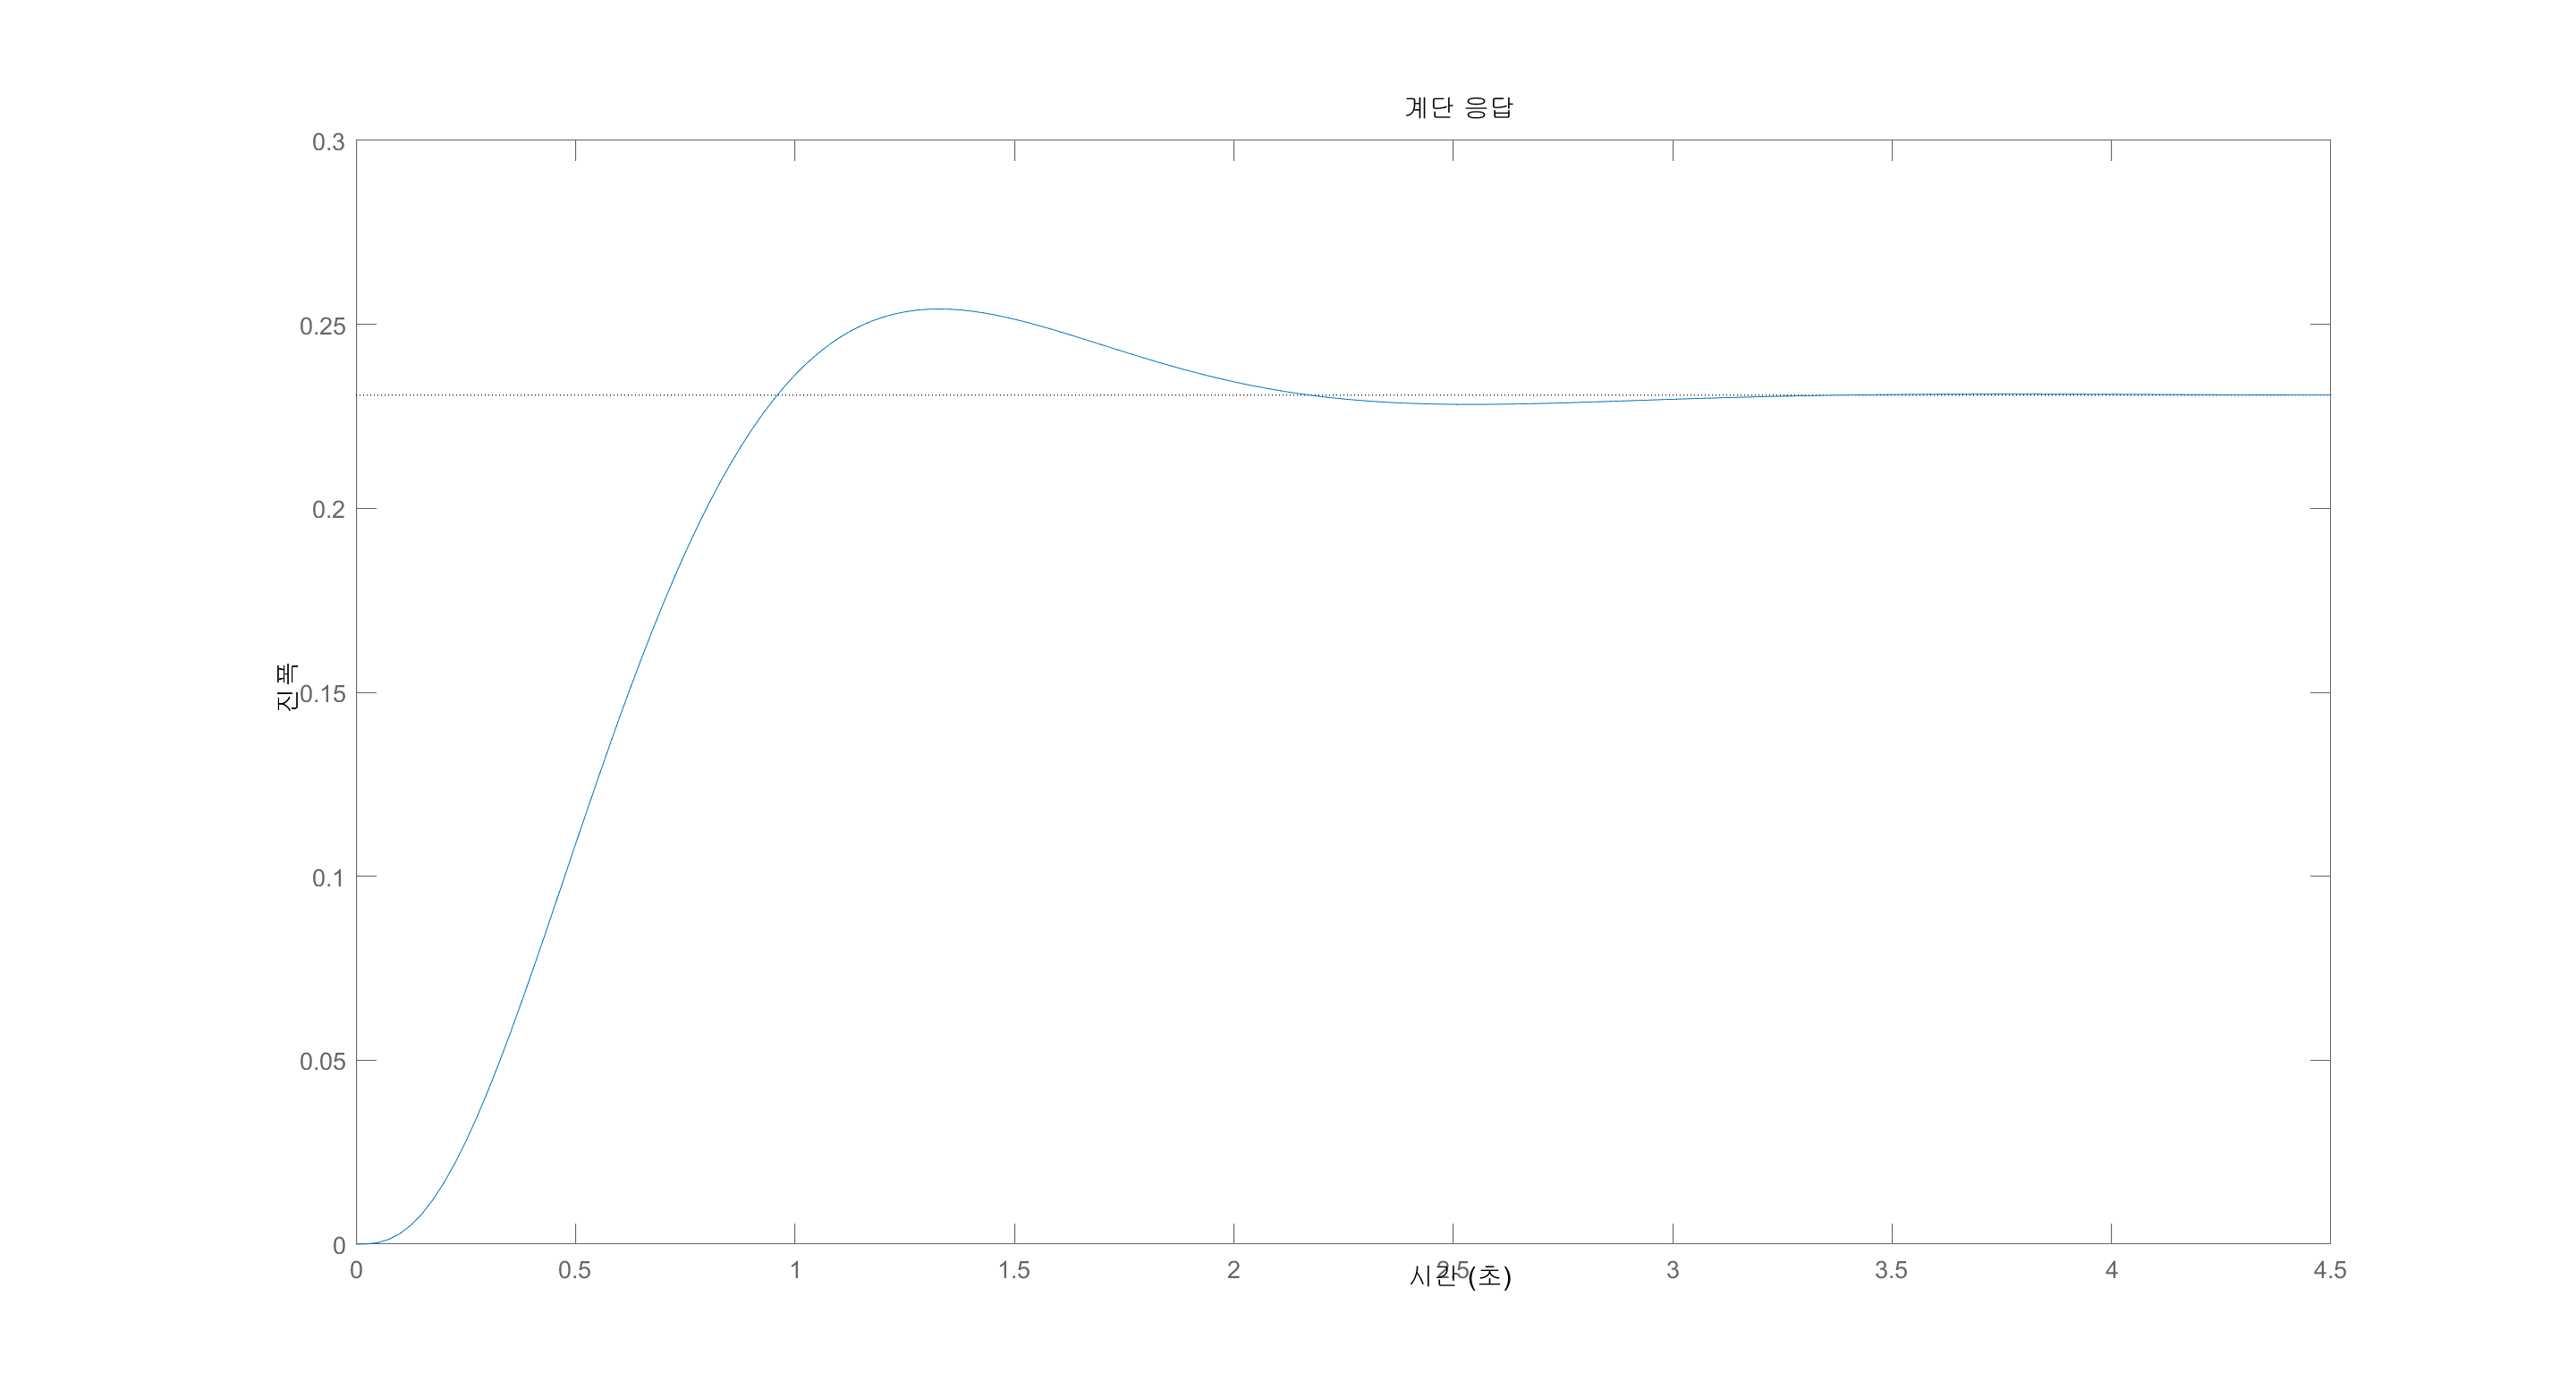

step(T); % Plot step response of

stepinfo(T)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.6027
    TransientTime: 1.9640
     SettlingTime: 1.9640
      SettlingMin: 0.2119
      SettlingMax: 0.2542
        Overshoot: 10.1500
       Undershoot: 0
             Peak: 0.2542
         PeakTime: 1.3291


ans = 'Lead Compensator System'

# 'Lead Compensator System'

numg=[1]; % Generate numerator of G(s).
deng=poly([-2+2i -2-2i -10]);
G=tf(numg,deng) % Create and display G(s).

G =
 
             1
  ------------------------
  s^3 + 14 s^2 + 48 s + 80
 
연속시간 전달 함수입니다.



s = tf('s');
pos=22;
z=0.589

z = 0.5890

rlocus(G) % Plot uncompensated root locus.
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(G) 

Select a point in the graphics window


selected_point = -1.8433 + 2.5021i

K = 20.2150

p =  -10.2787 + 0.0000i
  -1.8607 + 2.5075i
  -1.8607 - 2.5075i


p; % Display closed-loop poles.'

Ts=1;
wn=4/(Ts*z) % Calculate natural frequency.

wn = 6.7912

desired_pole=(-z*wn)+(wn*sqrt(1-z^2)*i)

desired_pole = -4.0000 + 5.4882i


numc=[1 3]; % Calculate numerator of Gc(s).
denc=[1 28]; % Calculate denominator of Gc(s).
Gc=tf (numc,denc) % Create and display Gc(s).

Gc =
 
  s + 3
  ------
  s + 28
 
연속시간 전달 함수입니다.



Ge=G*Gc % Cascade G(s) and Gc(s).

Ge =
 
                  s + 3
  --------------------------------------
  s^4 + 42 s^3 + 440 s^2 + 1424 s + 2240
 
연속시간 전달 함수입니다.



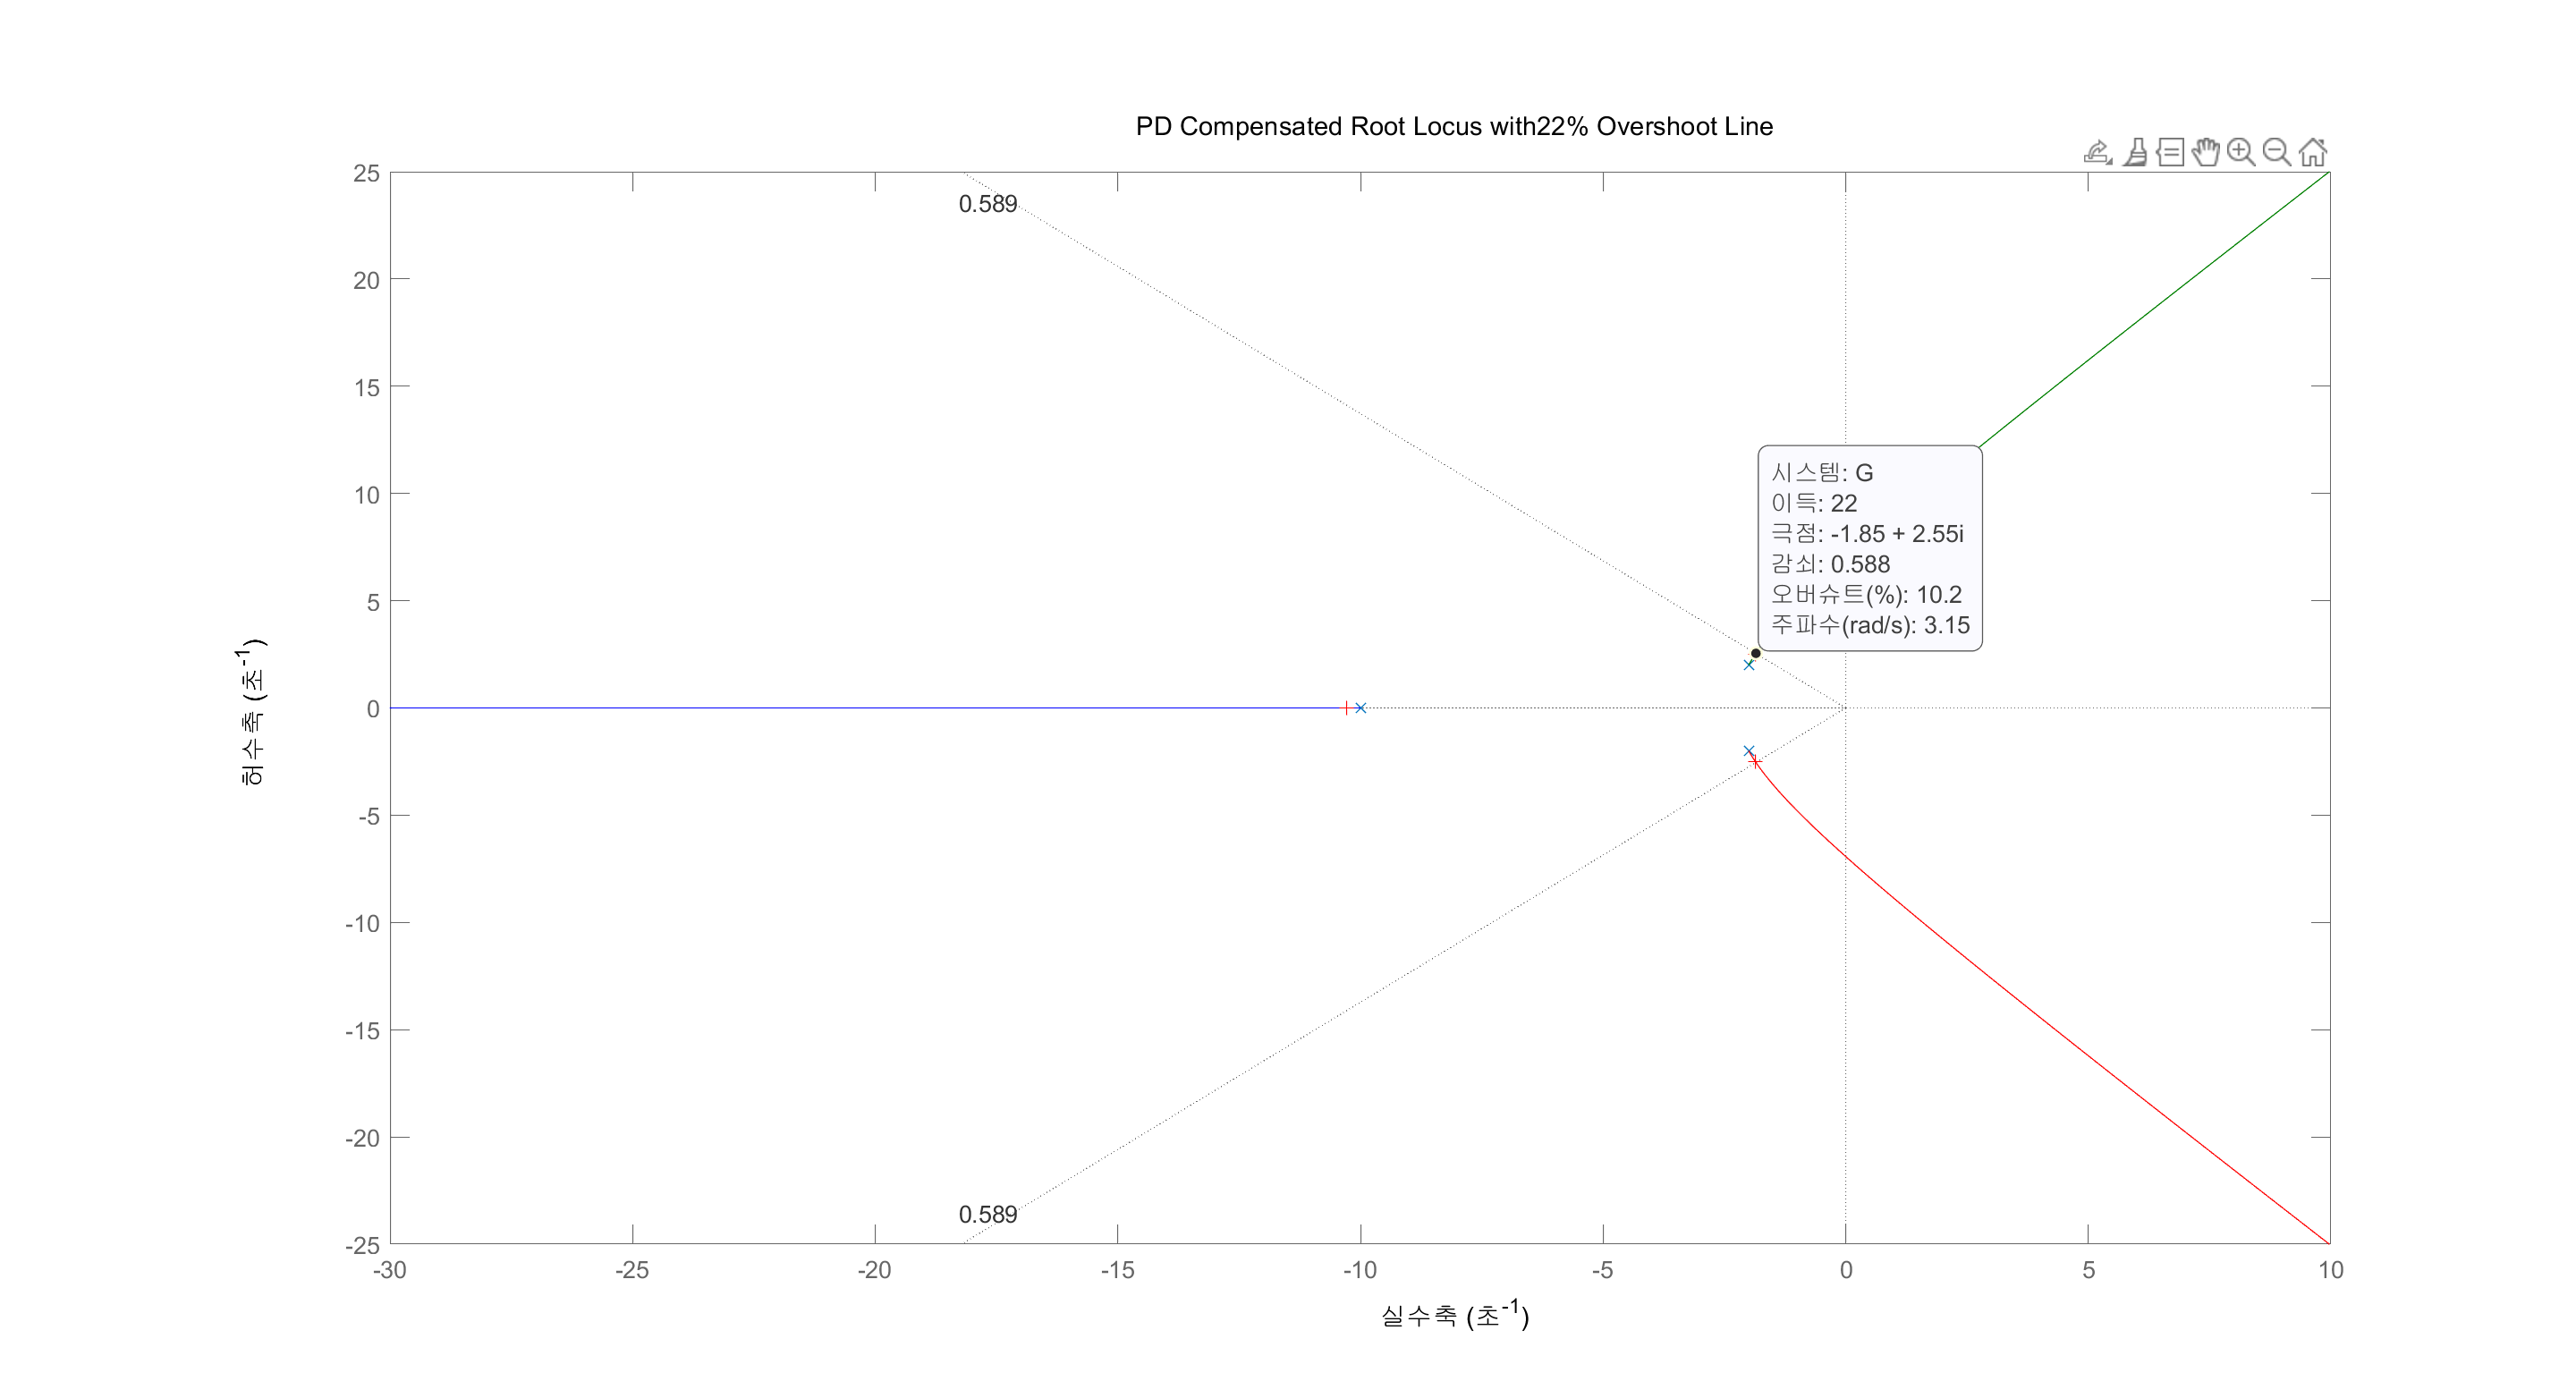


title (['PD Compensated Root Locus with', num2str(pos),...
'% Overshoot Line']) % Add title to PD compensated root

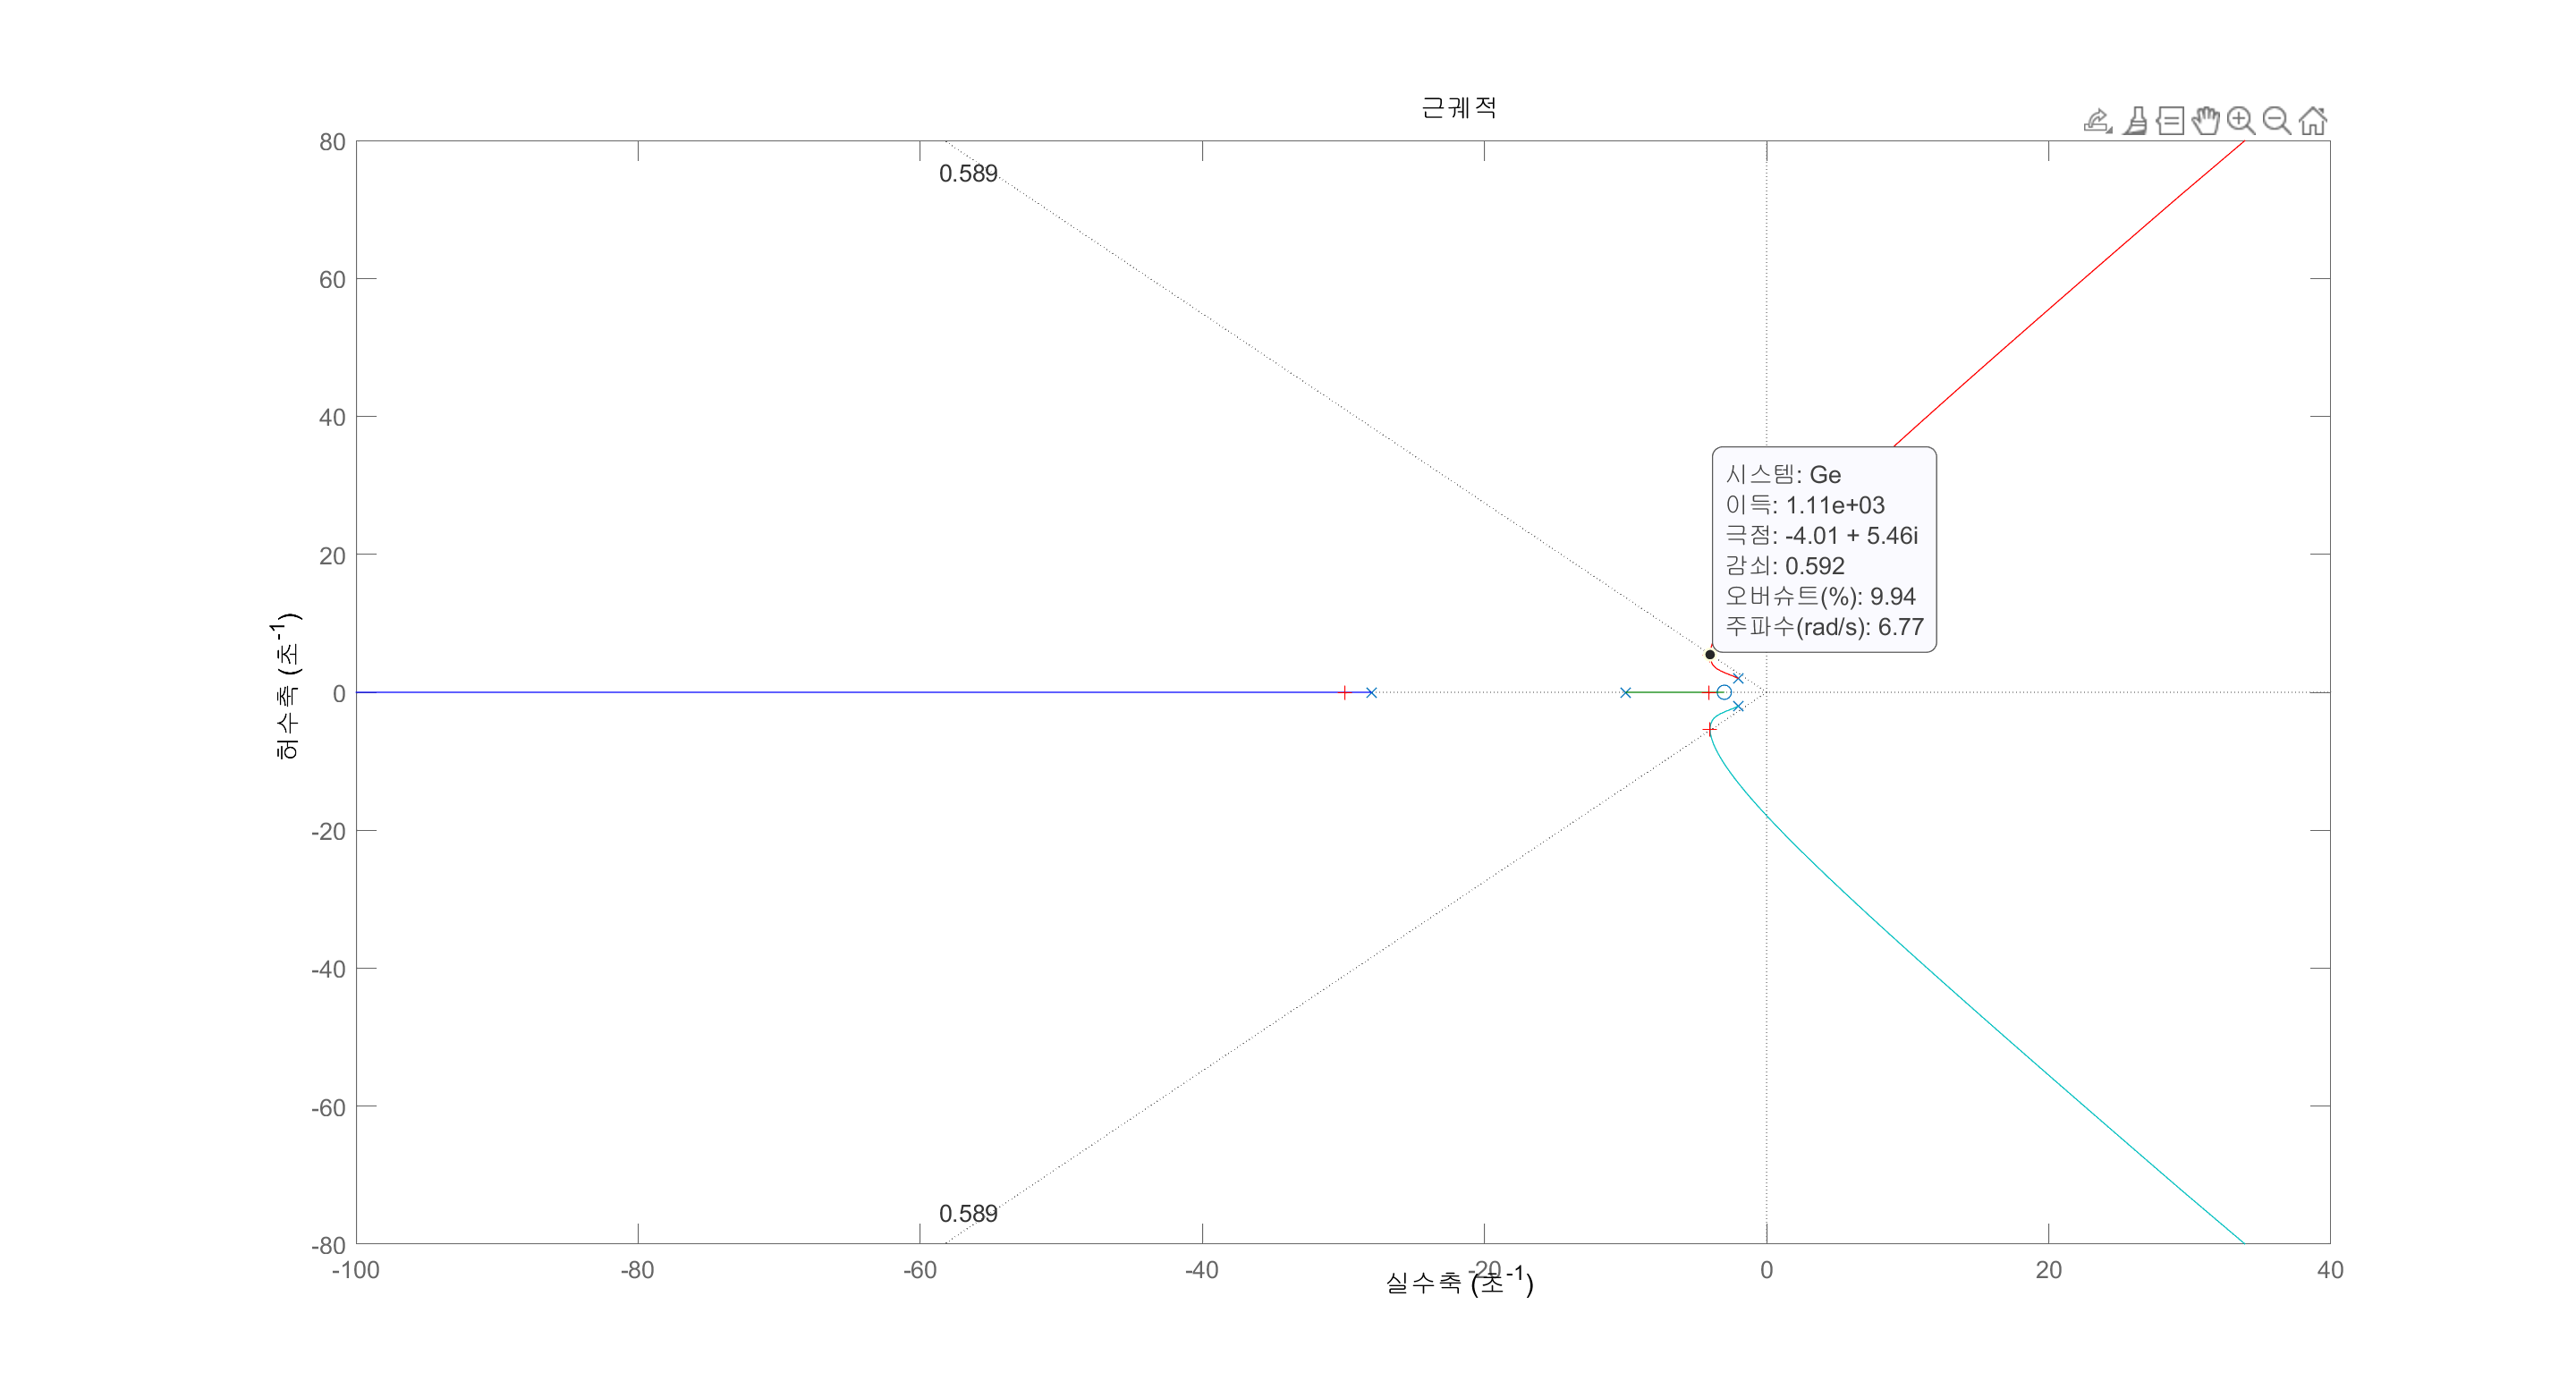

Select a point in the graphics window


selected_point = -3.9719 + 5.3809i

K = 1.0880e+03

p =  -29.8825 + 0.0000i
  -4.0161 + 5.3812i
  -4.0161 - 5.3812i
  -4.0854 + 0.0000i


rlocus(Ge) % Plot root locus of PD compensated
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(Ge) % Generate gain, K, and closed-loop

K = 1140

K = 1140


Kp=dcgain(K*Ge) % Display uncompensated Kp.

Kp = 1.5268

ess=1/(1+Kp) % Display uncompensated steady state error

ess = 0.3958


T=feedback(K*Ge,1) % Find uncompensated T(s).

T =
 
              1140 s + 3420
  --------------------------------------
  s^4 + 42 s^3 + 440 s^2 + 2564 s + 5660
 
연속시간 전달 함수입니다.



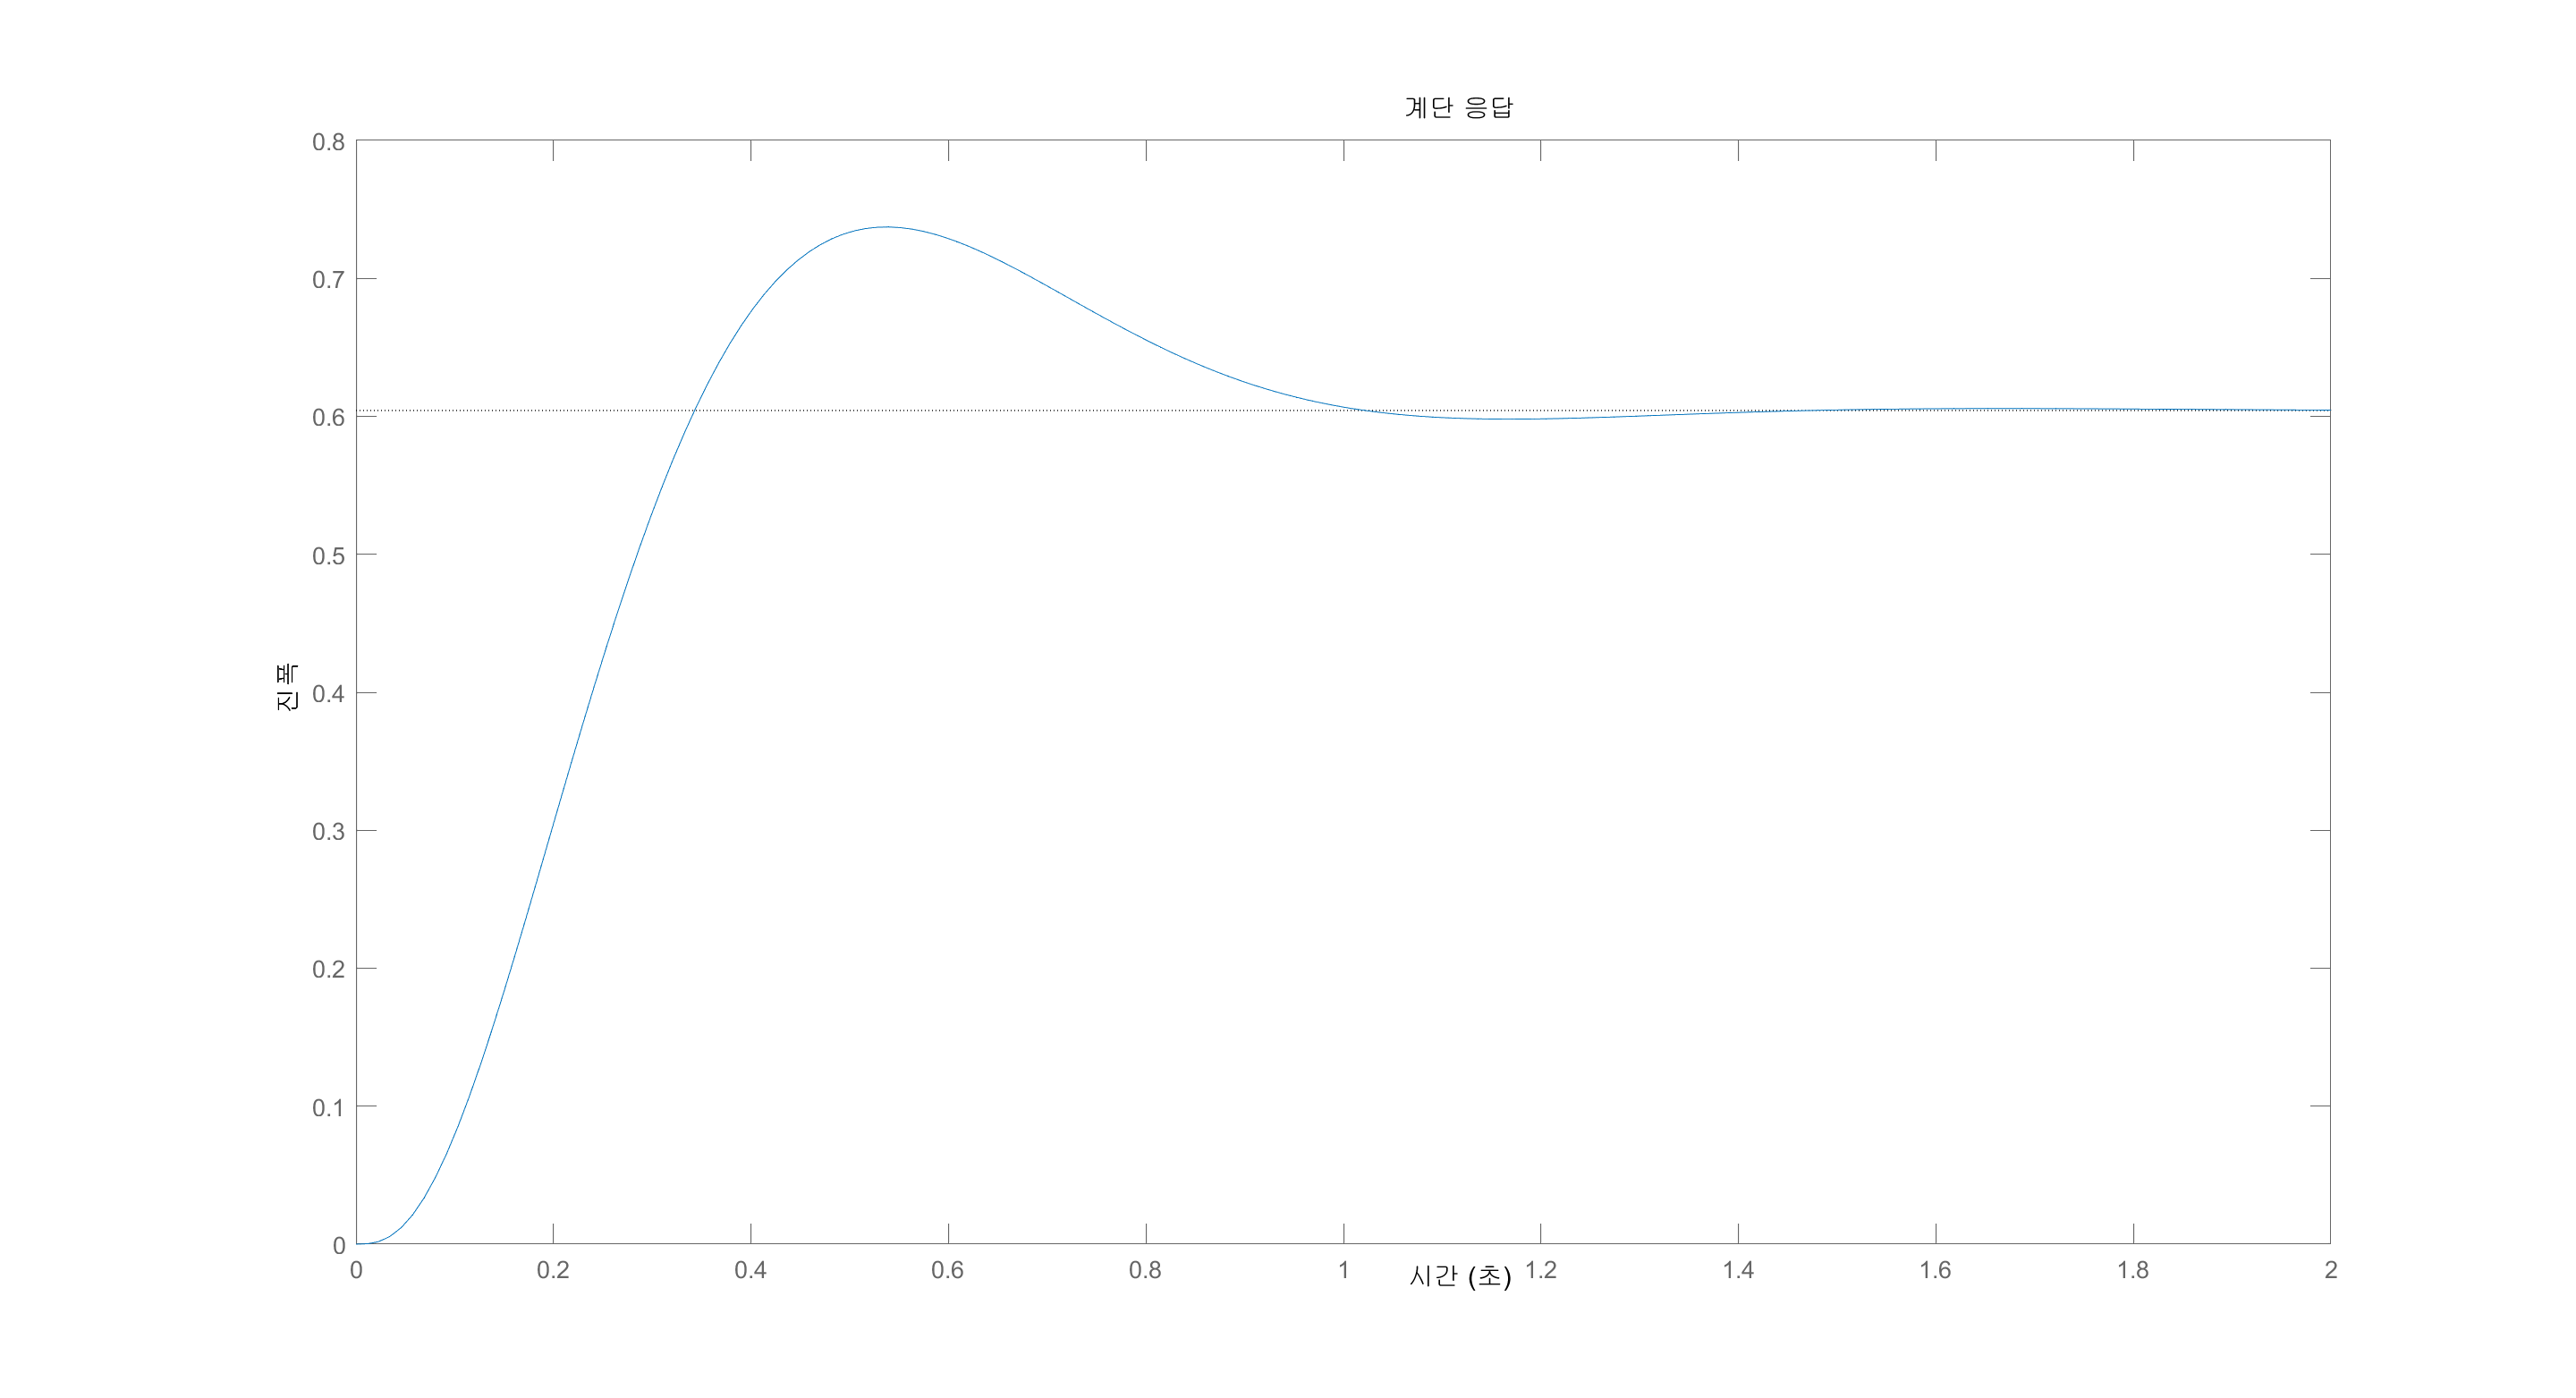

step(T); % Plot step response of

stepinfo(T)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.2188
    TransientTime: 0.9389
     SettlingTime: 0.9389
      SettlingMin: 0.5487
      SettlingMax: 0.7373
        Overshoot: 22.0156
       Undershoot: 0
             Peak: 0.7373
         PeakTime: 0.5394


# Lag compensated System

numg=[1]; % Generate numerator of G(s).
deng=poly([-2+2i -2-2i -10]);
G=tf(numg,deng) % Create and display G(s).

G =
 
             1
  ------------------------
  s^3 + 14 s^2 + 48 s + 80
 
연속시간 전달 함수입니다.



s = tf('s');
pos=22;
z=0.589

z = 0.5890

rlocus(G) % Plot uncompensated root locus.
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(G) 

Select a point in the graphics window


selected_point = -1.8433 + 2.5021i

K = 20.2150

p =  -10.2787 + 0.0000i
  -1.8607 + 2.5075i
  -1.8607 - 2.5075i


p; % Display closed-loop poles.'

Ts=1;
wn=4/(Ts*z) % Calculate natural frequency.

wn = 6.7912

desired_pole=(-z*wn)+(wn*sqrt(1-z^2)*i)

desired_pole = -4.0000 + 5.4882i


numc=[1 3.03]; % Calculate numerator of Gc(s).
denc=[1 0.3]; % Calculate denominator of Gc(s).
Gc=tf (numc,denc) % Create and display Gc(s).

Gc =
 
  s + 3.03
  --------
  s + 0.3
 
연속시간 전달 함수입니다.



Ge=G*Gc % Cascade G(s) and Gc(s).

Ge =
 
                 s + 3.03
  ---------------------------------------
  s^4 + 14.3 s^3 + 52.2 s^2 + 94.4 s + 24
 
연속시간 전달 함수입니다.



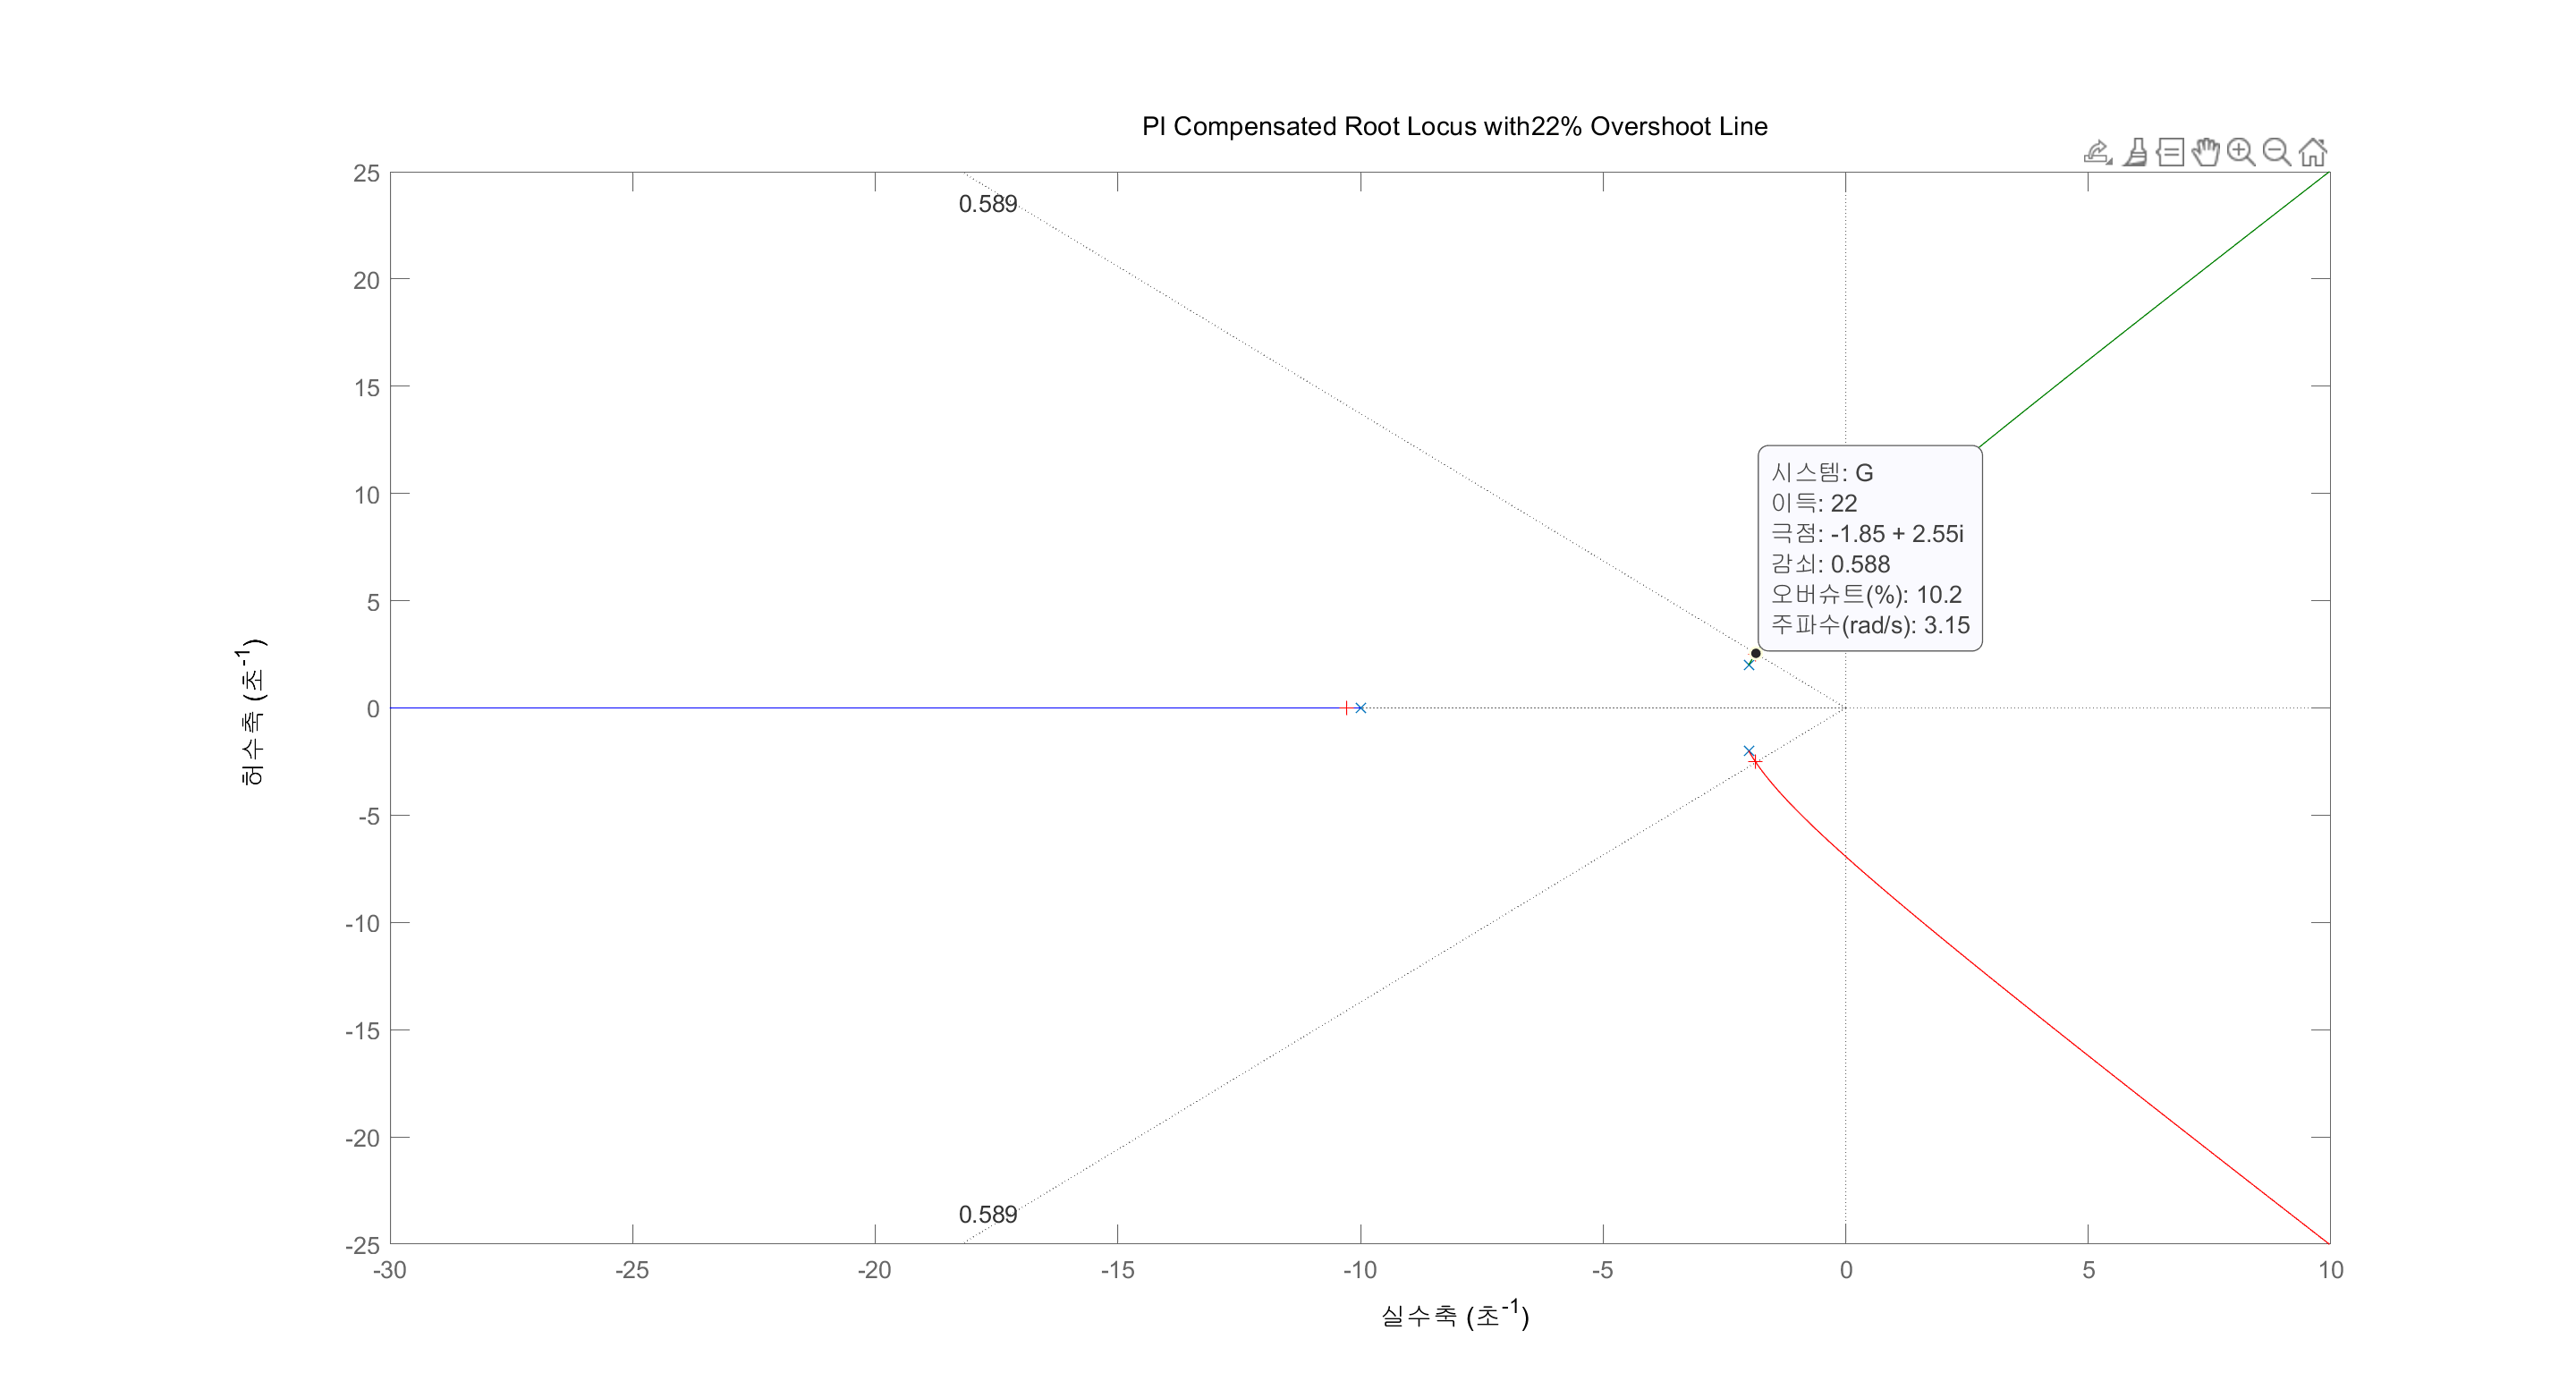


title (['PI Compensated Root Locus with', num2str(pos),...
'% Overshoot Line']) % Add title to PD compensated root

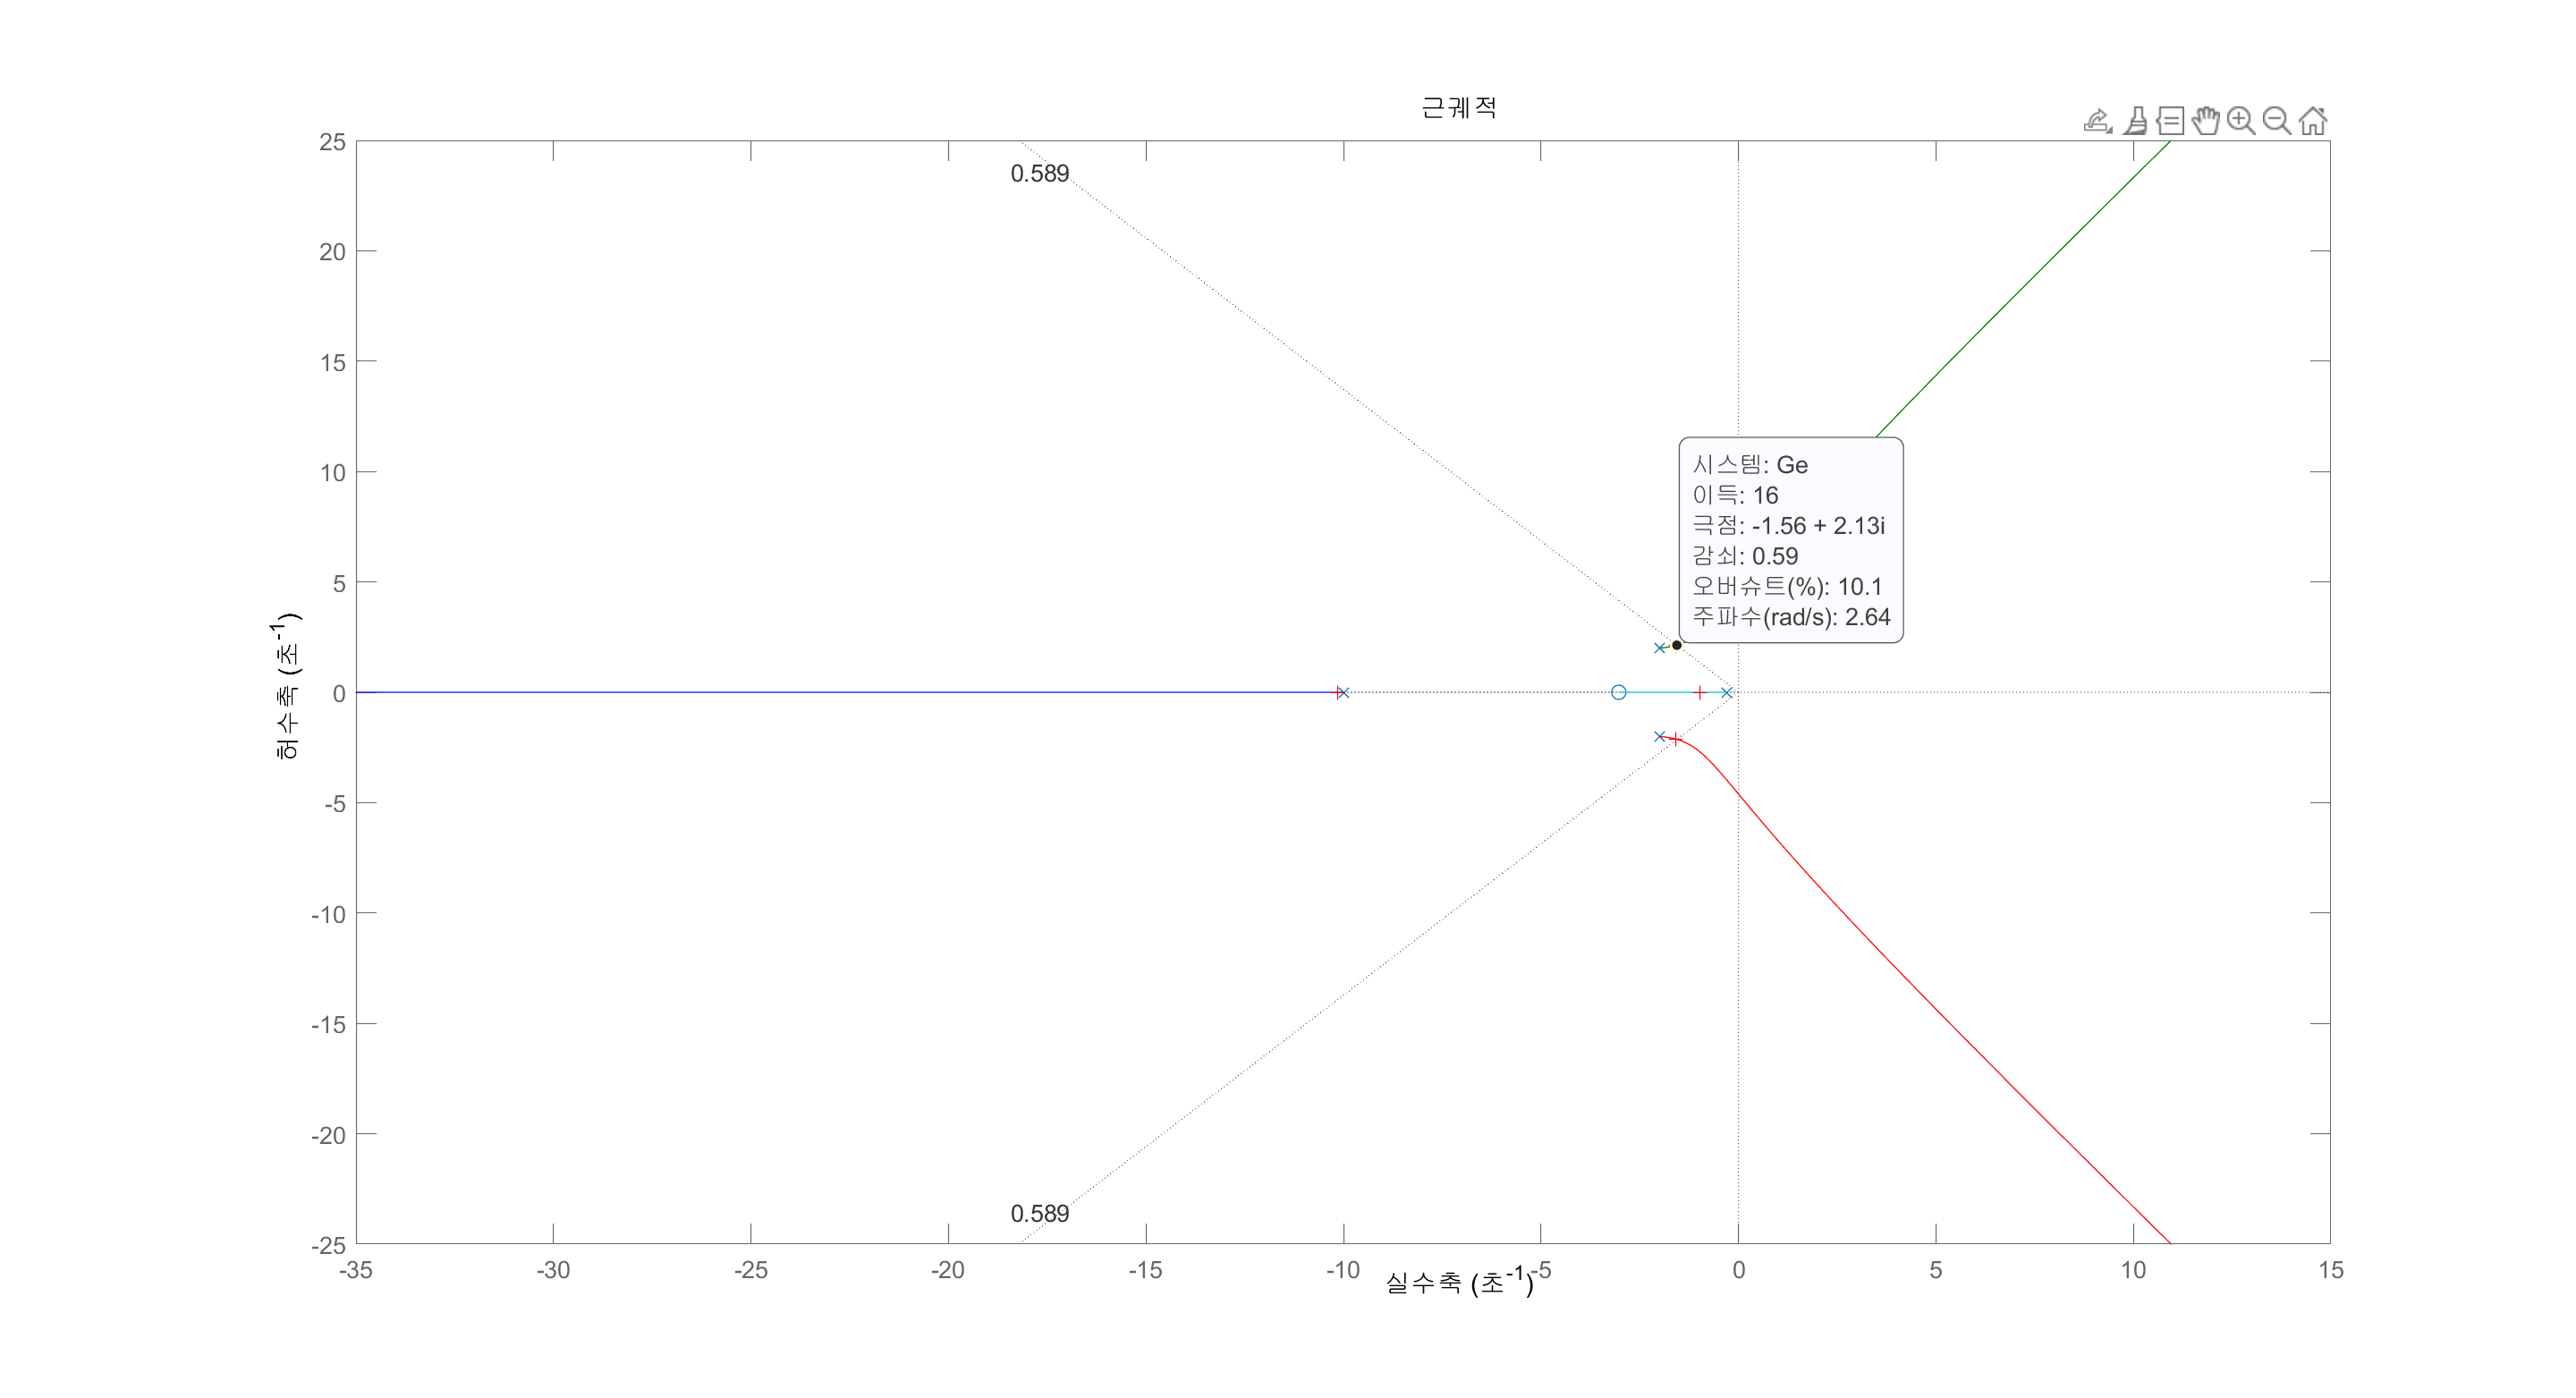

Select a point in the graphics window


selected_point = -1.5648 + 2.0867i

K = 15.1670

p =  -10.1555 + 0.0000i
  -1.5803 + 2.1222i
  -1.5803 - 2.1222i
  -0.9840 + 0.0000i


rlocus(Ge) % Plot root locus of PD compensated
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(Ge) % Generate gain, K, and closed-loop

K = 20

K = 20


Kp=dcgain(K*Ge) % Display uncompensated Kp.

Kp = 2.5250

ess=1/(1+Kp) % Display uncompensated steady state error

ess = 0.2837


T=feedback(K*Ge,1) % Find uncompensated T(s).

T =
 
                 20 s + 60.6
  ------------------------------------------
  s^4 + 14.3 s^3 + 52.2 s^2 + 114.4 s + 84.6
 
연속시간 전달 함수입니다.



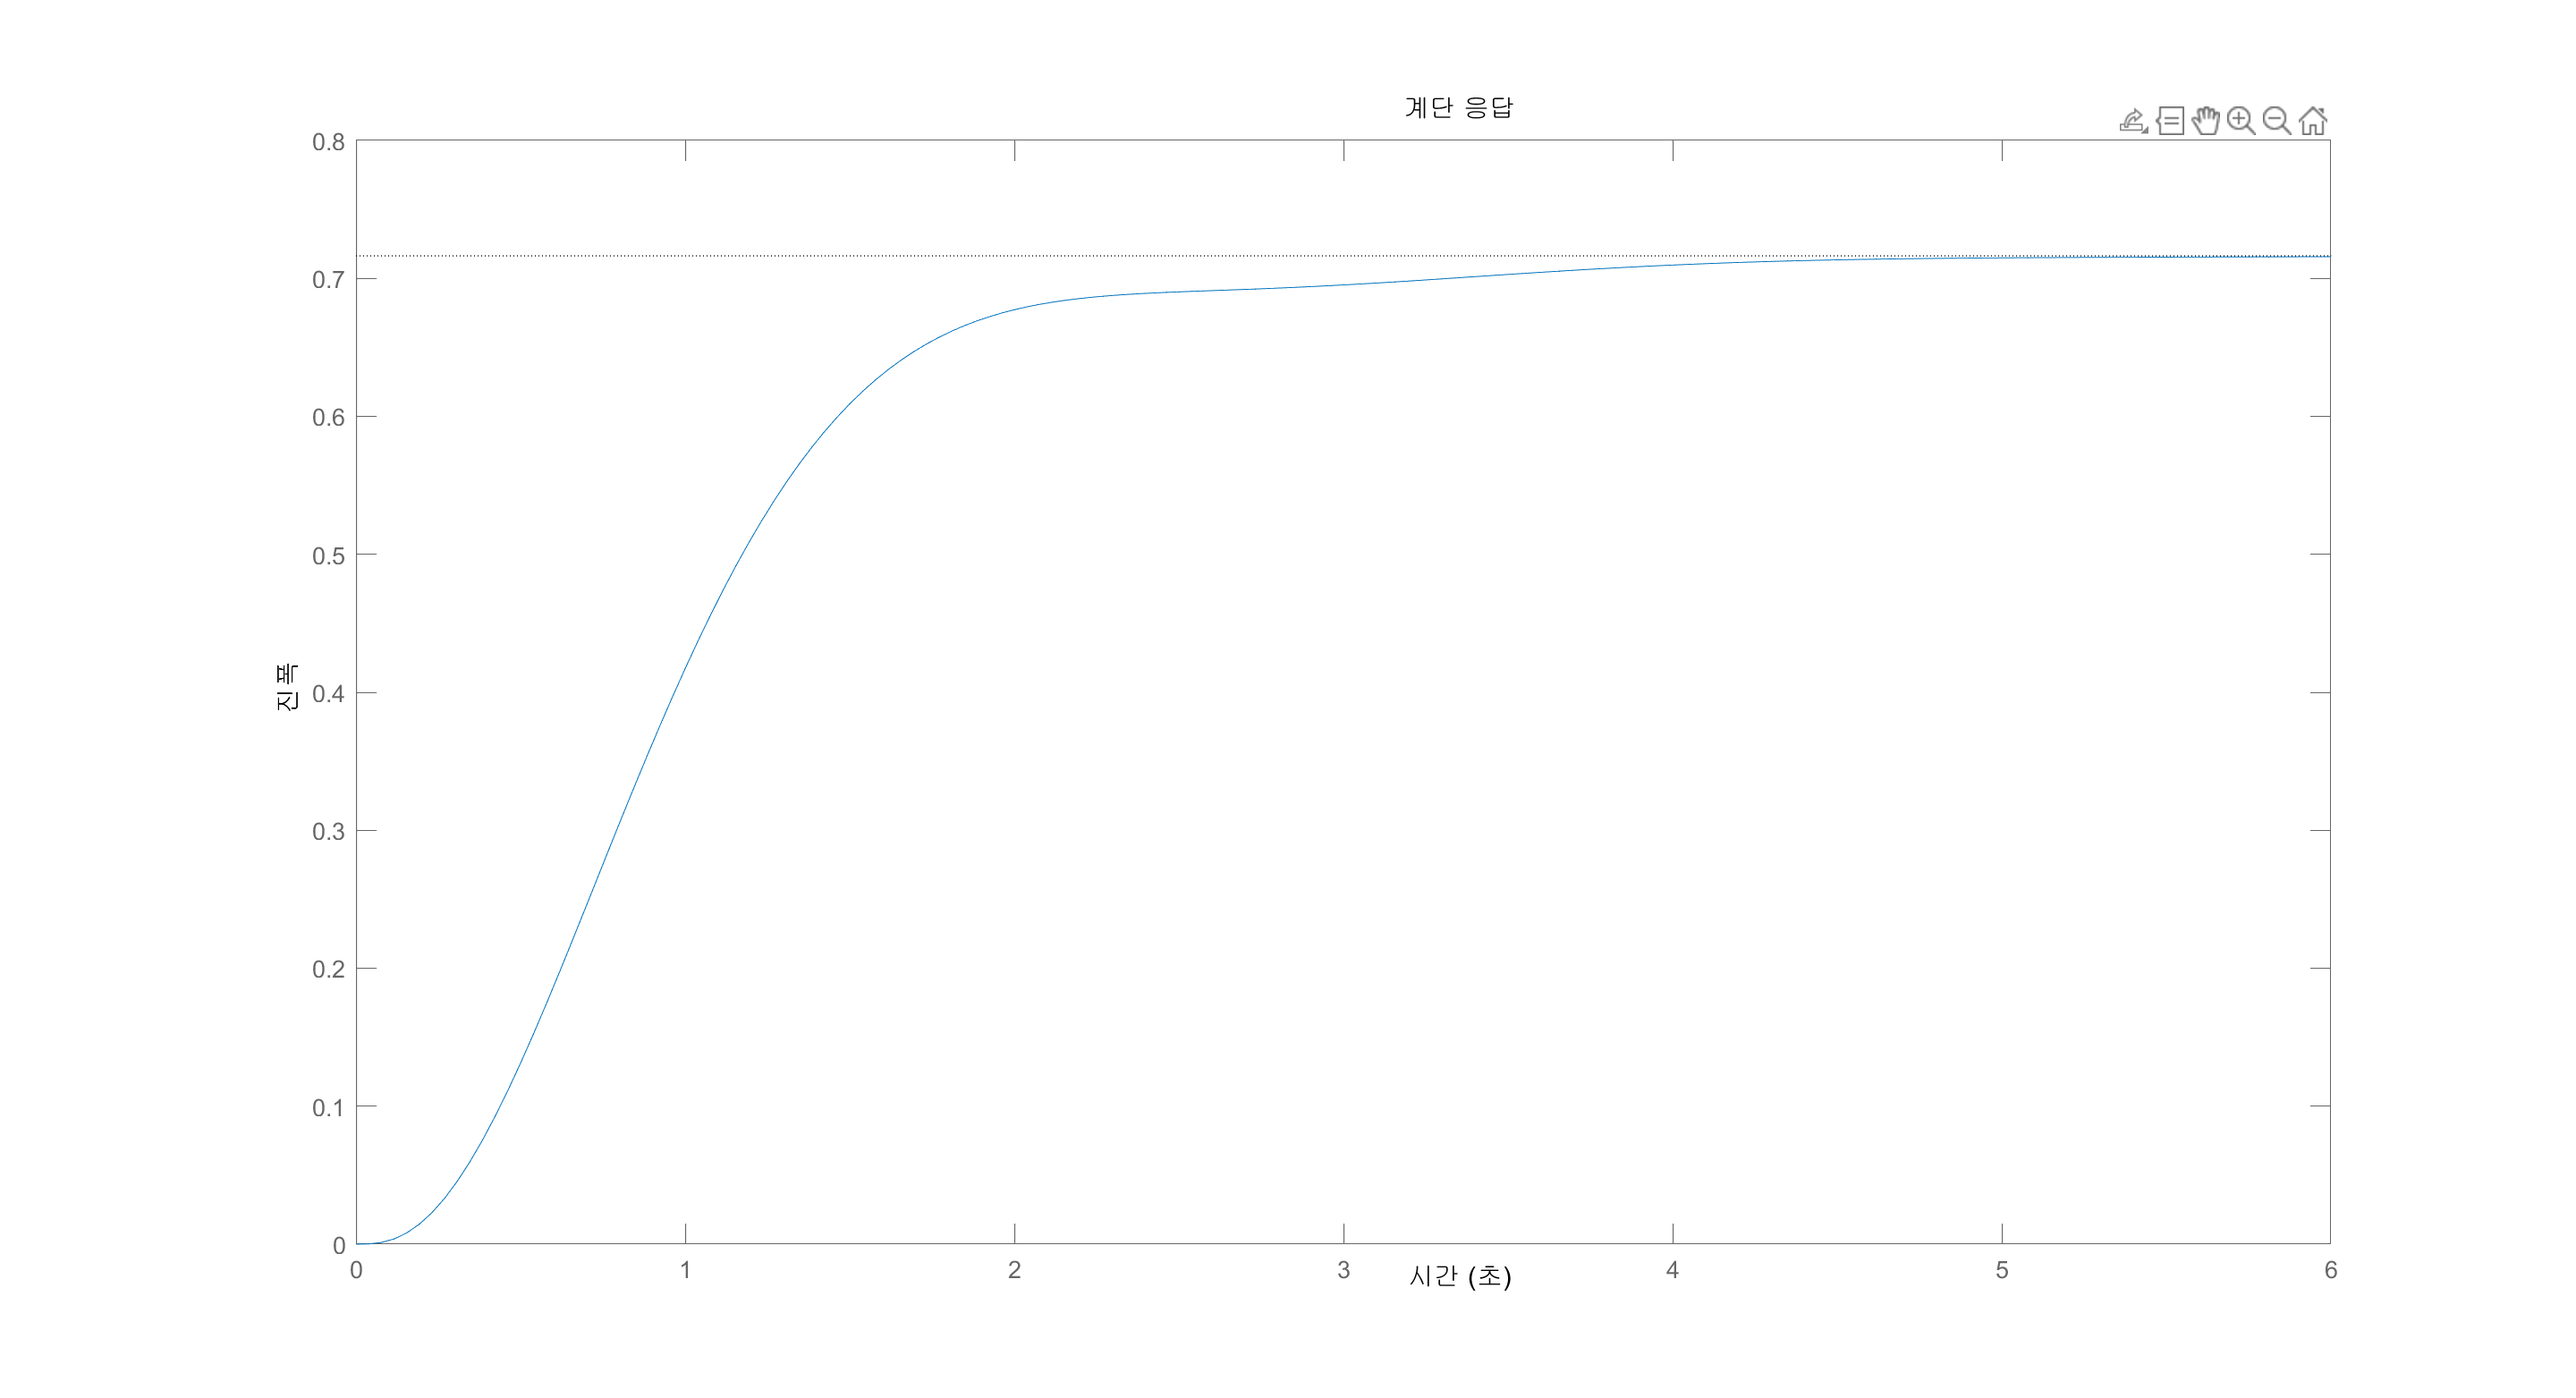

step(T); % Plot step response of

stepinfo(T)

ans = 다음 필드를 포함한 struct :
         RiseTime: 1.3054
    TransientTime: 3.4448
     SettlingTime: 3.4448
      SettlingMin: 0.6467
      SettlingMax: 0.7161
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7161
         PeakTime: 6.8888


# Lead-Lag Compensated System


numg=[1]; % Generate numerator of G(s).
deng=poly([-2+2i -2-2i -10]);
G=tf(numg,deng) % Create and display G(s).

G =
 
             1
  ------------------------
  s^3 + 14 s^2 + 48 s + 80
 
연속시간 전달 함수입니다.



s = tf('s');
pos=22;
z=0.439;
K = 1140;
Ts=1.5;
wn=4/(Ts*z) % Calculate natural frequency.

wn = 6.0744

desired_pole=(-z*wn)+(wn*sqrt(1-z^2)*i);

numl = [1 3];
denl=[1 28]; % Calculate denominator of Gc(s).
Glead = tf(numl, denl)

Glead =
 
  s + 3
  ------
  s + 28
 
연속시간 전달 함수입니다.




numc = [1 3.03];
denc=[1 0.3]; % Calculate denominator of Gc(s).
Glag=tf (numc,denc) % Create and display Gc(s).

Glag =
 
  s + 3.03
  --------
  s + 0.3
 
연속시간 전달 함수입니다.



Ge=G.*Glead.*Glag % Cascade G(s) and Gc(s).

Ge =
 
                  s^2 + 6.03 s + 9.09
  ----------------------------------------------------
  s^5 + 42.3 s^4 + 452.6 s^3 + 1556 s^2 + 2667 s + 672
 
연속시간 전달 함수입니다.



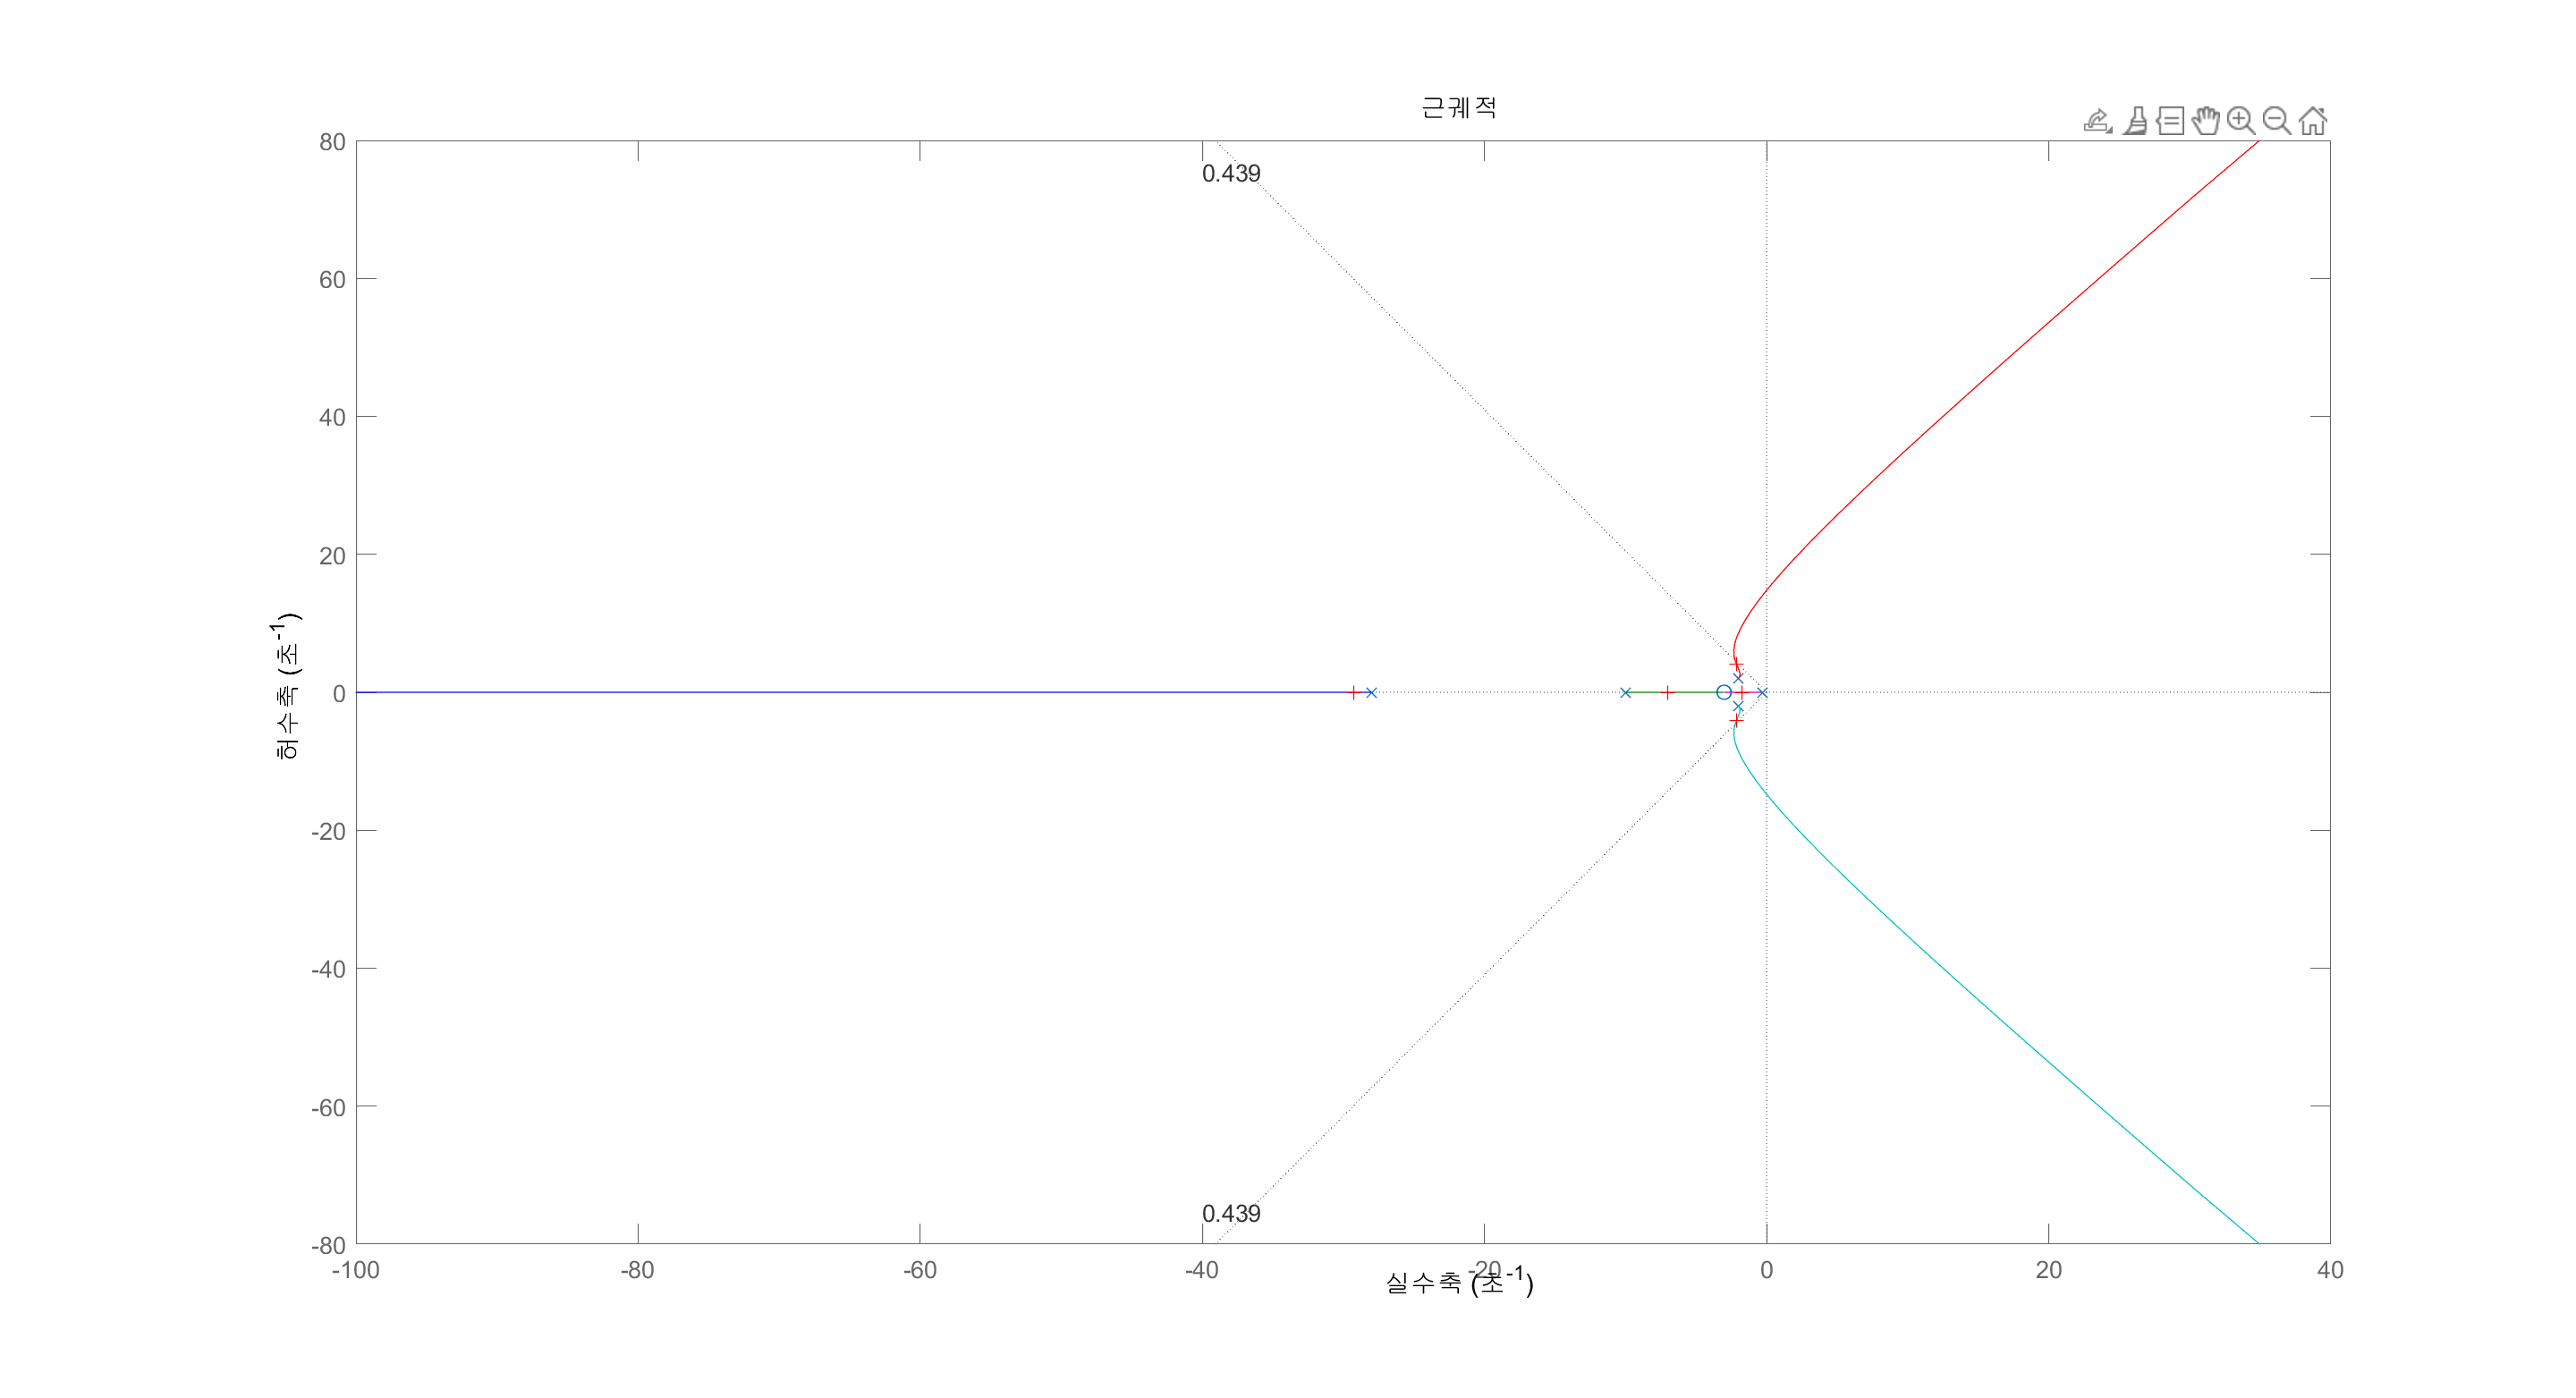

Select a point in the graphics window


selected_point = -2.2600 + 4.0843i

Kest = 766.1161

p =  -29.2657 + 0.0000i
  -7.0158 + 0.0000i
  -2.1443 + 4.1111i
  -2.1443 - 4.1111i
  -1.7298 + 0.0000i



rlocus(Ge) % Plot uncompensated root locus.
sgrid(0.439,0) % Overlay desired percent
[Kest,p]=rlocfind(Ge) 


Kp=dcgain(K*Ge) % Display uncompensated Kv.

Kp = 15.4205

ess=1/(1+Kp) % Display uncompensated

ess = 0.0609

ess_15 = 1/(1+15)

ess_15 = 0.0625


T=feedback(K*Ge,1) % Find uncompensated T(s).

T =
 
                1140 s^2 + 6874 s + 1.036e04
  ---------------------------------------------------------
  s^5 + 42.3 s^4 + 452.6 s^3 + 2696 s^2 + 9541 s + 1.103e04
 
연속시간 전달 함수입니다.



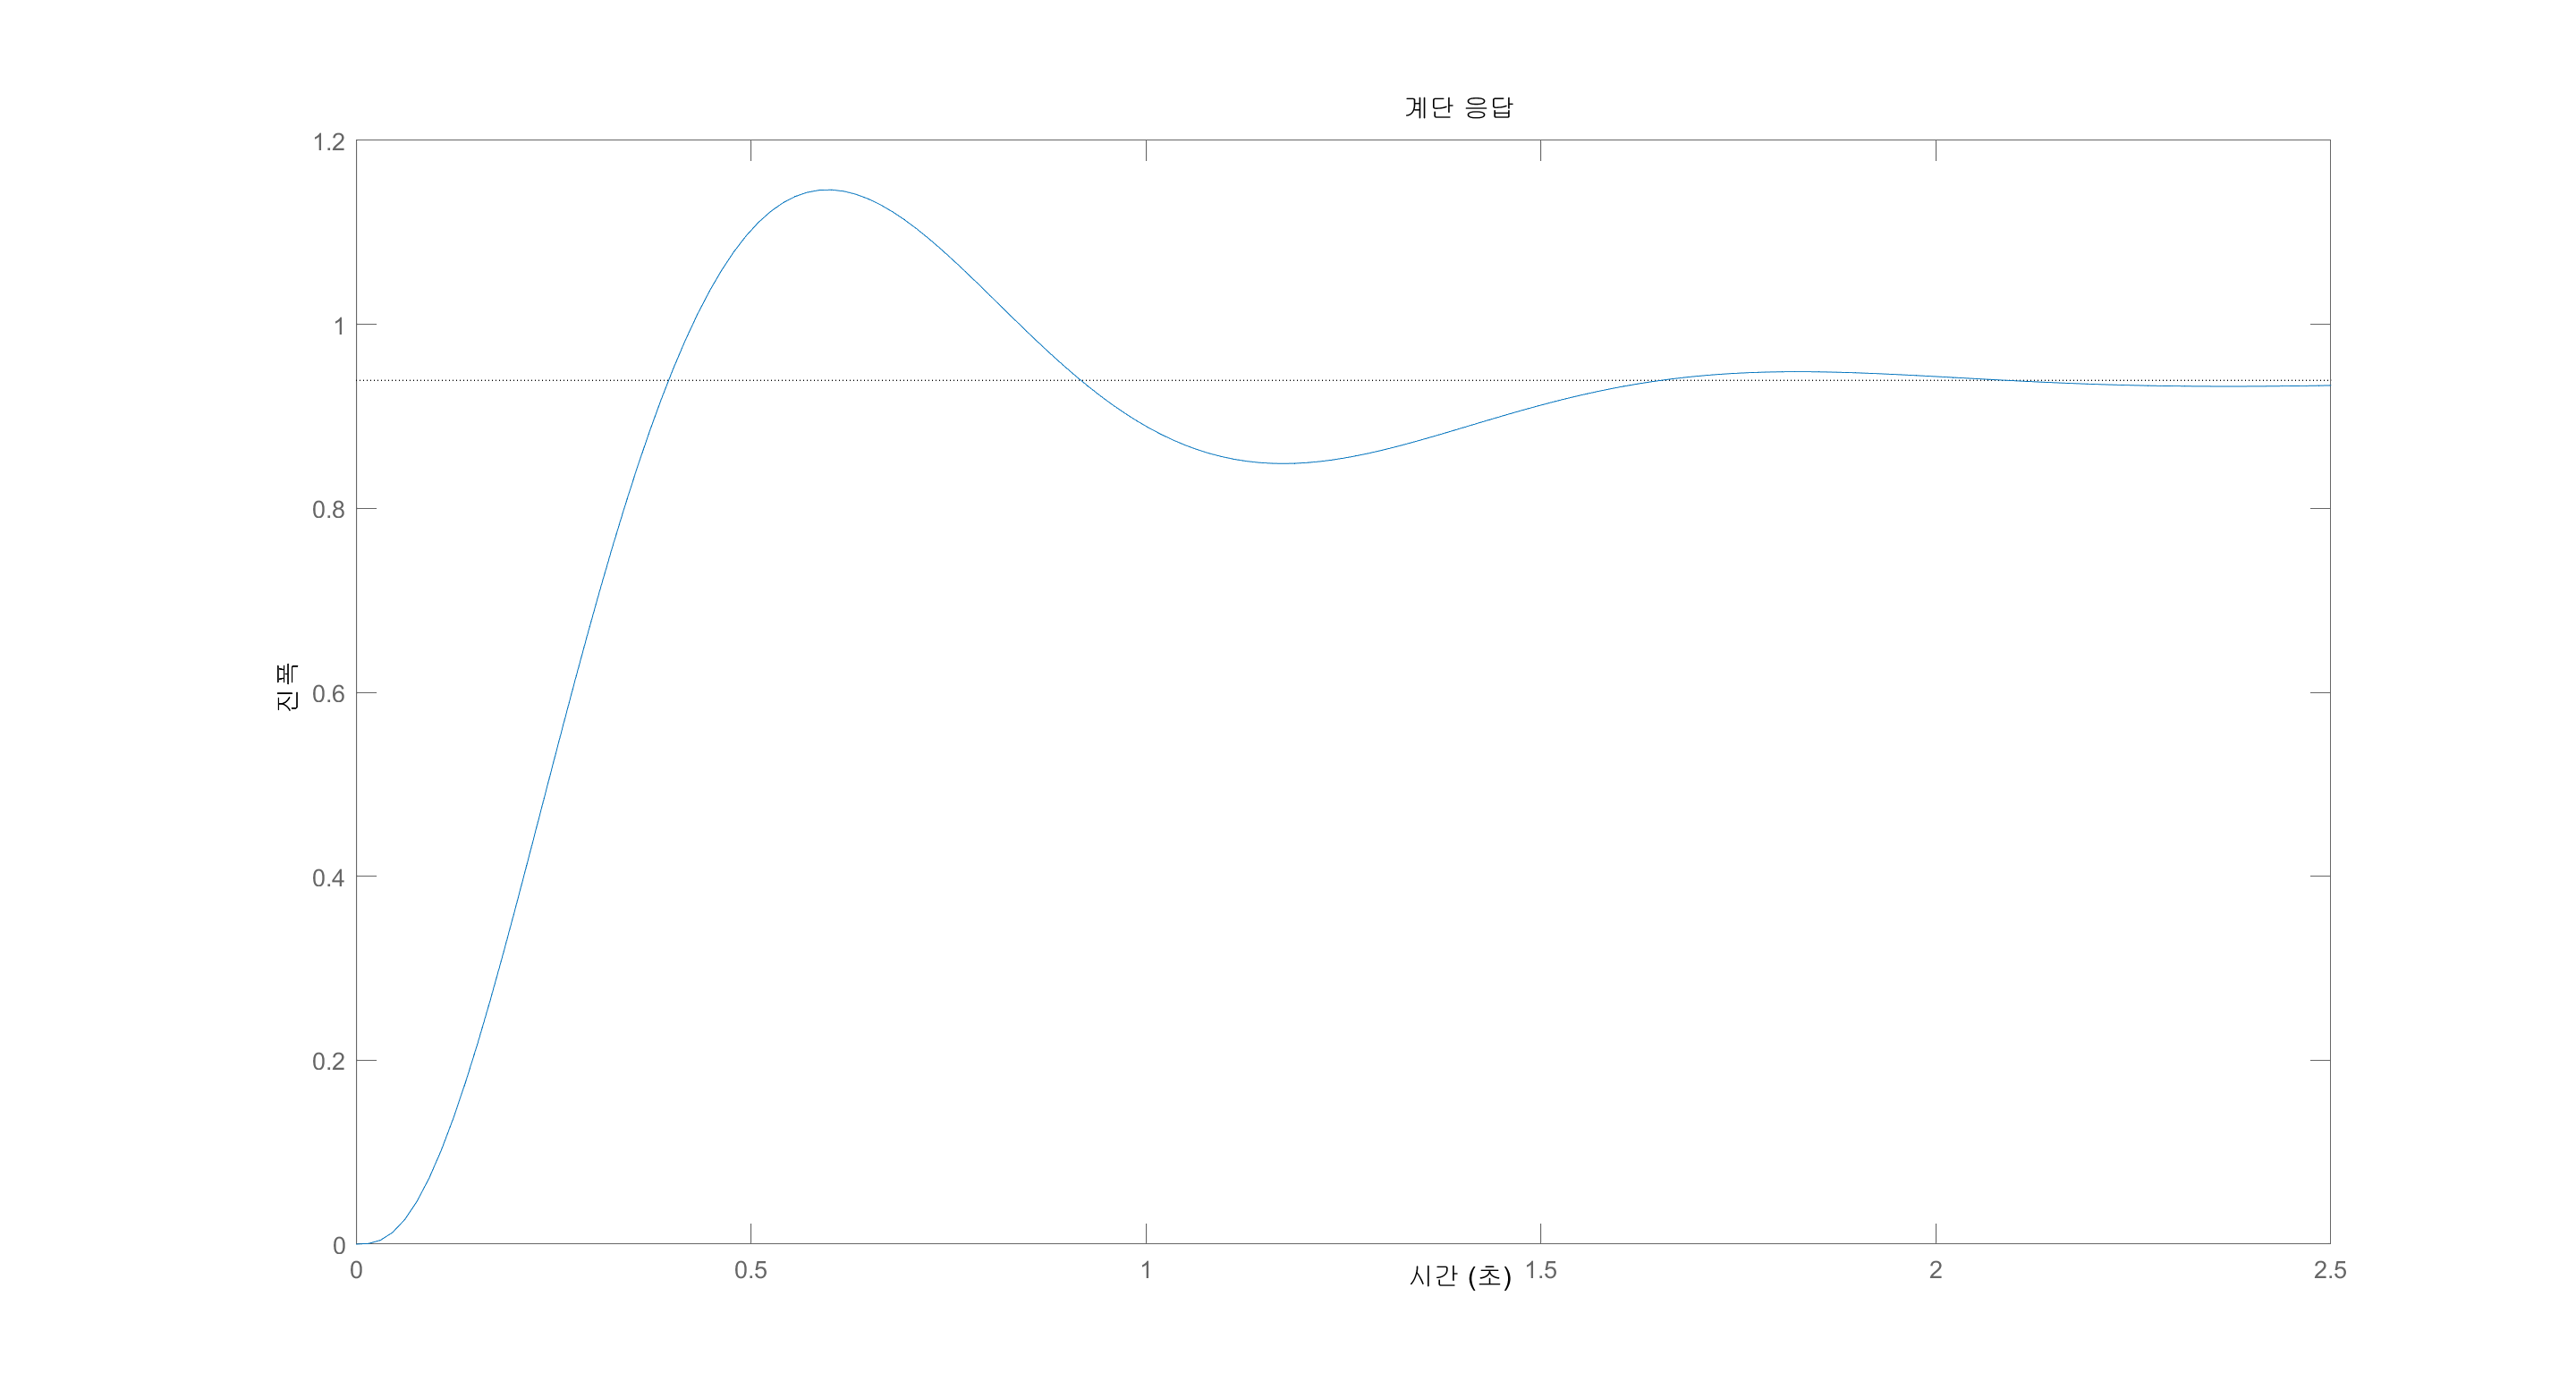

step(T); % Plot step response of

stepinfo(T)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.2526
    TransientTime: 1.5371
     SettlingTime: 1.5371
      SettlingMin: 0.8486
      SettlingMax: 1.1463
        Overshoot: 22.0657
       Undershoot: 0
             Peak: 1.1463
         PeakTime: 0.6019


# [Problem 2] Design the Notch filer

### (a) find the value of plant's gain Kp. dampling ratio is 0.144

numg=[1 10]; % Generate numerator of G(s).
deng=[1 15 444.49 2719.43]; % Generate denominator of G(s).
G=tf(numg,deng) % Create and display G(s).

G =
 
             s + 10
  -----------------------------
  s^3 + 15 s^2 + 444.5 s + 2719
 
연속시간 전달 함수입니다.



s = tf('s');

z=0.144

z = 0.1440

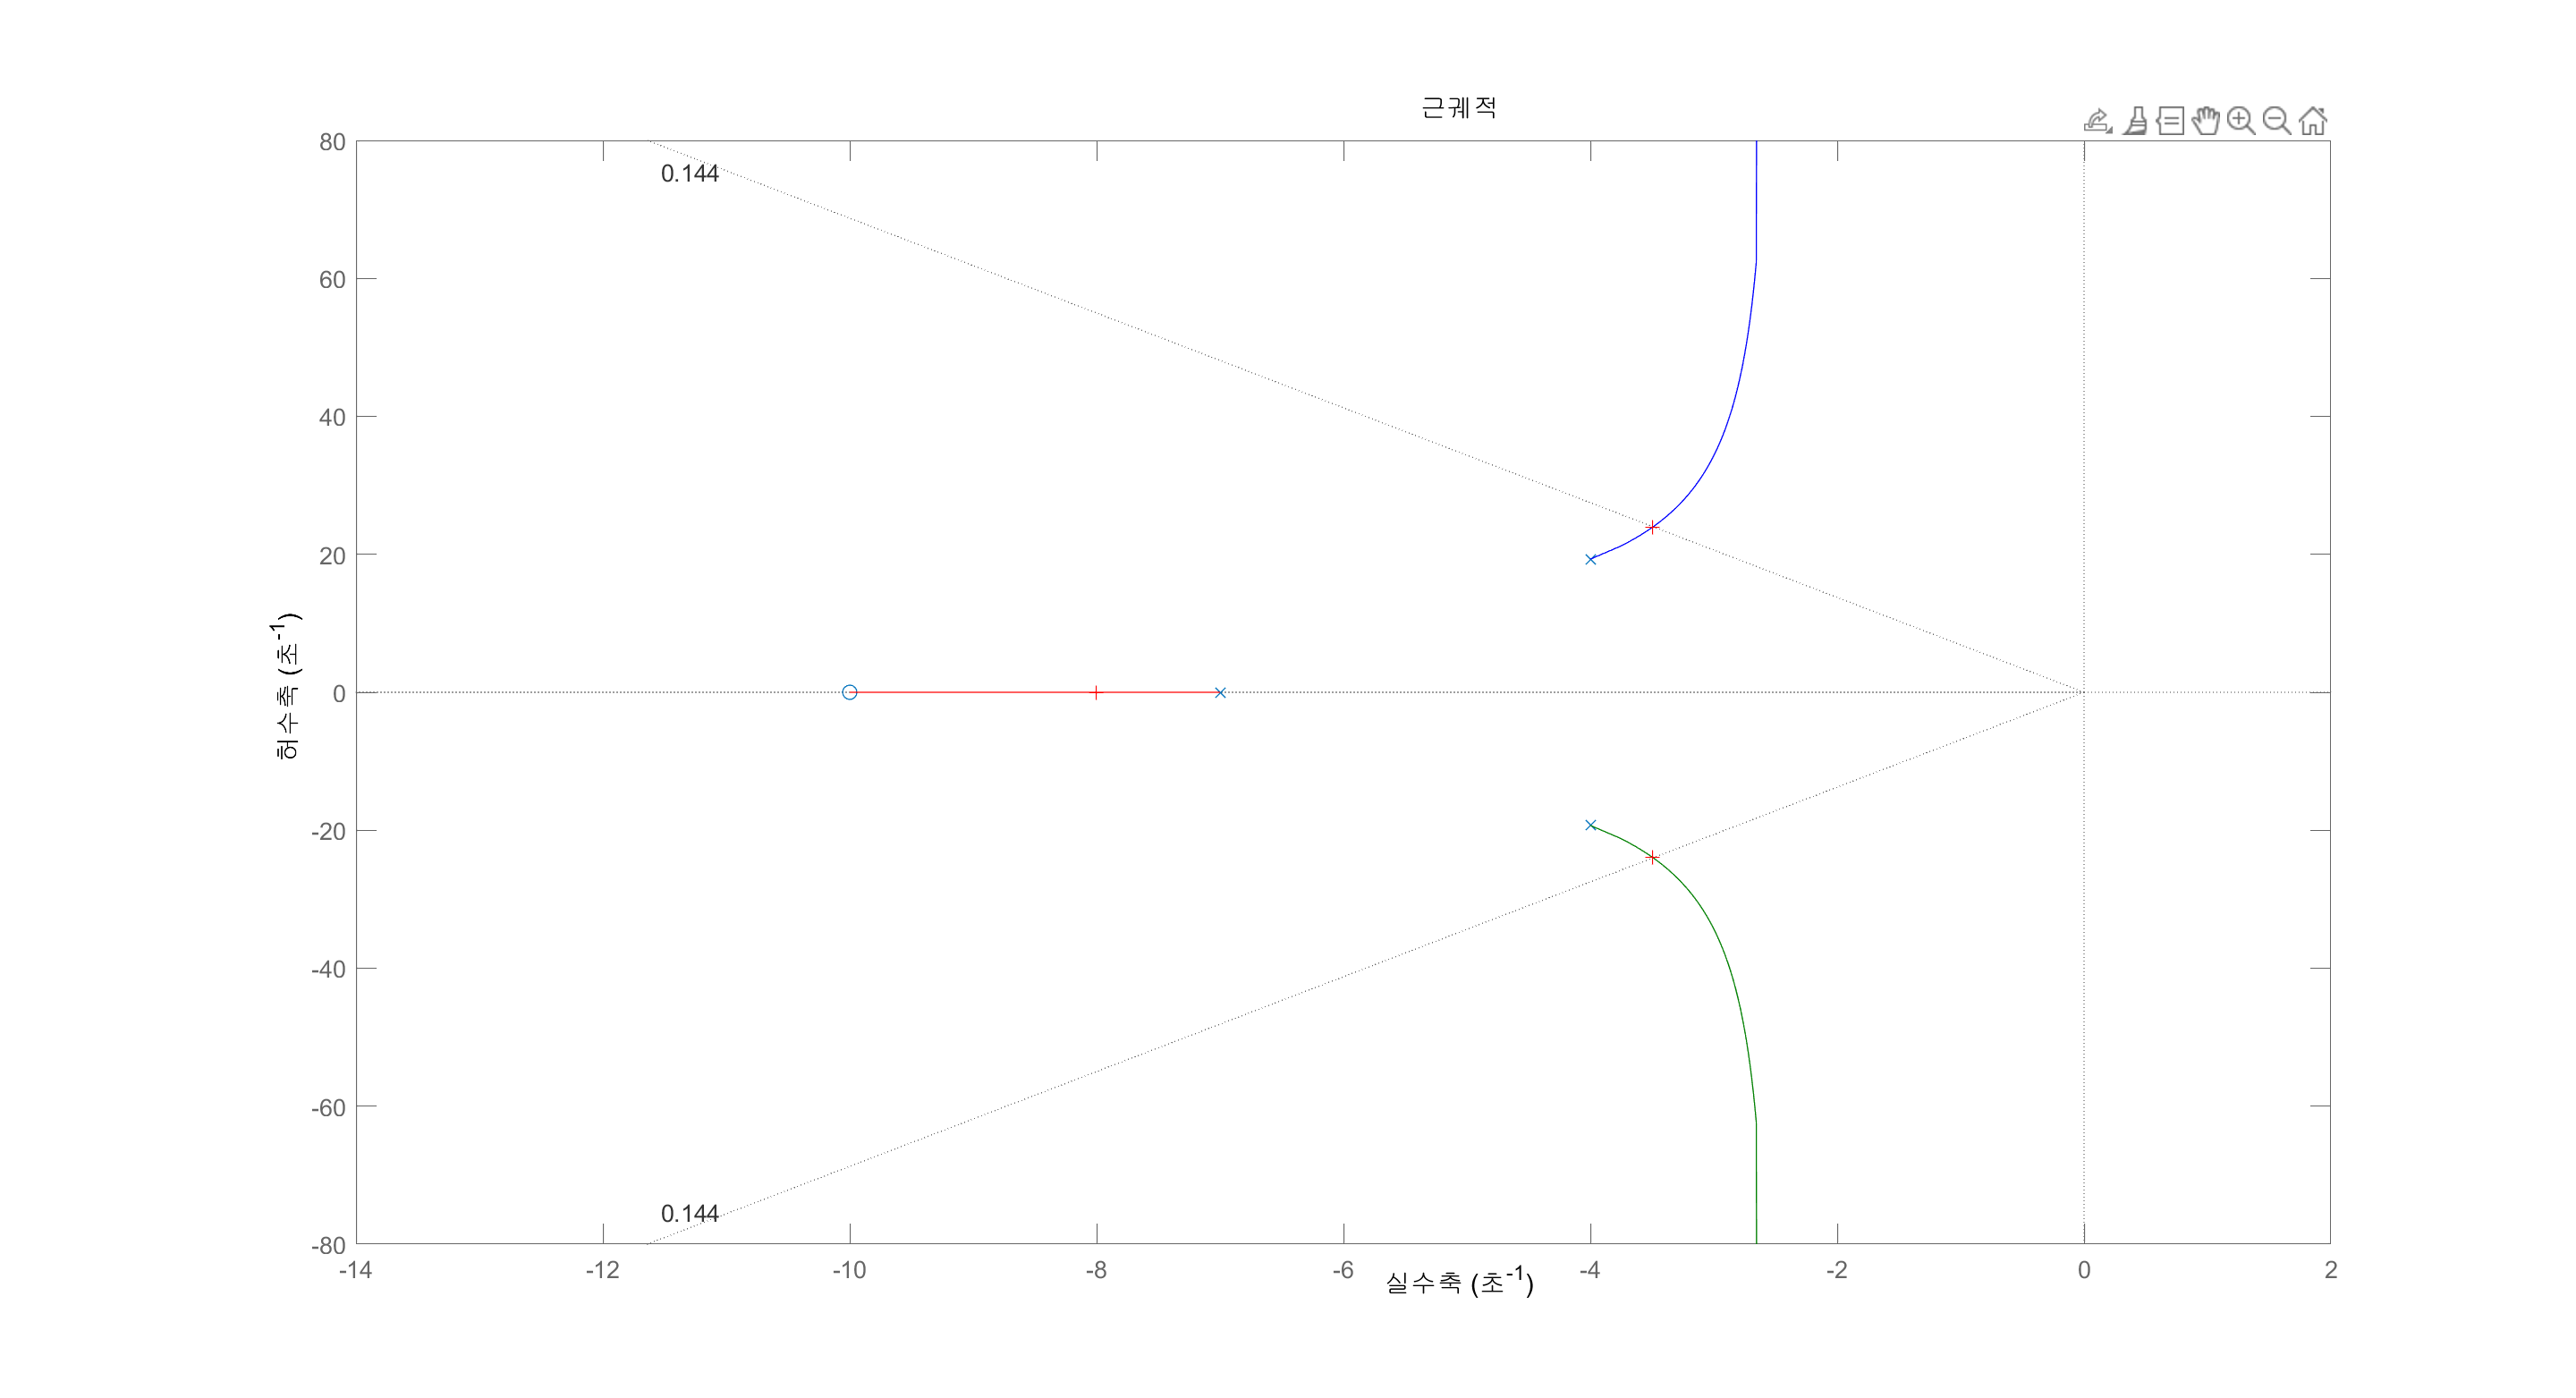

Select a point in the graphics window


selected_point = -3.4746 + 23.9222i

K = 196.0905

p =   -3.4969 +23.9240i
  -3.4969 -23.9240i
  -8.0062 + 0.0000i


rlocus(G) % Plot uncompensated root locus.
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(G) 

p; % Display closed-loop poles.'

Kp = 200

Kp = 200

complex f;
f = -3.49 + 24i

f = -3.4900 + 24.0000i

estimated_natural_frequency=sqrt(real(f)^2+imag(f)^2)

estimated_natural_frequency = 24.2524

estimated_damping_ratio = -real(f)/(estimated_natural_frequency)

estimated_damping_ratio = 0.1439


estimated_dominant_pole_real = estimated_damping_ratio*estimated_natural_frequency

estimated_dominant_pole_real = 3.4900

estimated_dominant_pole_img = estimated_natural_frequency*sqrt(1-estimated_damping_ratio^2)

estimated_dominant_pole_img = 24



Err_constant = dcgain(Kp*G)

Err_constant = 0.7354

ess = 1/(1+Err_constant)

ess = 0.5762

T=feedback(Kp*G,1) % Find uncompensated T(s).

T =
 
          200 s + 2000
  -----------------------------
  s^3 + 15 s^2 + 644.5 s + 4719
 
연속시간 전달 함수입니다.



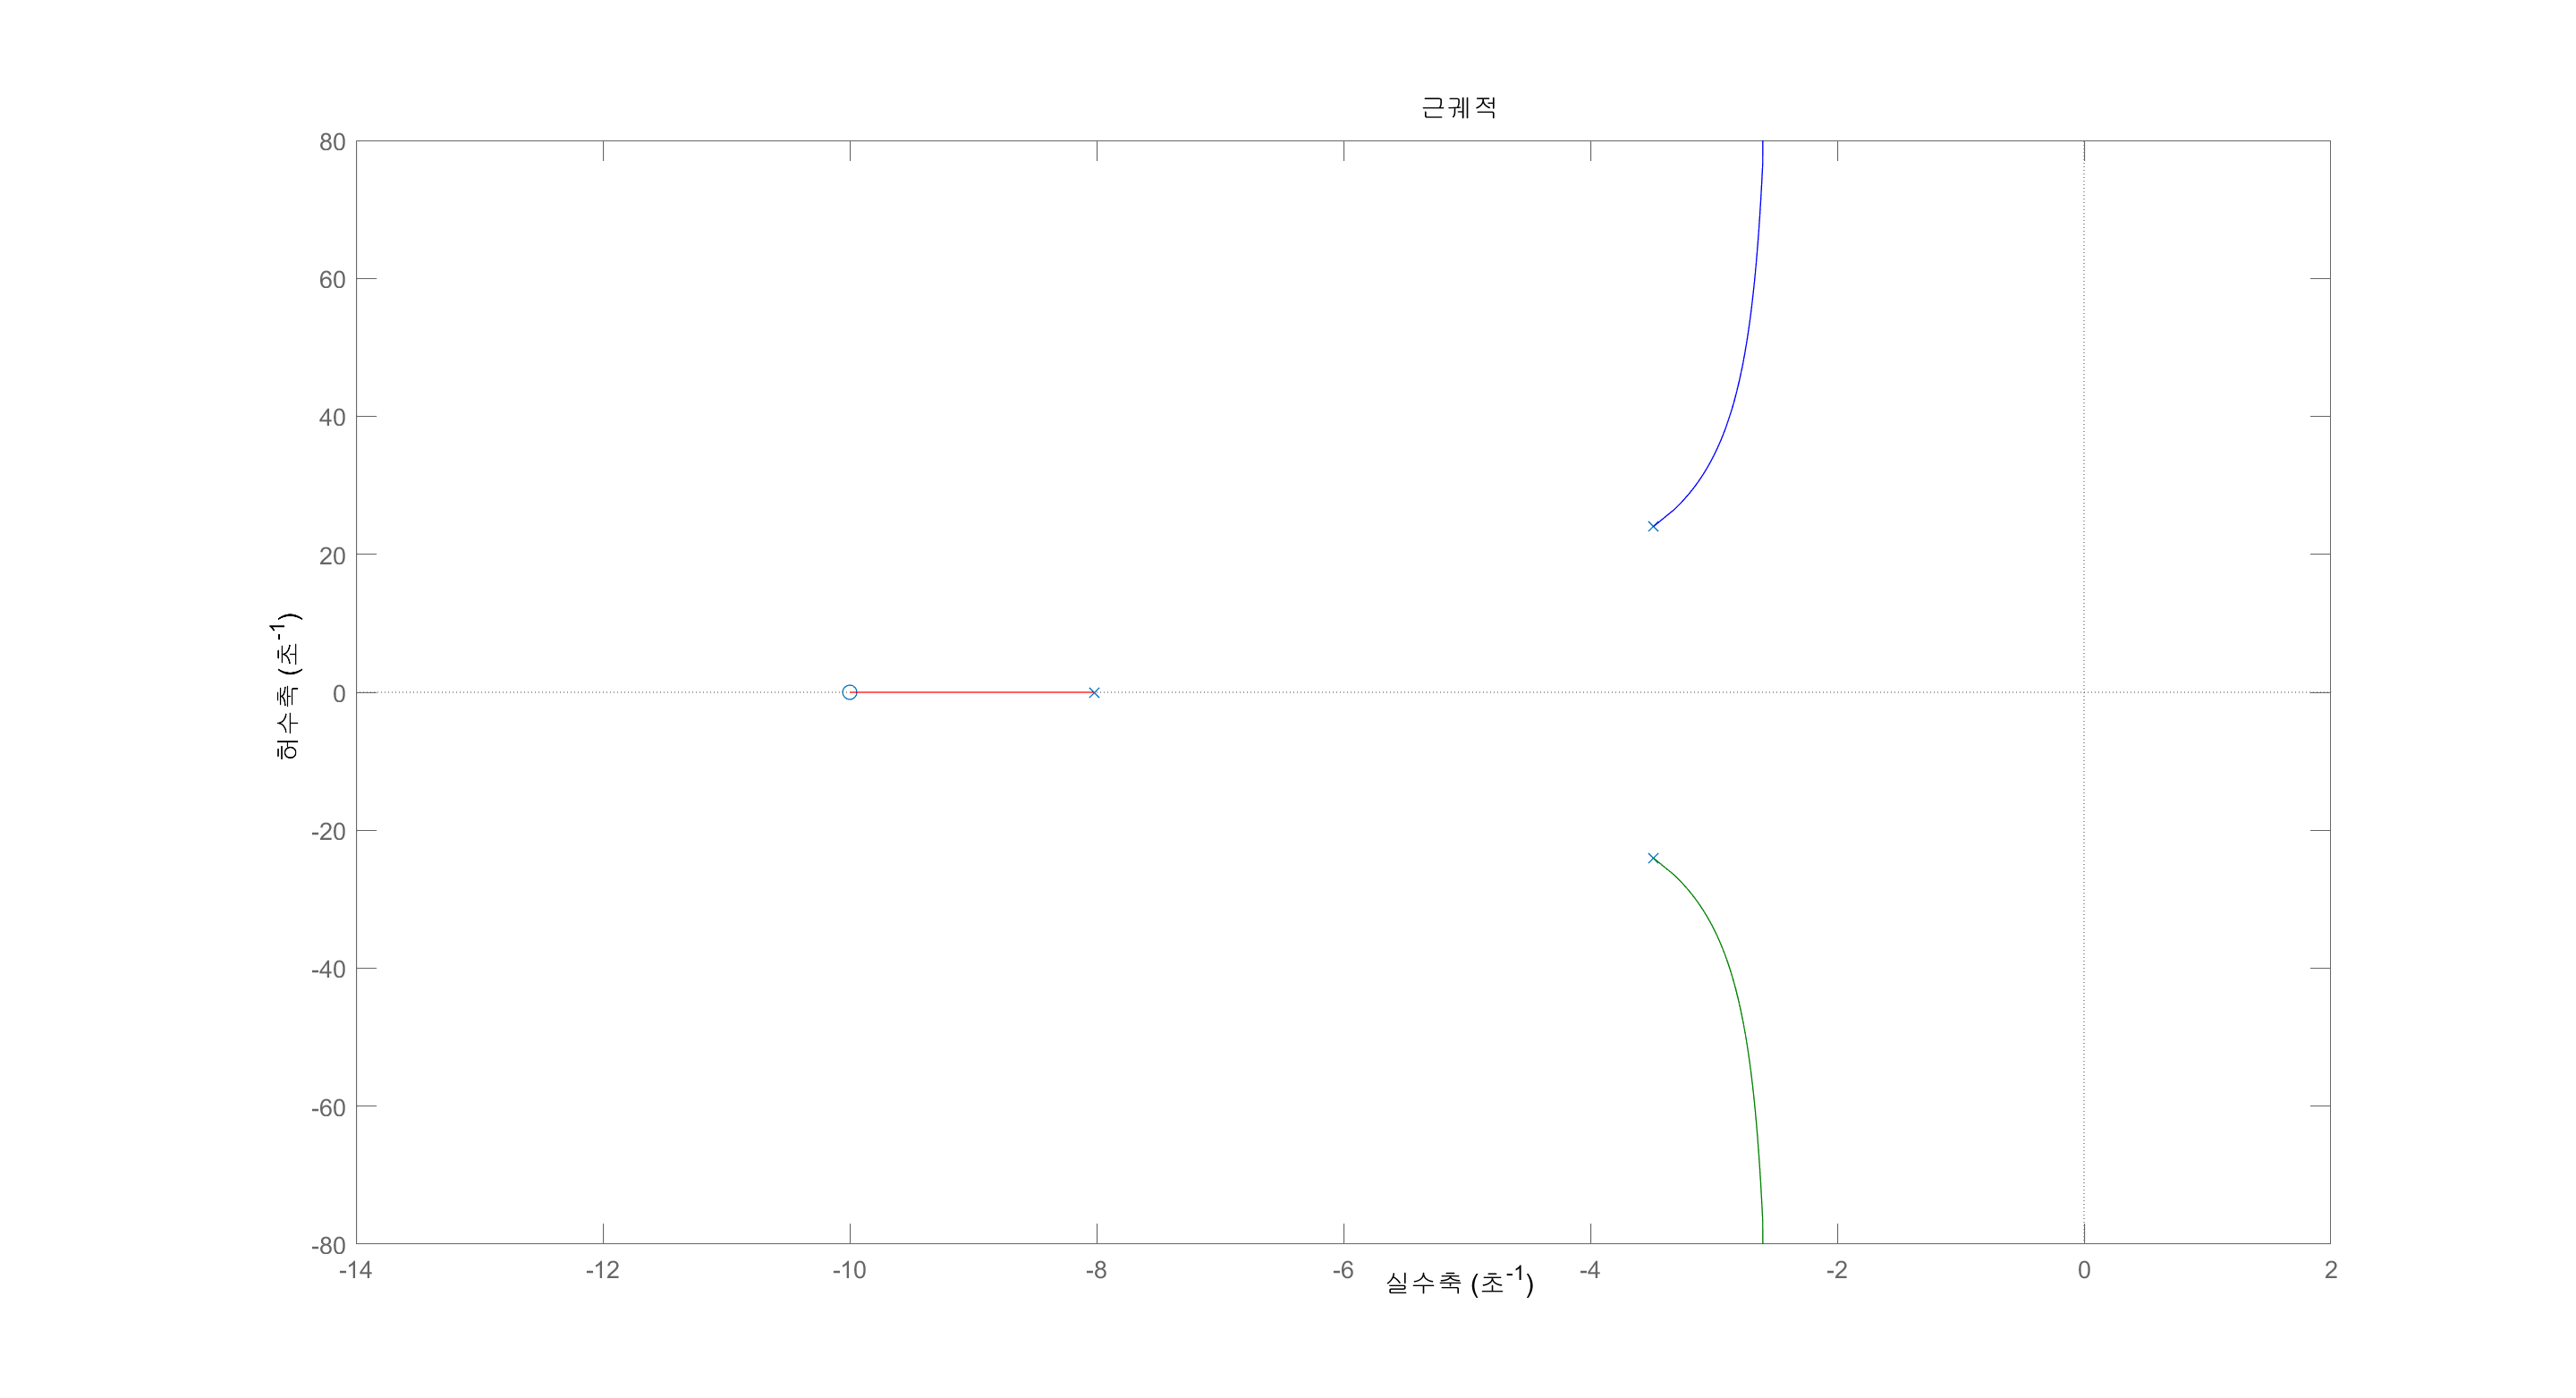

rlocus(T)

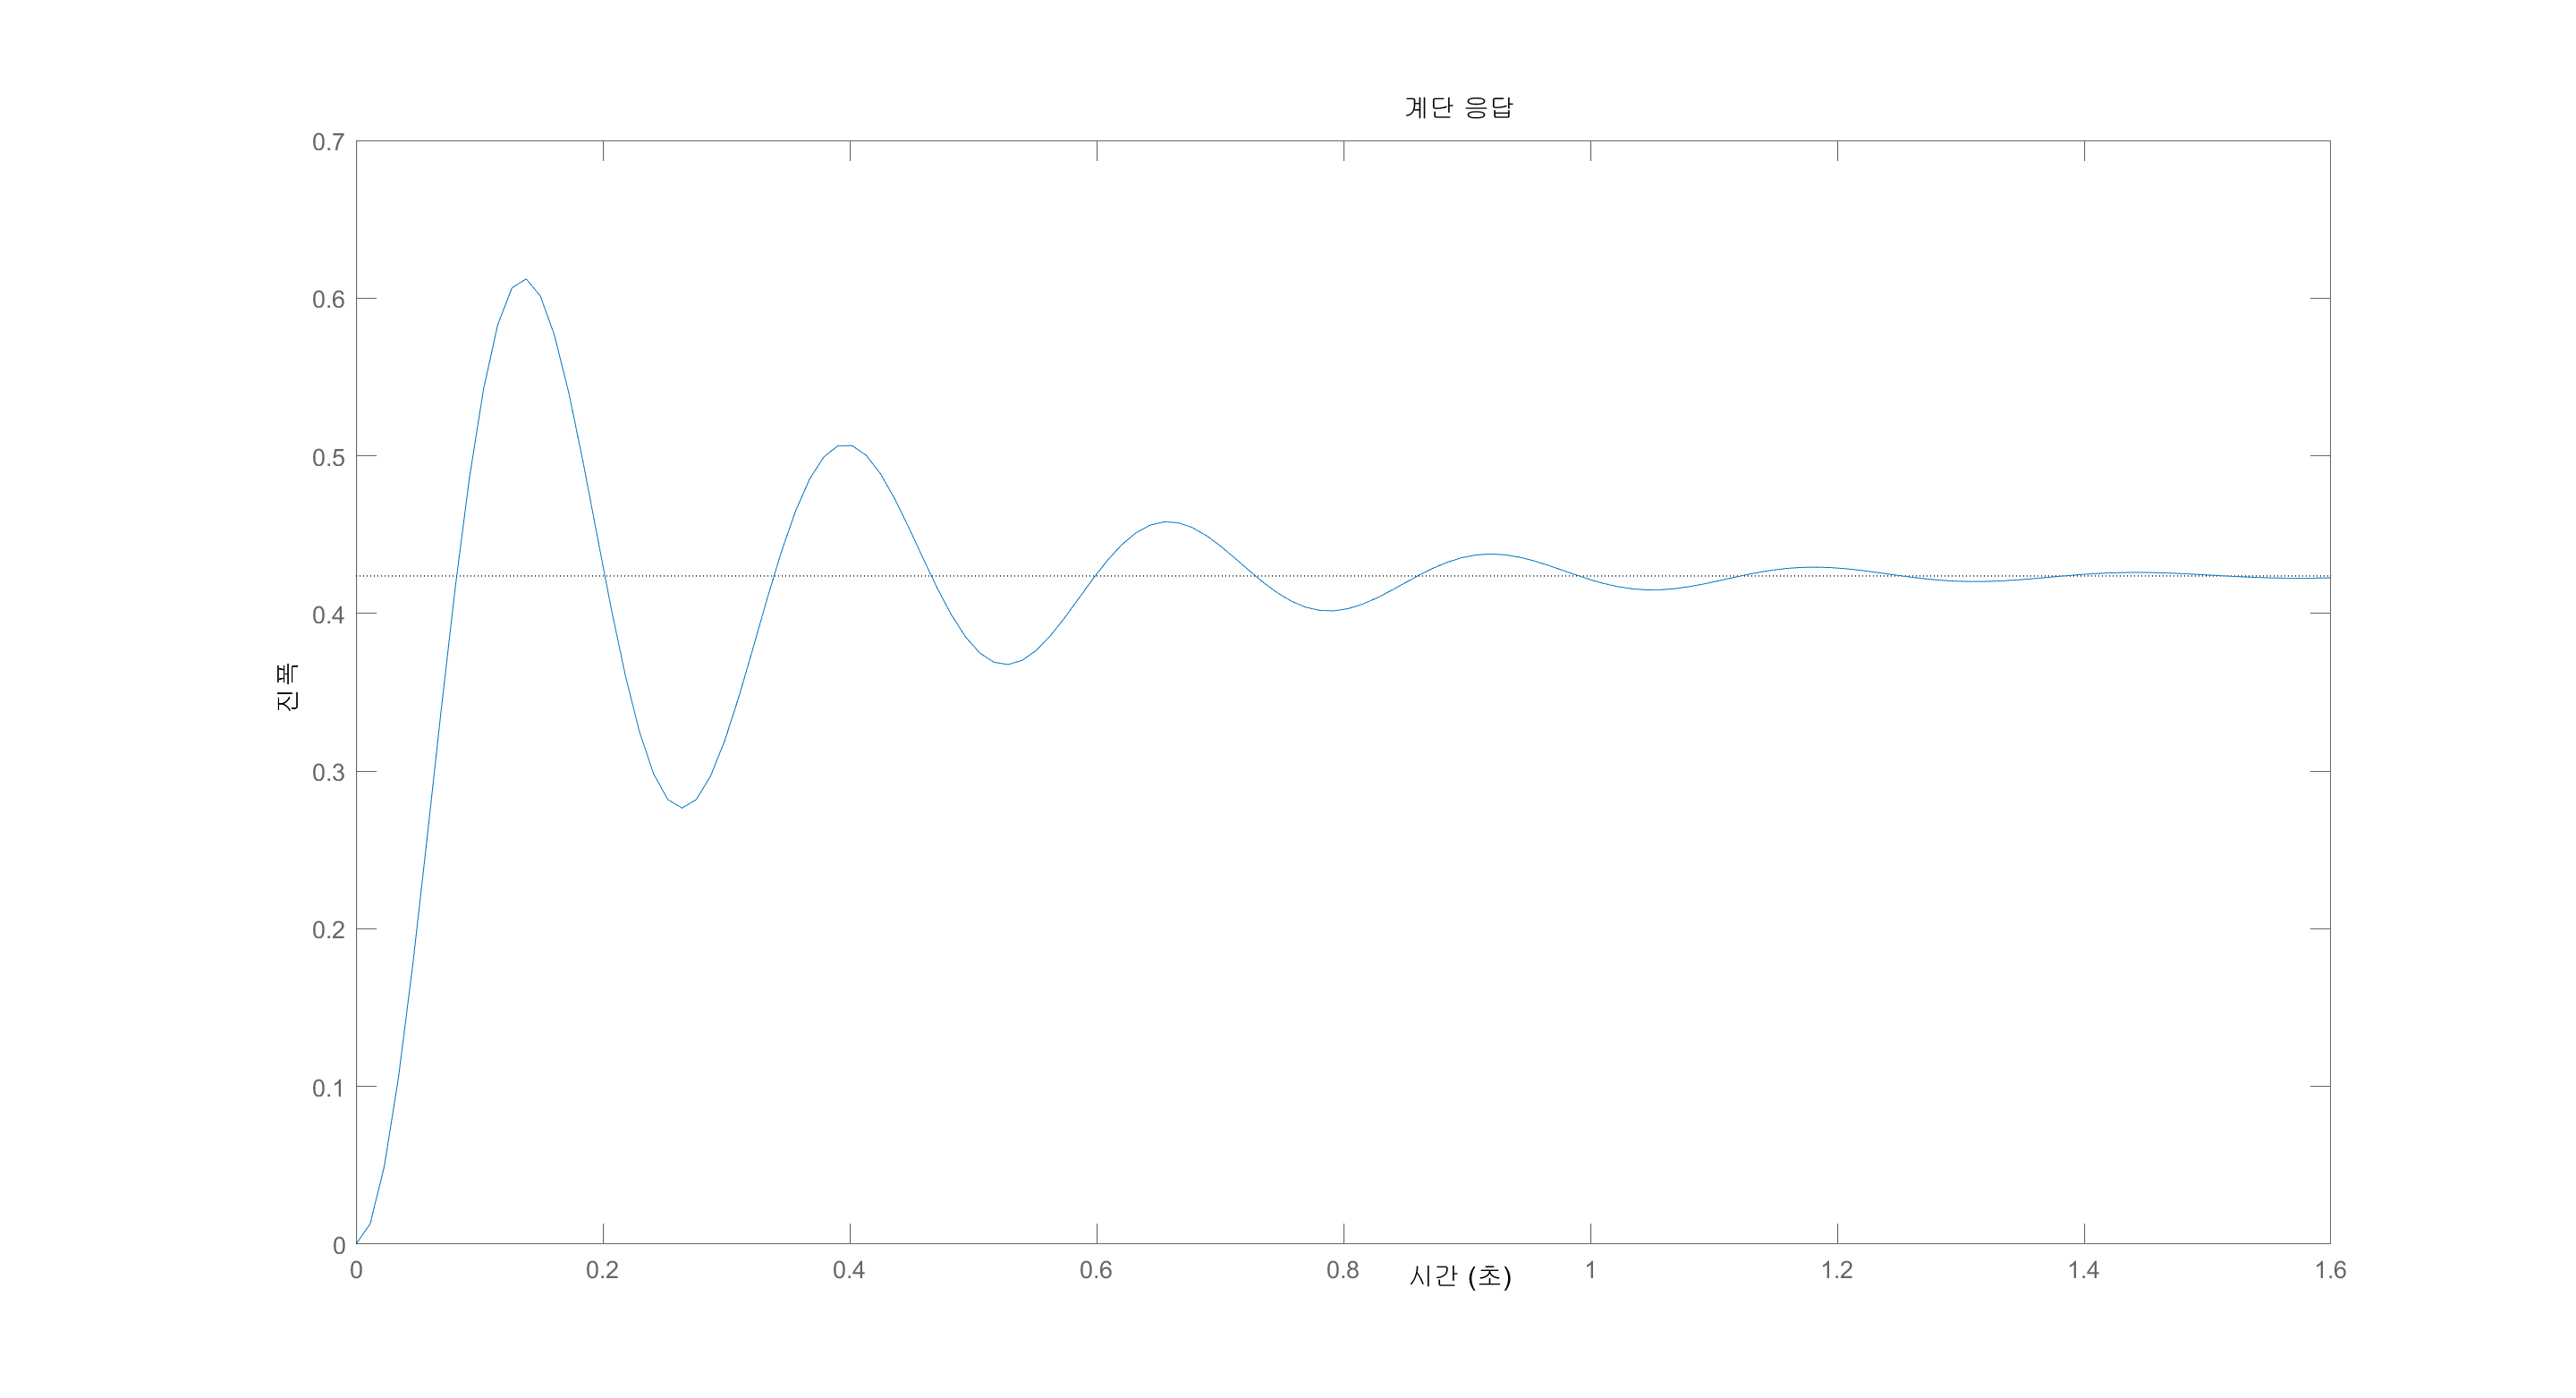

step(T); % Plot step response of

stepinfo(T)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.0545
    TransientTime: 1.0615
     SettlingTime: 1.0615
      SettlingMin: 0.2766
      SettlingMax: 0.6122
        Overshoot: 44.4543
       Undershoot: 0
             Peak: 0.6122
         PeakTime: 0.1378


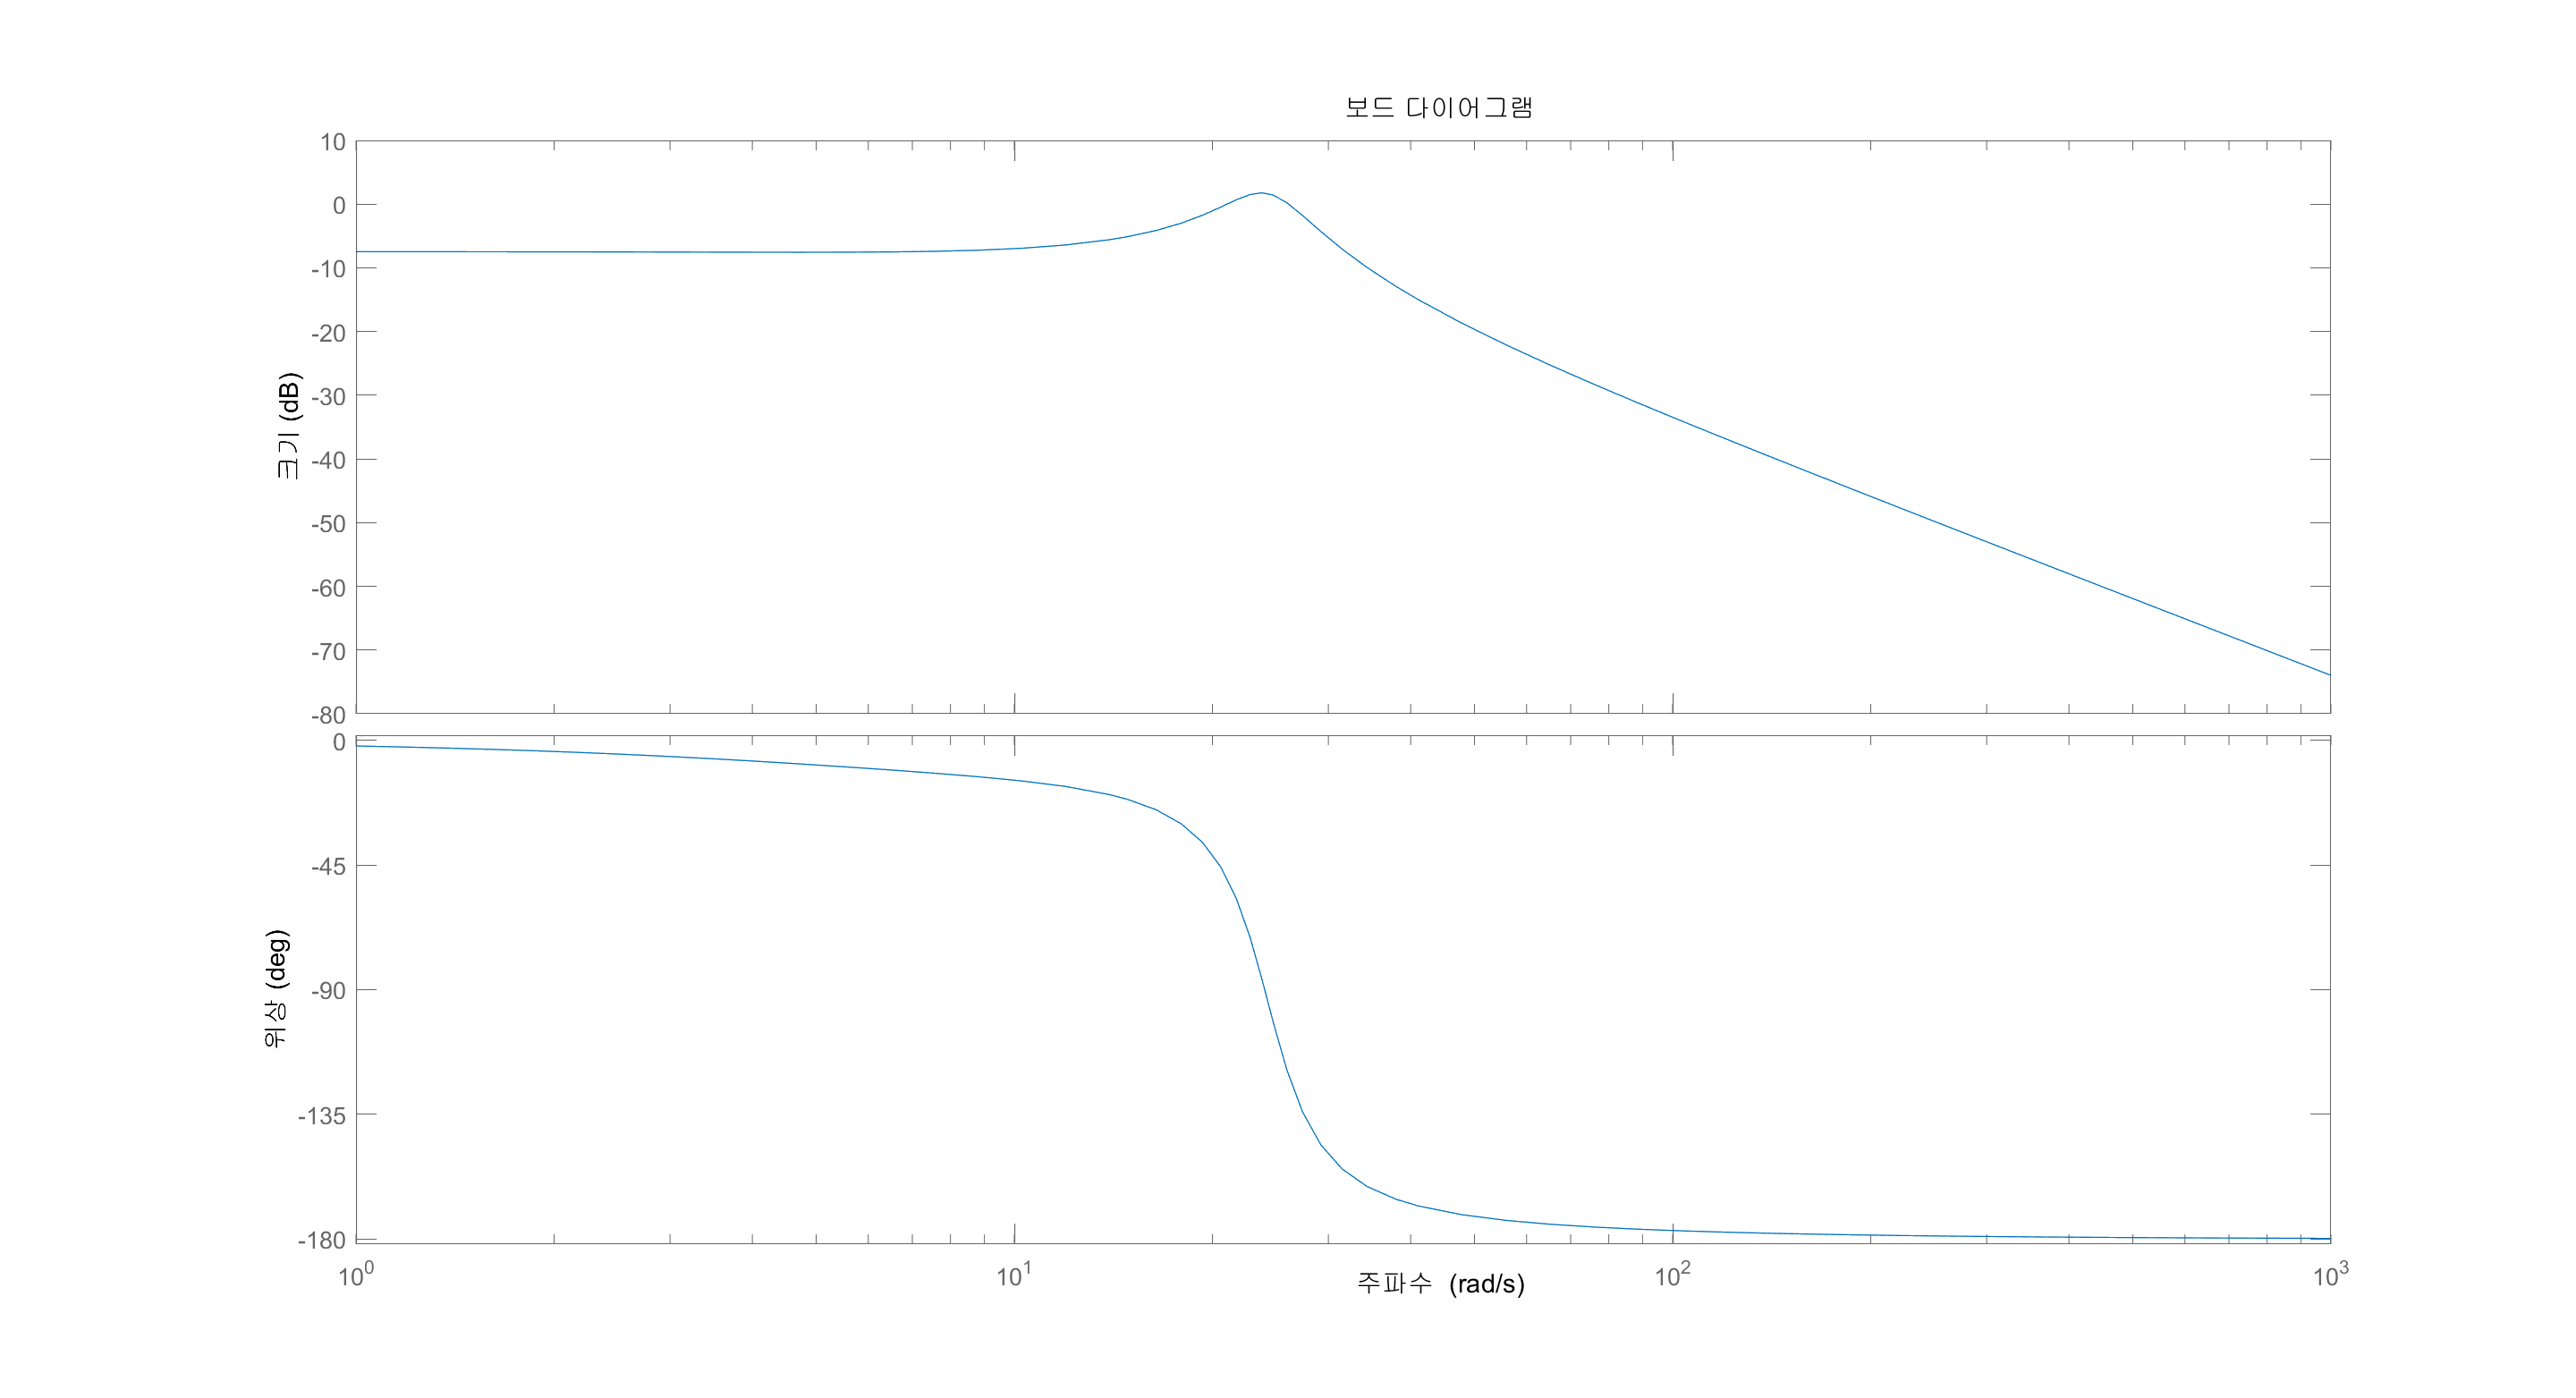


bode(T)

#### 2- (c)  'Notch Filter'

numg=[1 10]; % Generate numerator of G(s).
deng=[1 15 444.49 2719.43]; % Generate denominator of G(s).
G=tf(numg,deng) % Create and display G(s).

G =
 
             s + 10
  -----------------------------
  s^3 + 15 s^2 + 444.5 s + 2719
 
연속시간 전달 함수입니다.



s = tf('s');

z=0.144

z = 0.1440

Kp = 200

Kp = 200


numn=poly([-5+19i -5-19i]);% Generate numerator of G(s).
denn=poly([-3 -6]); % Generate denominator of G(s).
Gc=tf(numn,denn) % Create and display G(s).

Gc =
 
  s^2 + 10 s + 386
  ----------------
   s^2 + 9 s + 18
 
연속시간 전달 함수입니다.



%rlocus(Gc)
%bode(Gc)
Gn = G*Gc

Gn =
 
                  s^3 + 20 s^2 + 486 s + 3860
  -----------------------------------------------------------
  s^5 + 24 s^4 + 597.5 s^3 + 6990 s^2 + 3.248e04 s + 4.895e04
 
연속시간 전달 함수입니다.



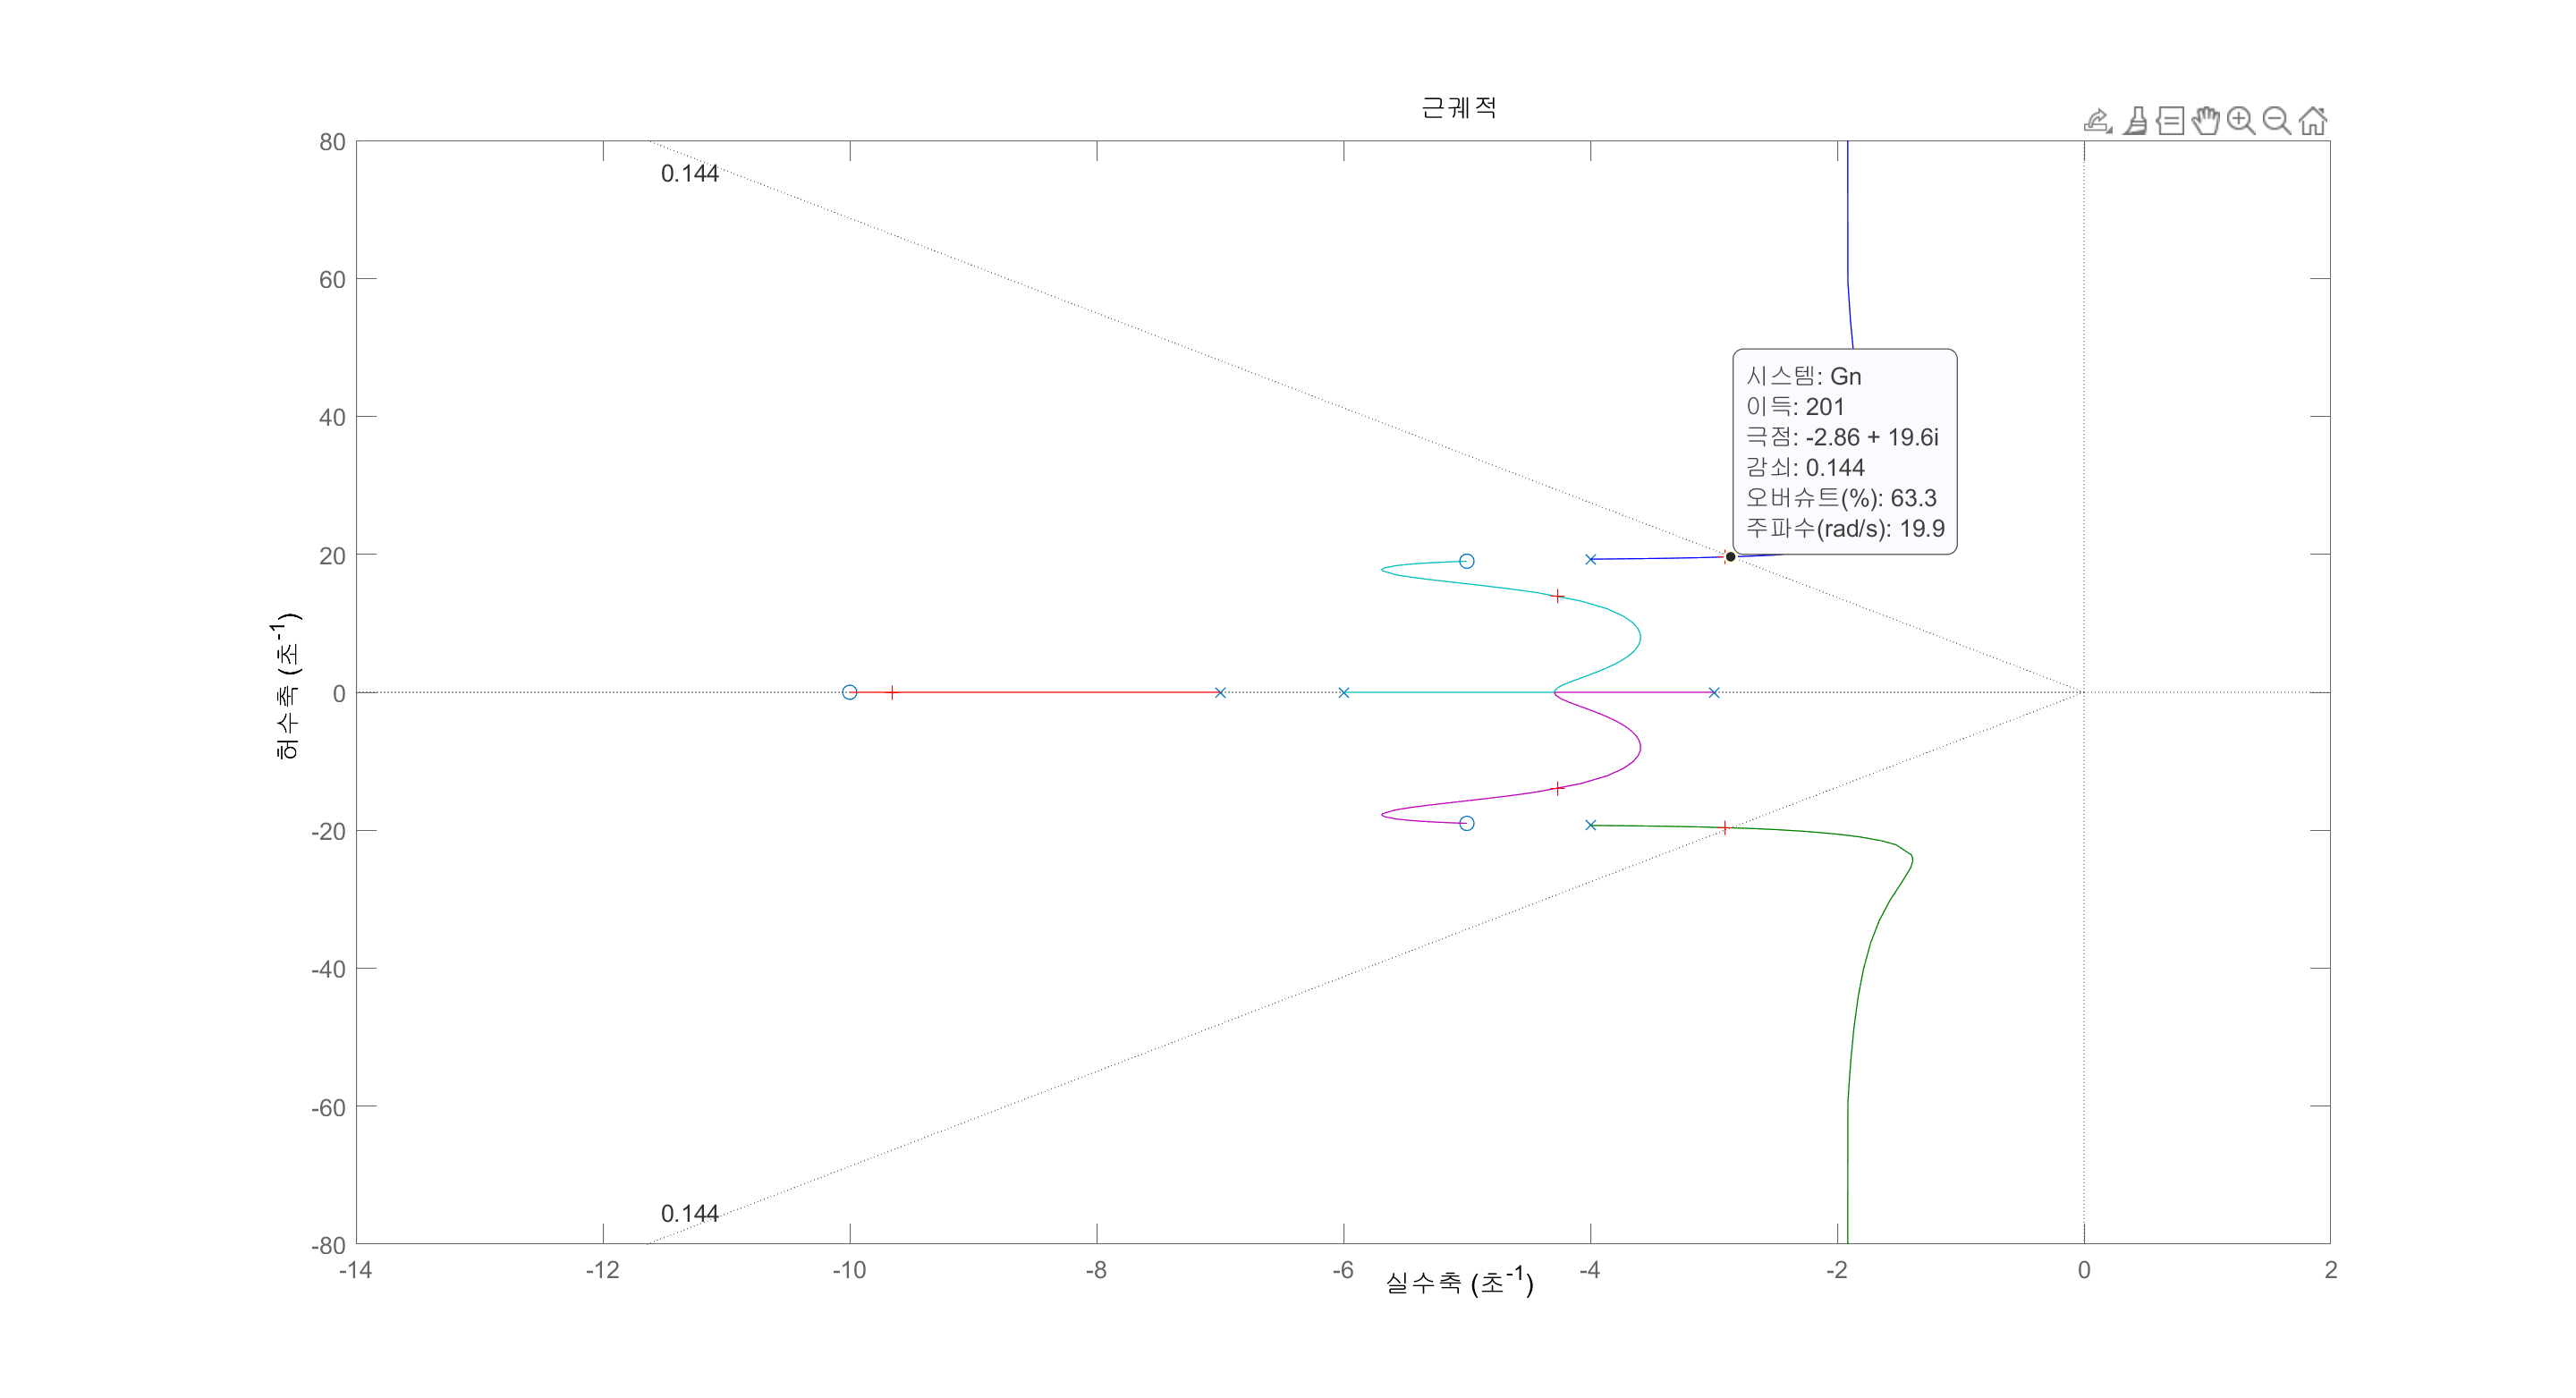

Select a point in the graphics window


selected_point = -2.8659 + 19.5138i

K = 195.9665

p =   -2.9103 +19.6108i
  -2.9103 -19.6108i
  -4.2635 +13.9322i
  -4.2635 -13.9322i
  -9.6524 + 0.0000i



rlocus(Gn) % Plot uncompensated root locus.
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(Gn) 

p; % Display closed-loop poles.'

Err_constant = dcgain(Kp*Gn)

Err_constant = 15.7713

ess = 1/(1+Err_constant)

ess = 0.0596


T1=feedback(Kp*G,1)

T1 =
 
          200 s + 2000
  -----------------------------
  s^3 + 15 s^2 + 644.5 s + 4719
 
연속시간 전달 함수입니다.



T2=feedback(Kp*Gn,1) % Find uncompensated T(s).

T2 =
 
               200 s^3 + 4000 s^2 + 97200 s + 772000
  ---------------------------------------------------------------
  s^5 + 24 s^4 + 797.5 s^3 + 1.099e04 s^2 + 1.297e05 s + 8.209e05
 
연속시간 전달 함수입니다.



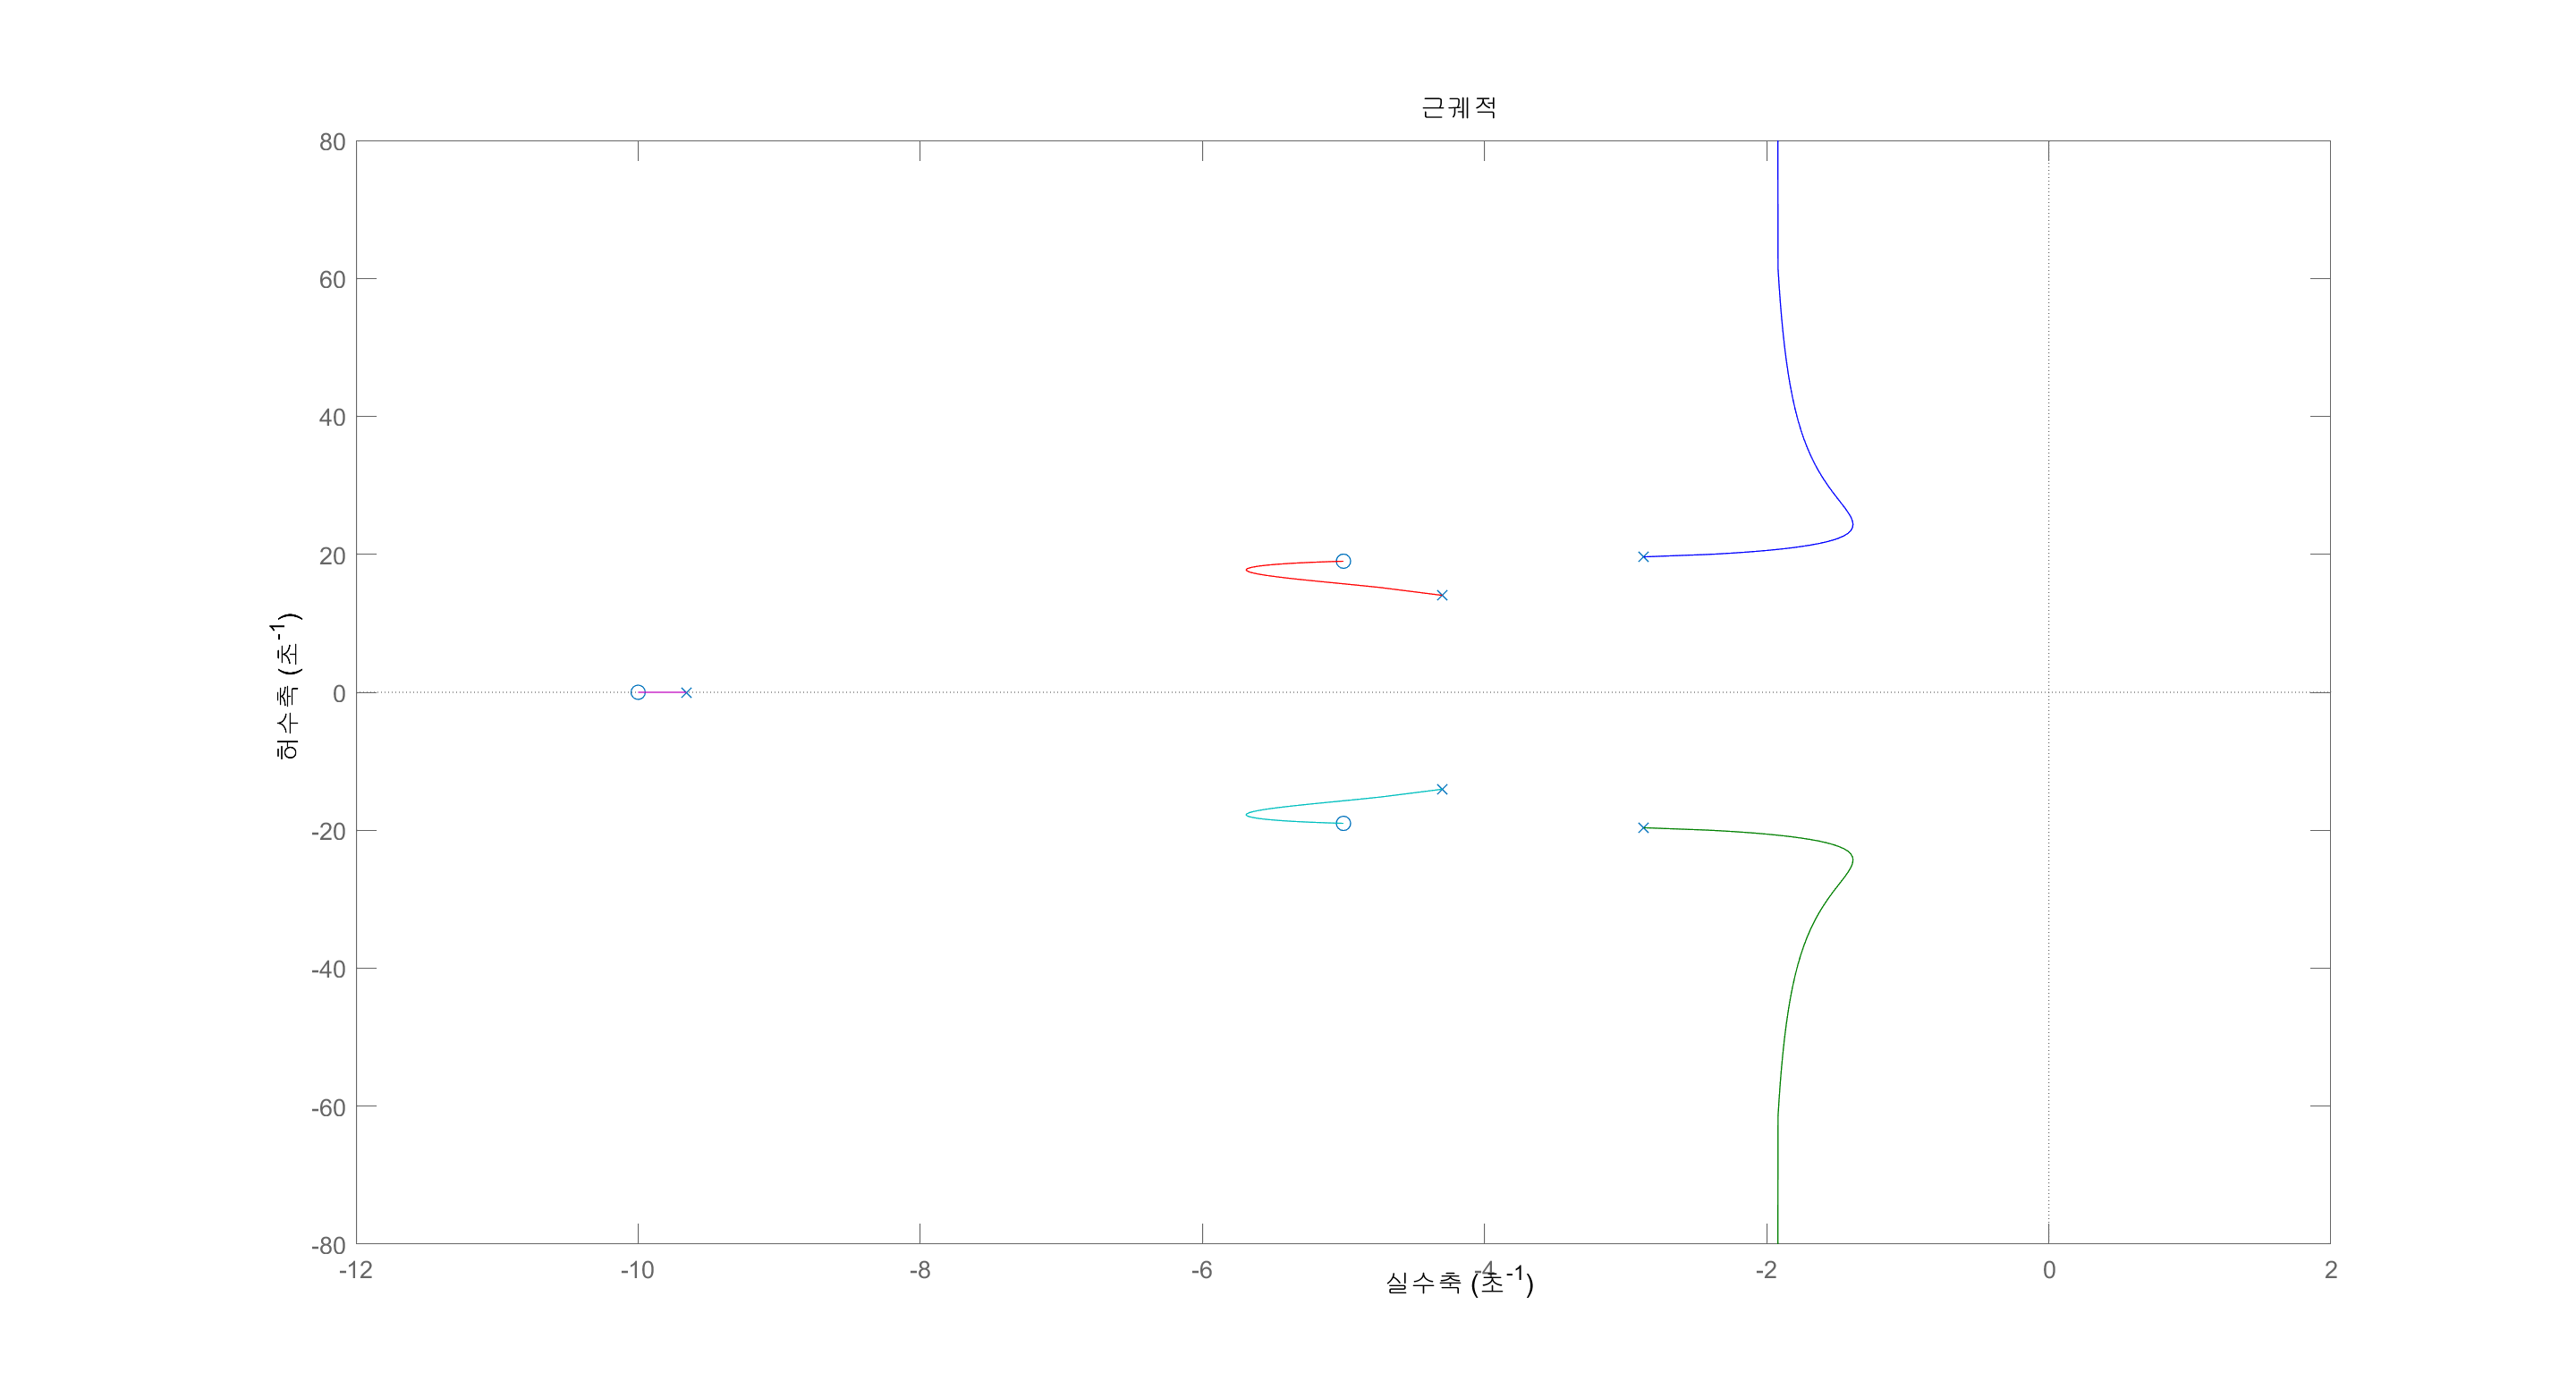

rlocus(T2)

step(T1)

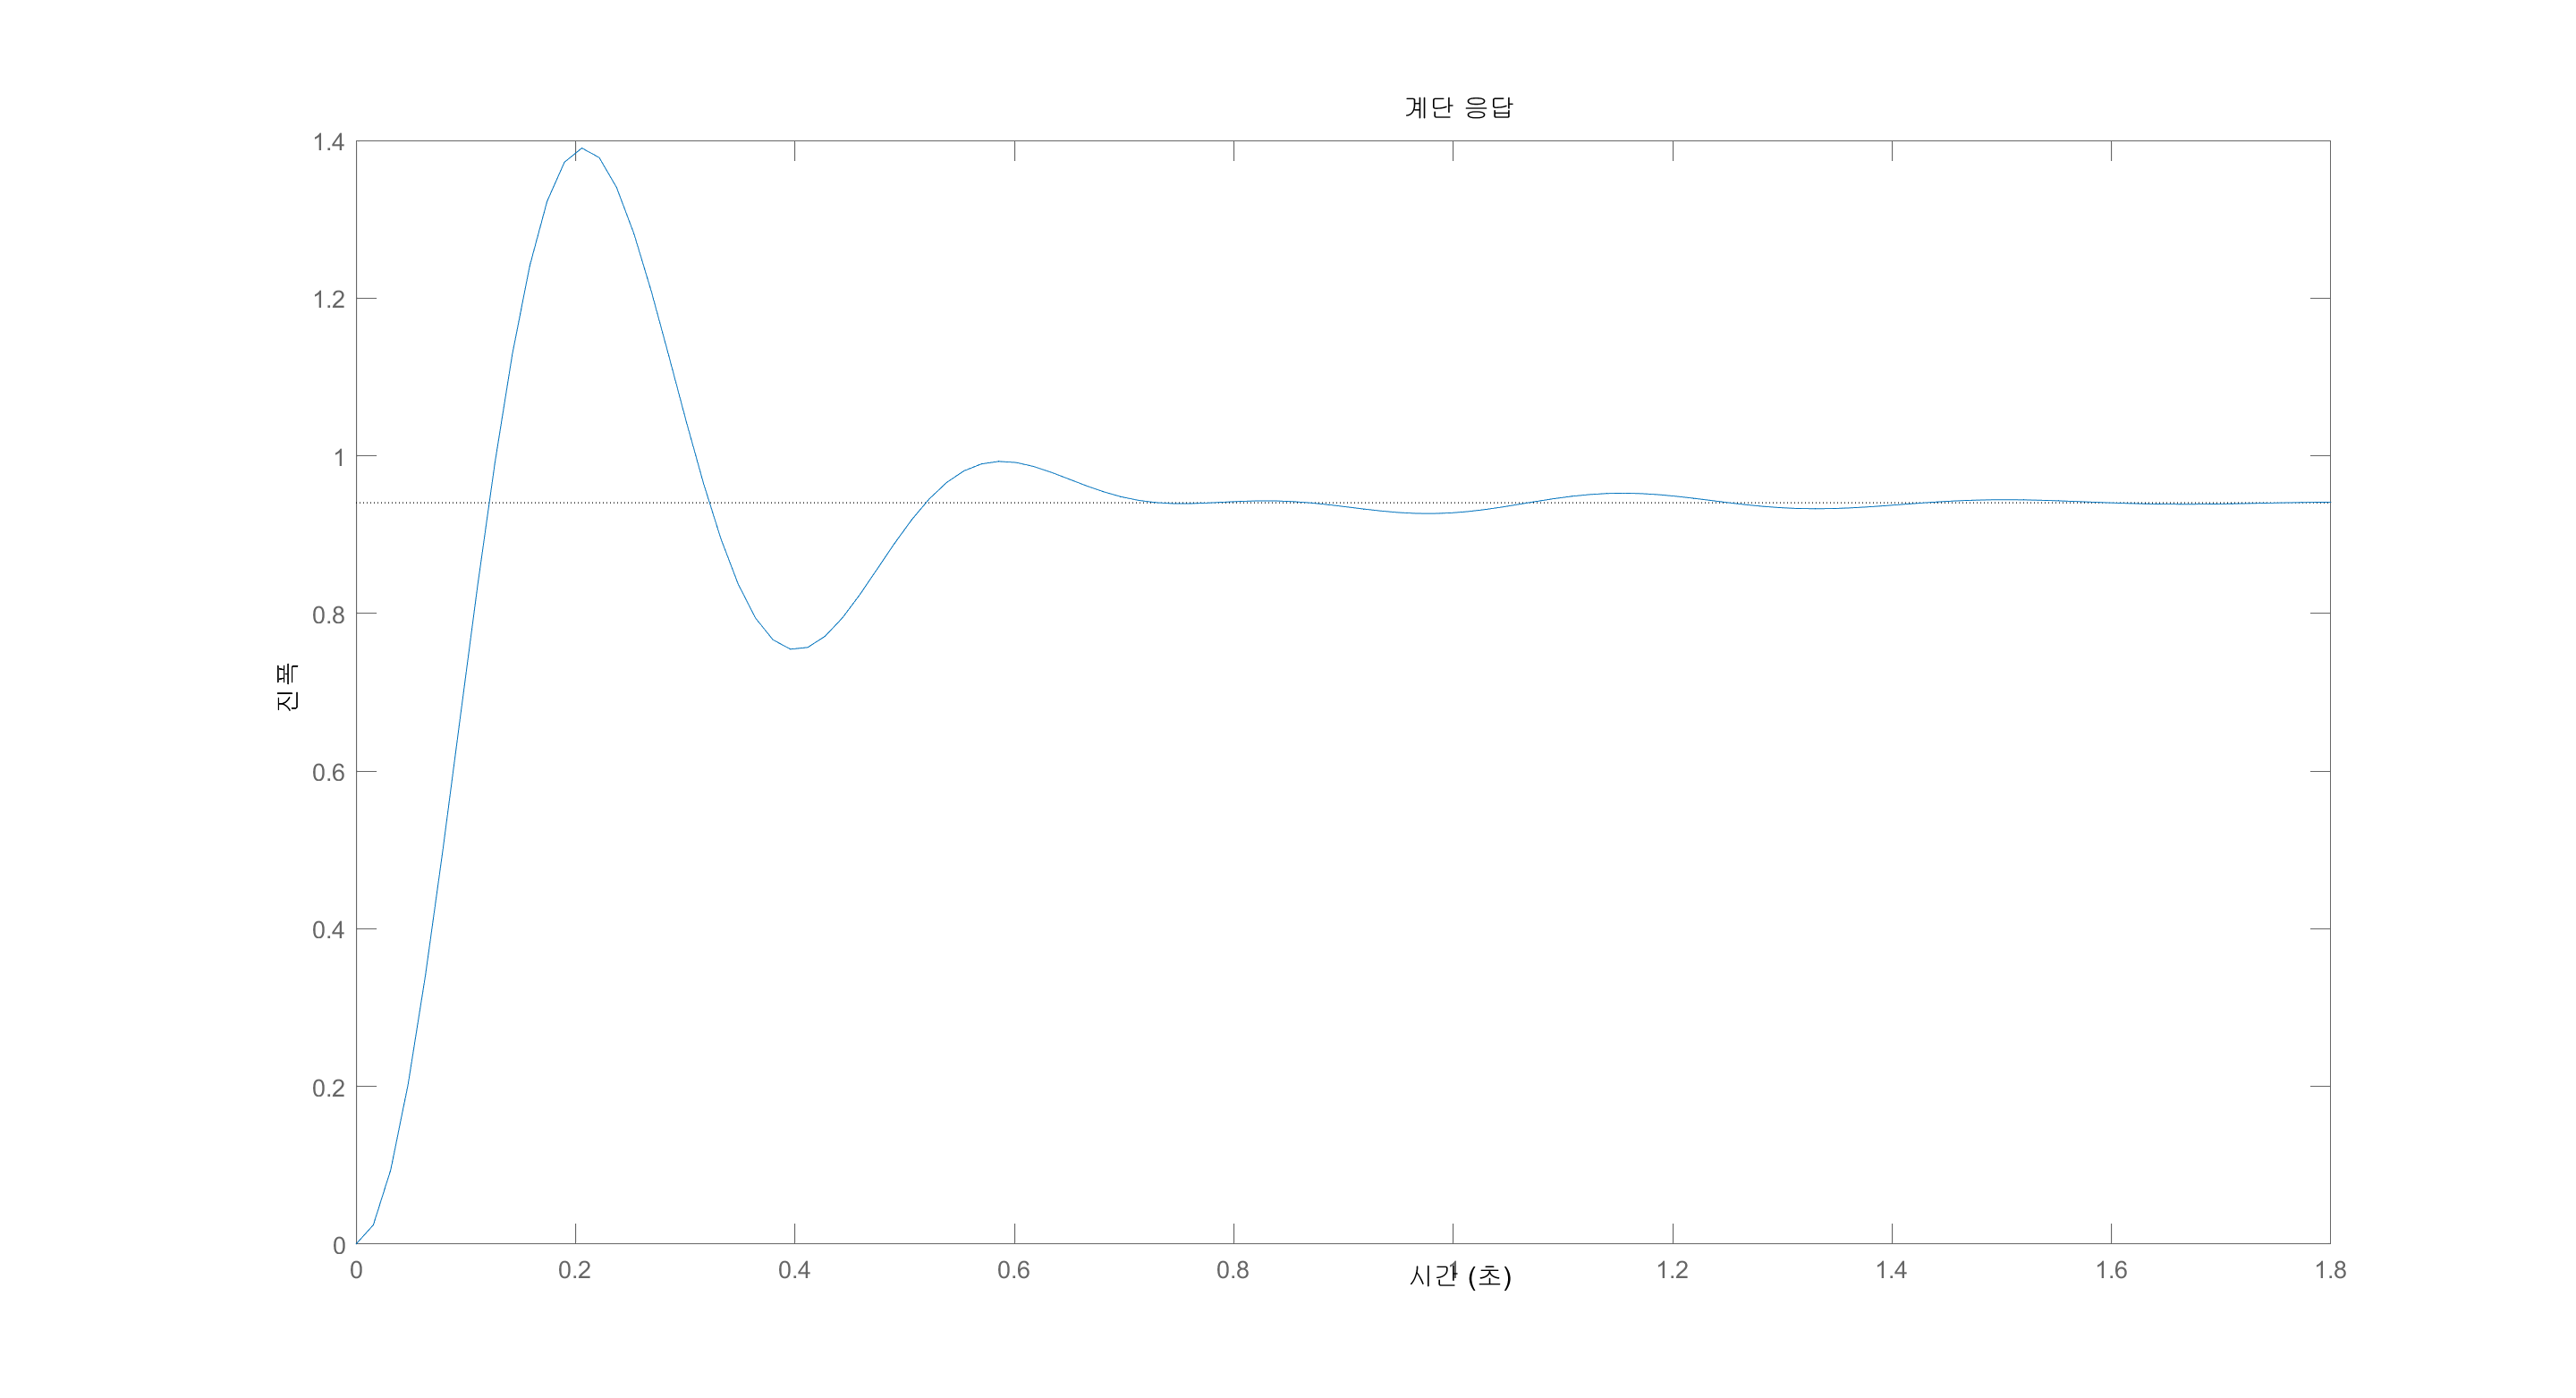

step(T2) % Plot step response of

stepinfo(T2)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.0804
    TransientTime: 0.6713
     SettlingTime: 0.6713
      SettlingMin: 0.7547
      SettlingMax: 1.3903
        Overshoot: 47.8414
       Undershoot: 0
             Peak: 1.3903
         PeakTime: 0.2058


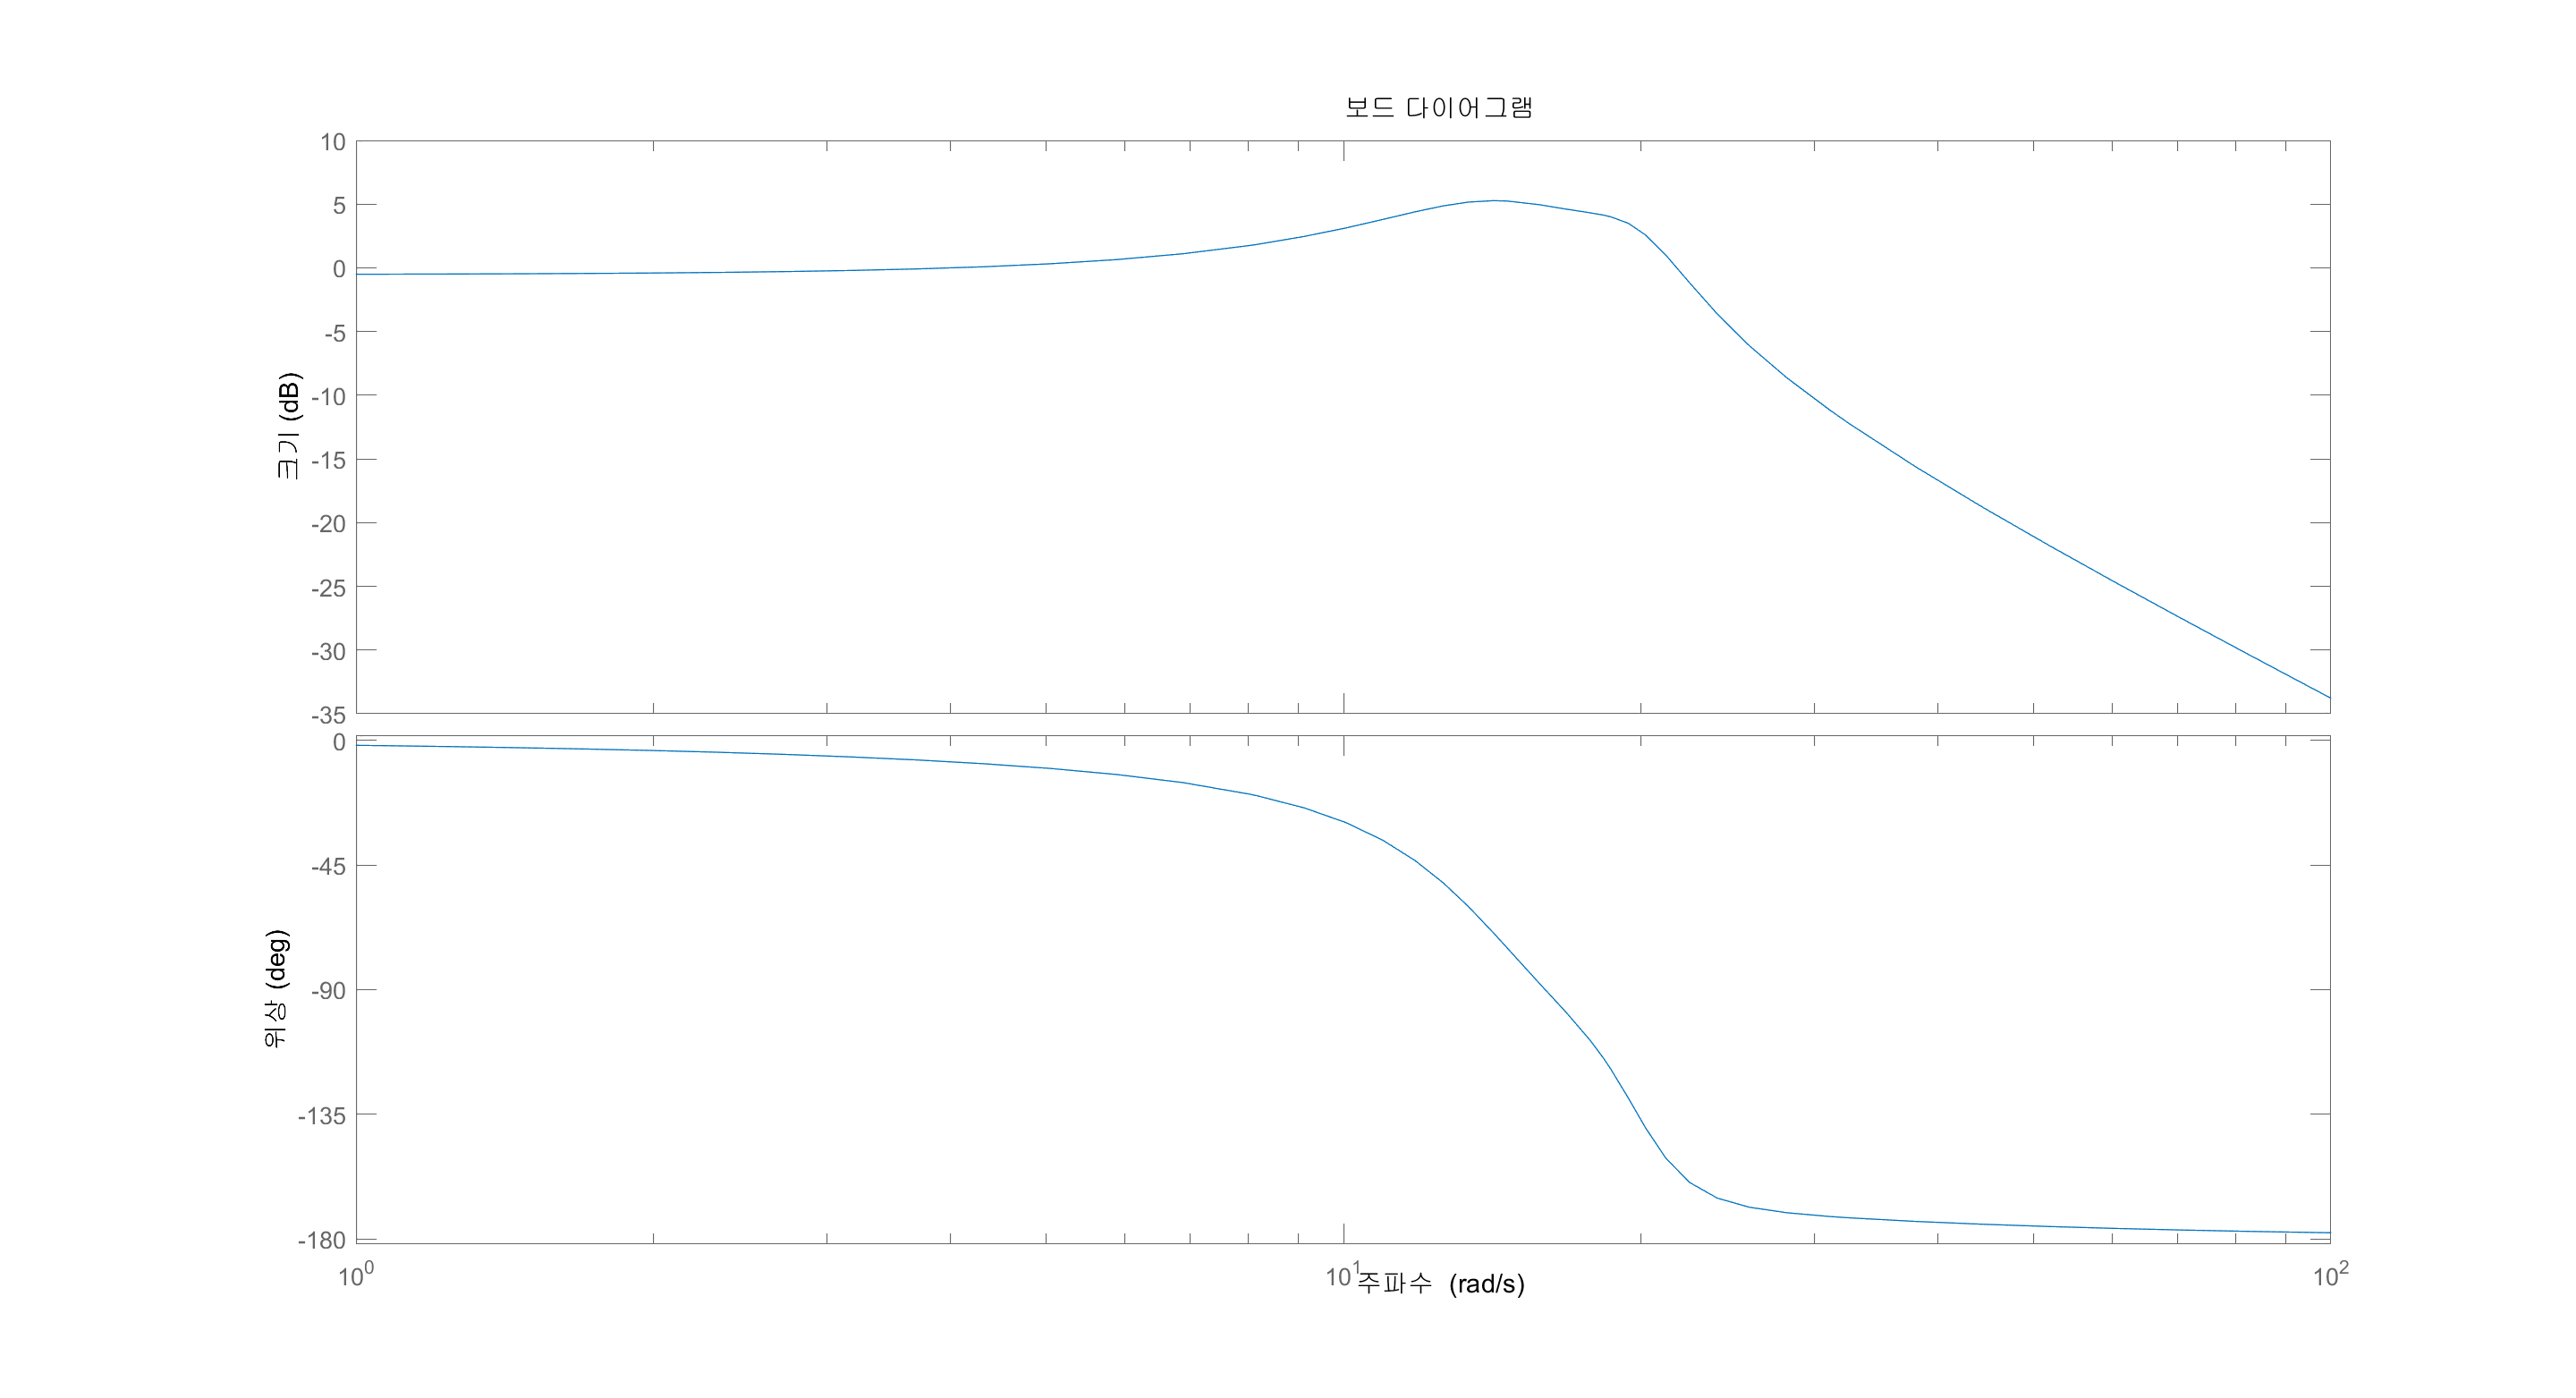

bode(T2)

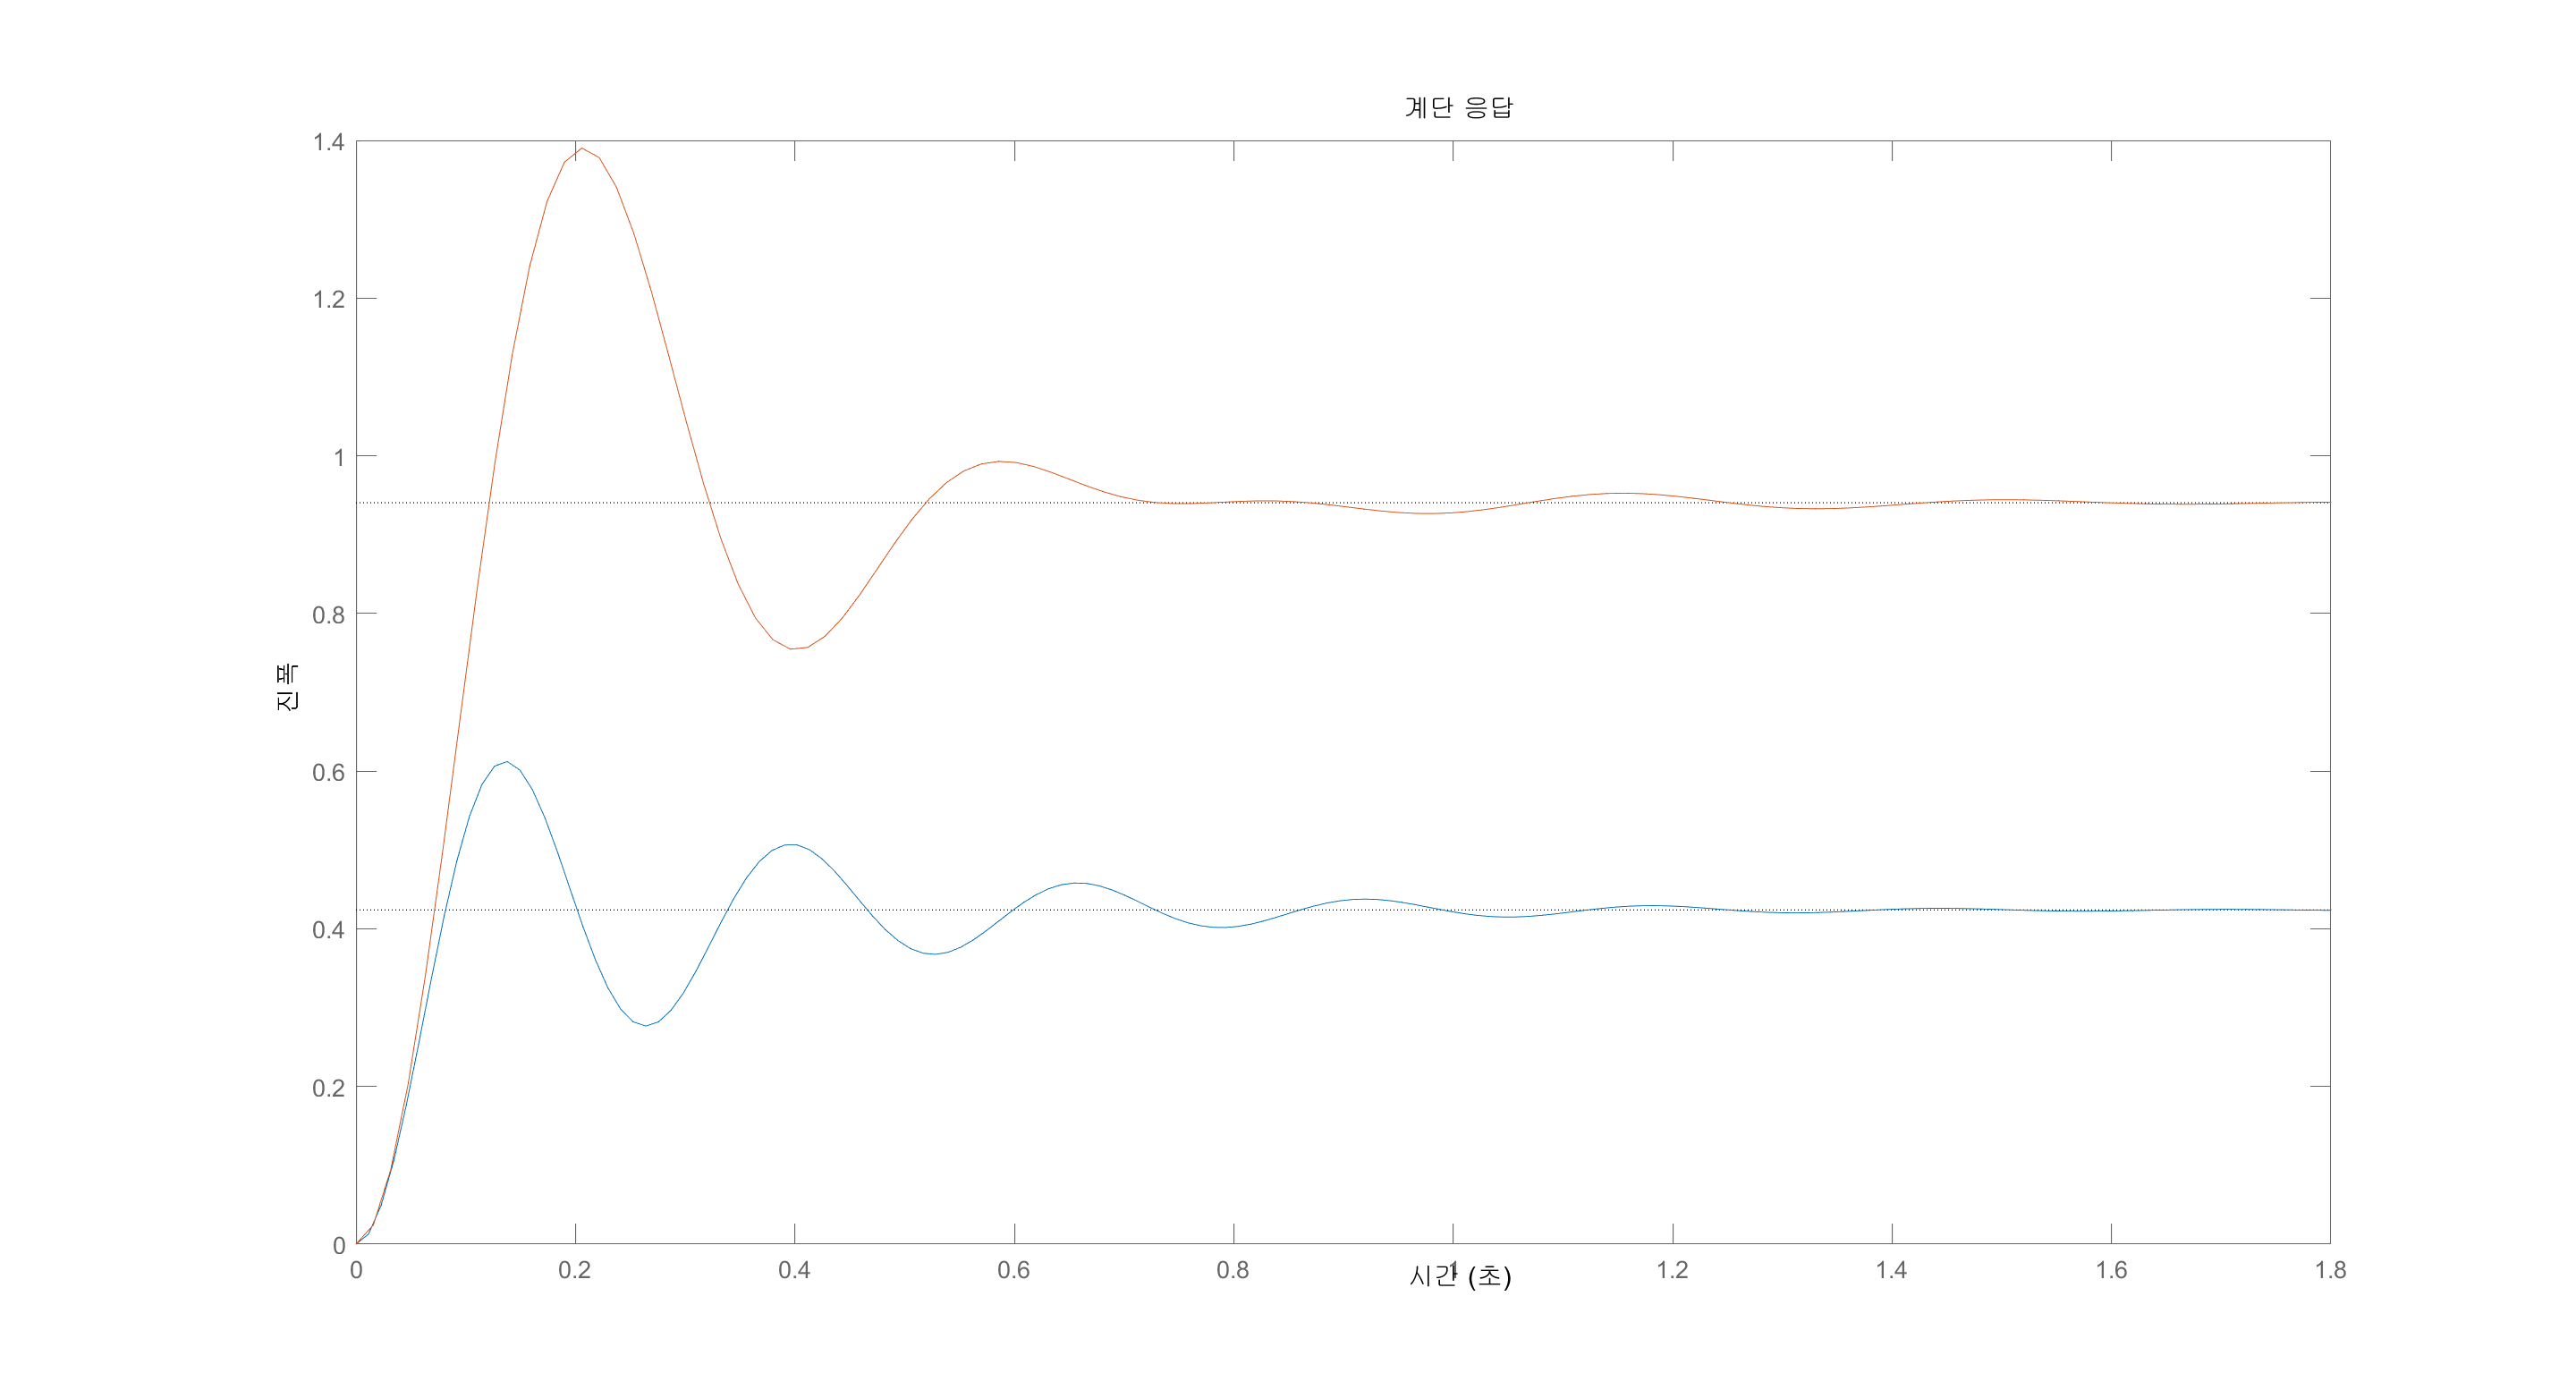

step(T1, T2)

Aproximate pole-zero for comparing

numg=poly(-10); % Generate numerator of G(s).
deng=poly([-3 -6 -7]); % Generate denominator of G(s).
G=tf(numg,deng) % Create and display G(s).

G =
 
           s + 10
  -------------------------
  s^3 + 16 s^2 + 81 s + 126
 
연속시간 전달 함수입니다.



s = tf('s');

z=0.144

z = 0.1440

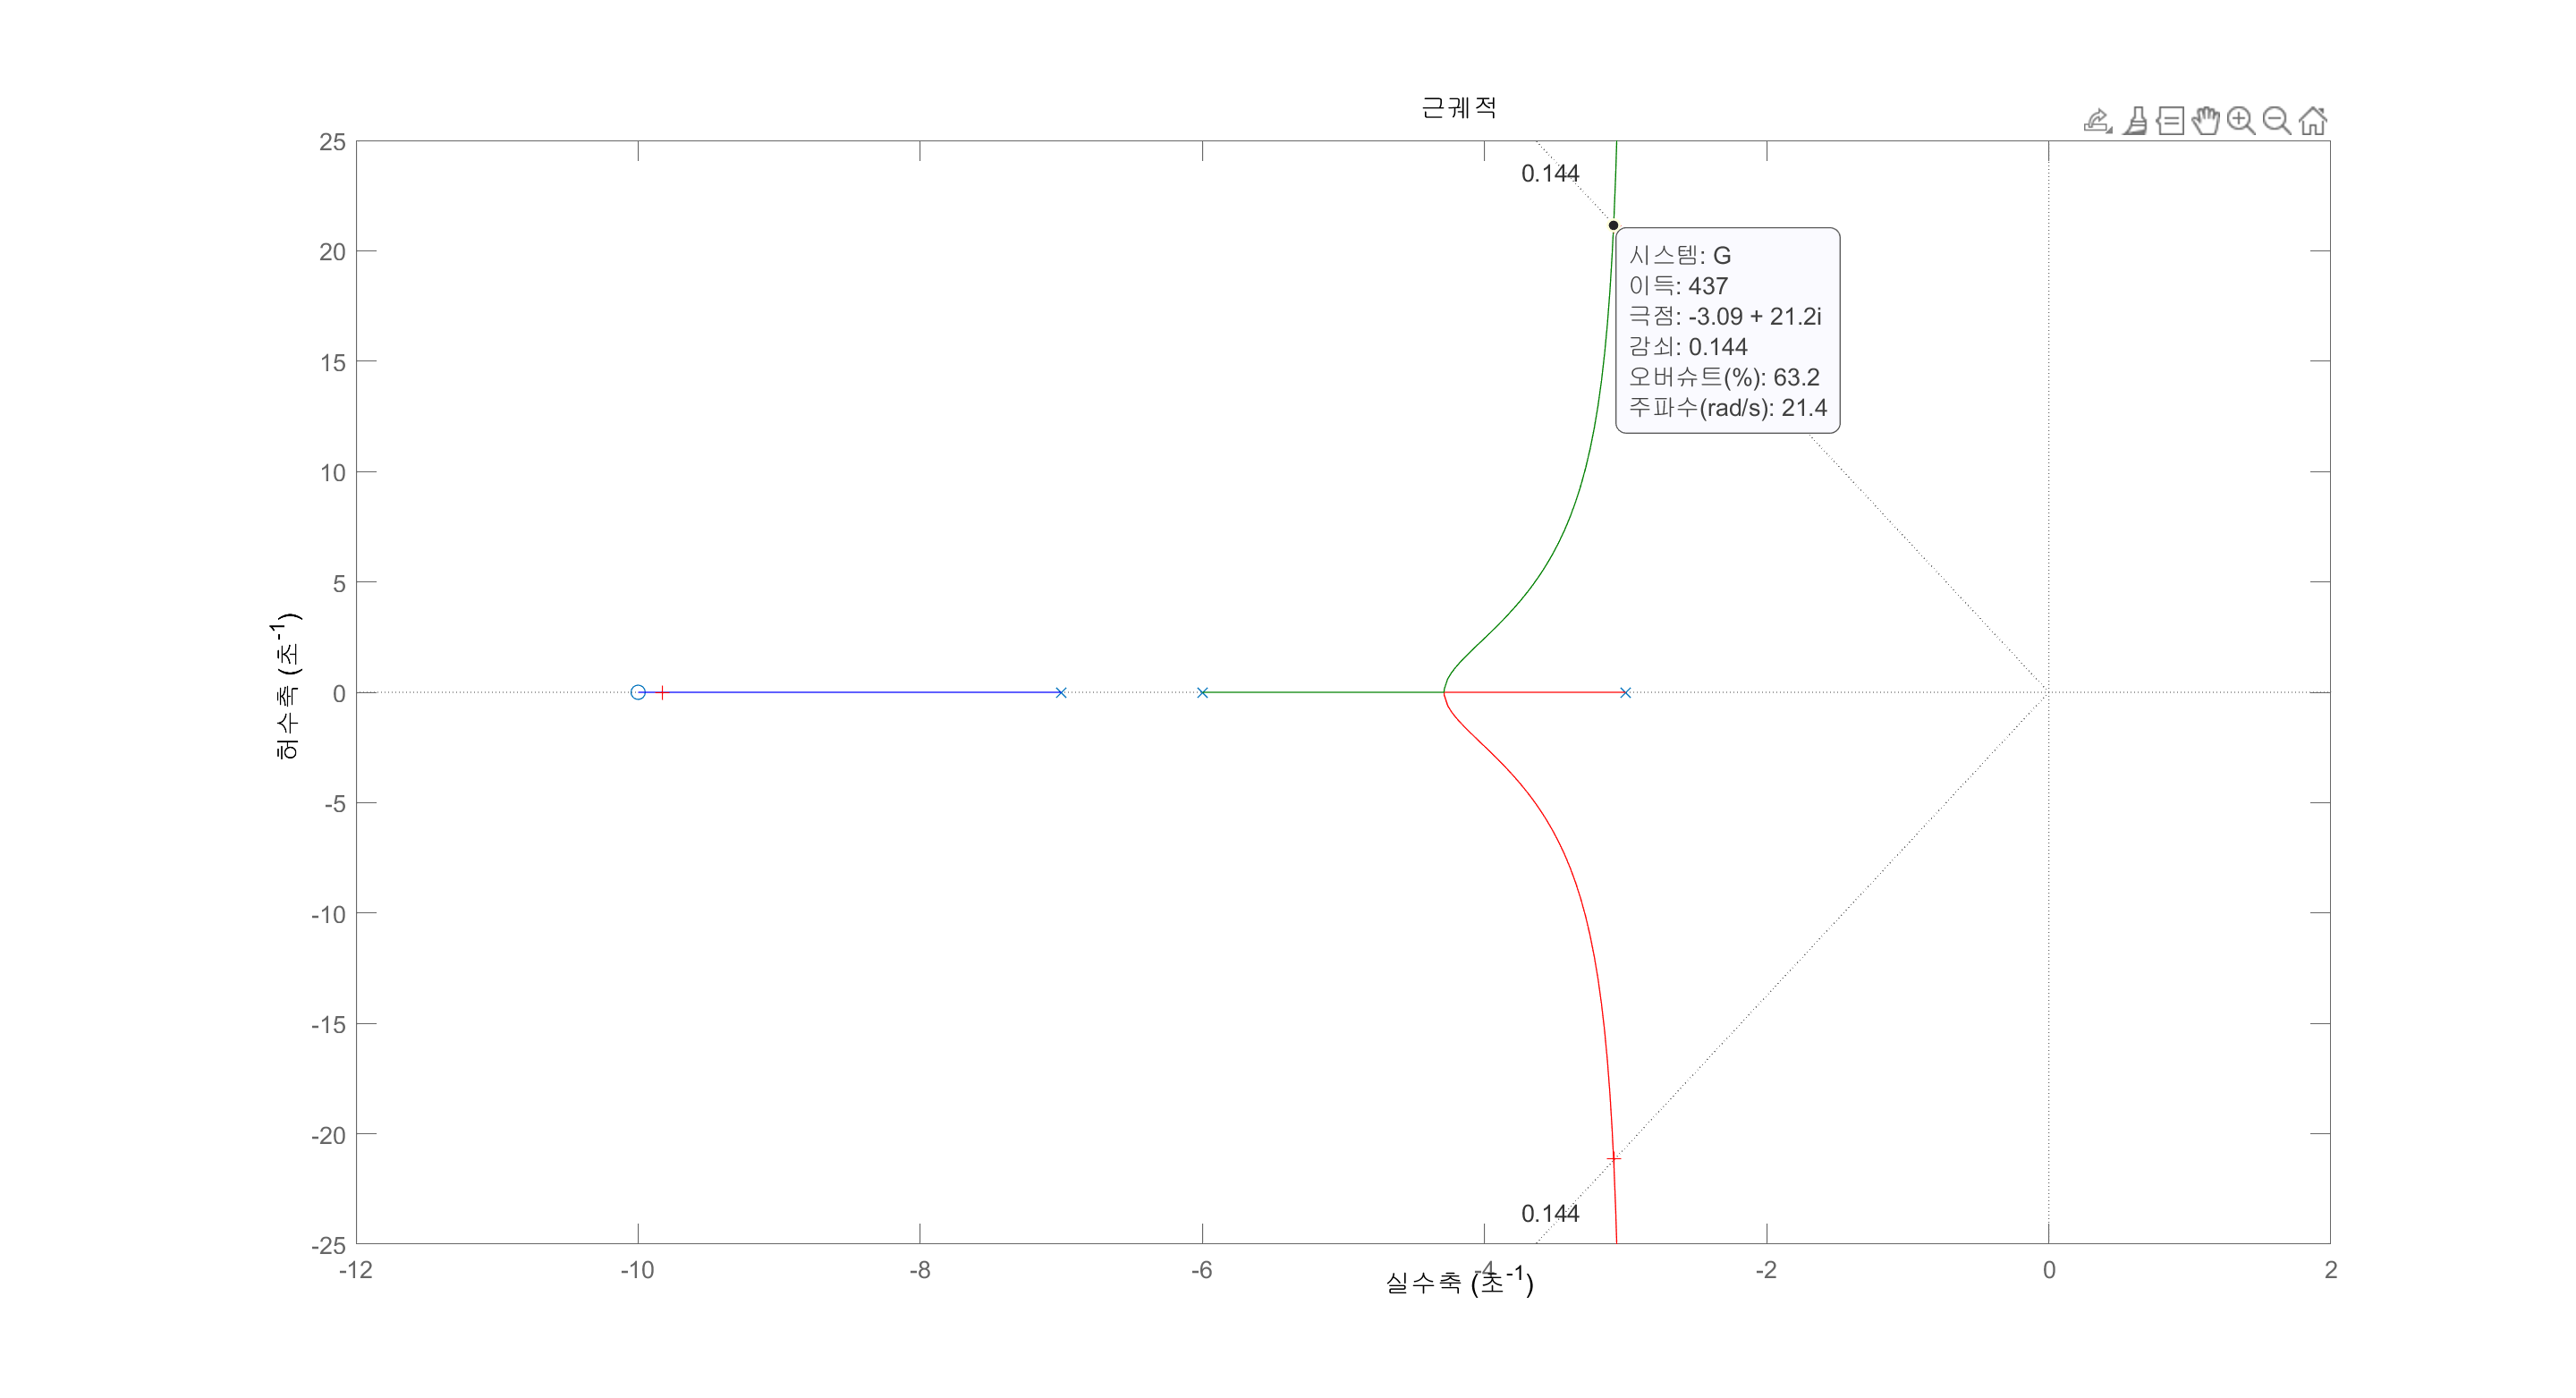

Select a point in the graphics window


selected_point = -3.0820 + 21.1305i

K = 435.6656

p =   -3.0850 +21.1305i
  -3.0850 -21.1305i
  -9.8301 + 0.0000i


rlocus(G) % Plot uncompensated root locus.
sgrid(z,0) % Overlay desired percent
[K,p]=rlocfind(G) 

Kp = 441;
Err_constant = dcgain(Kp*G)

Err_constant = 35

ess = 1/(1+Err_constant)

ess = 0.0278

T = feedback(Kp*G, 1)

T =
 
         441 s + 4410
  ---------------------------
  s^3 + 16 s^2 + 522 s + 4536
 
연속시간 전달 함수입니다.



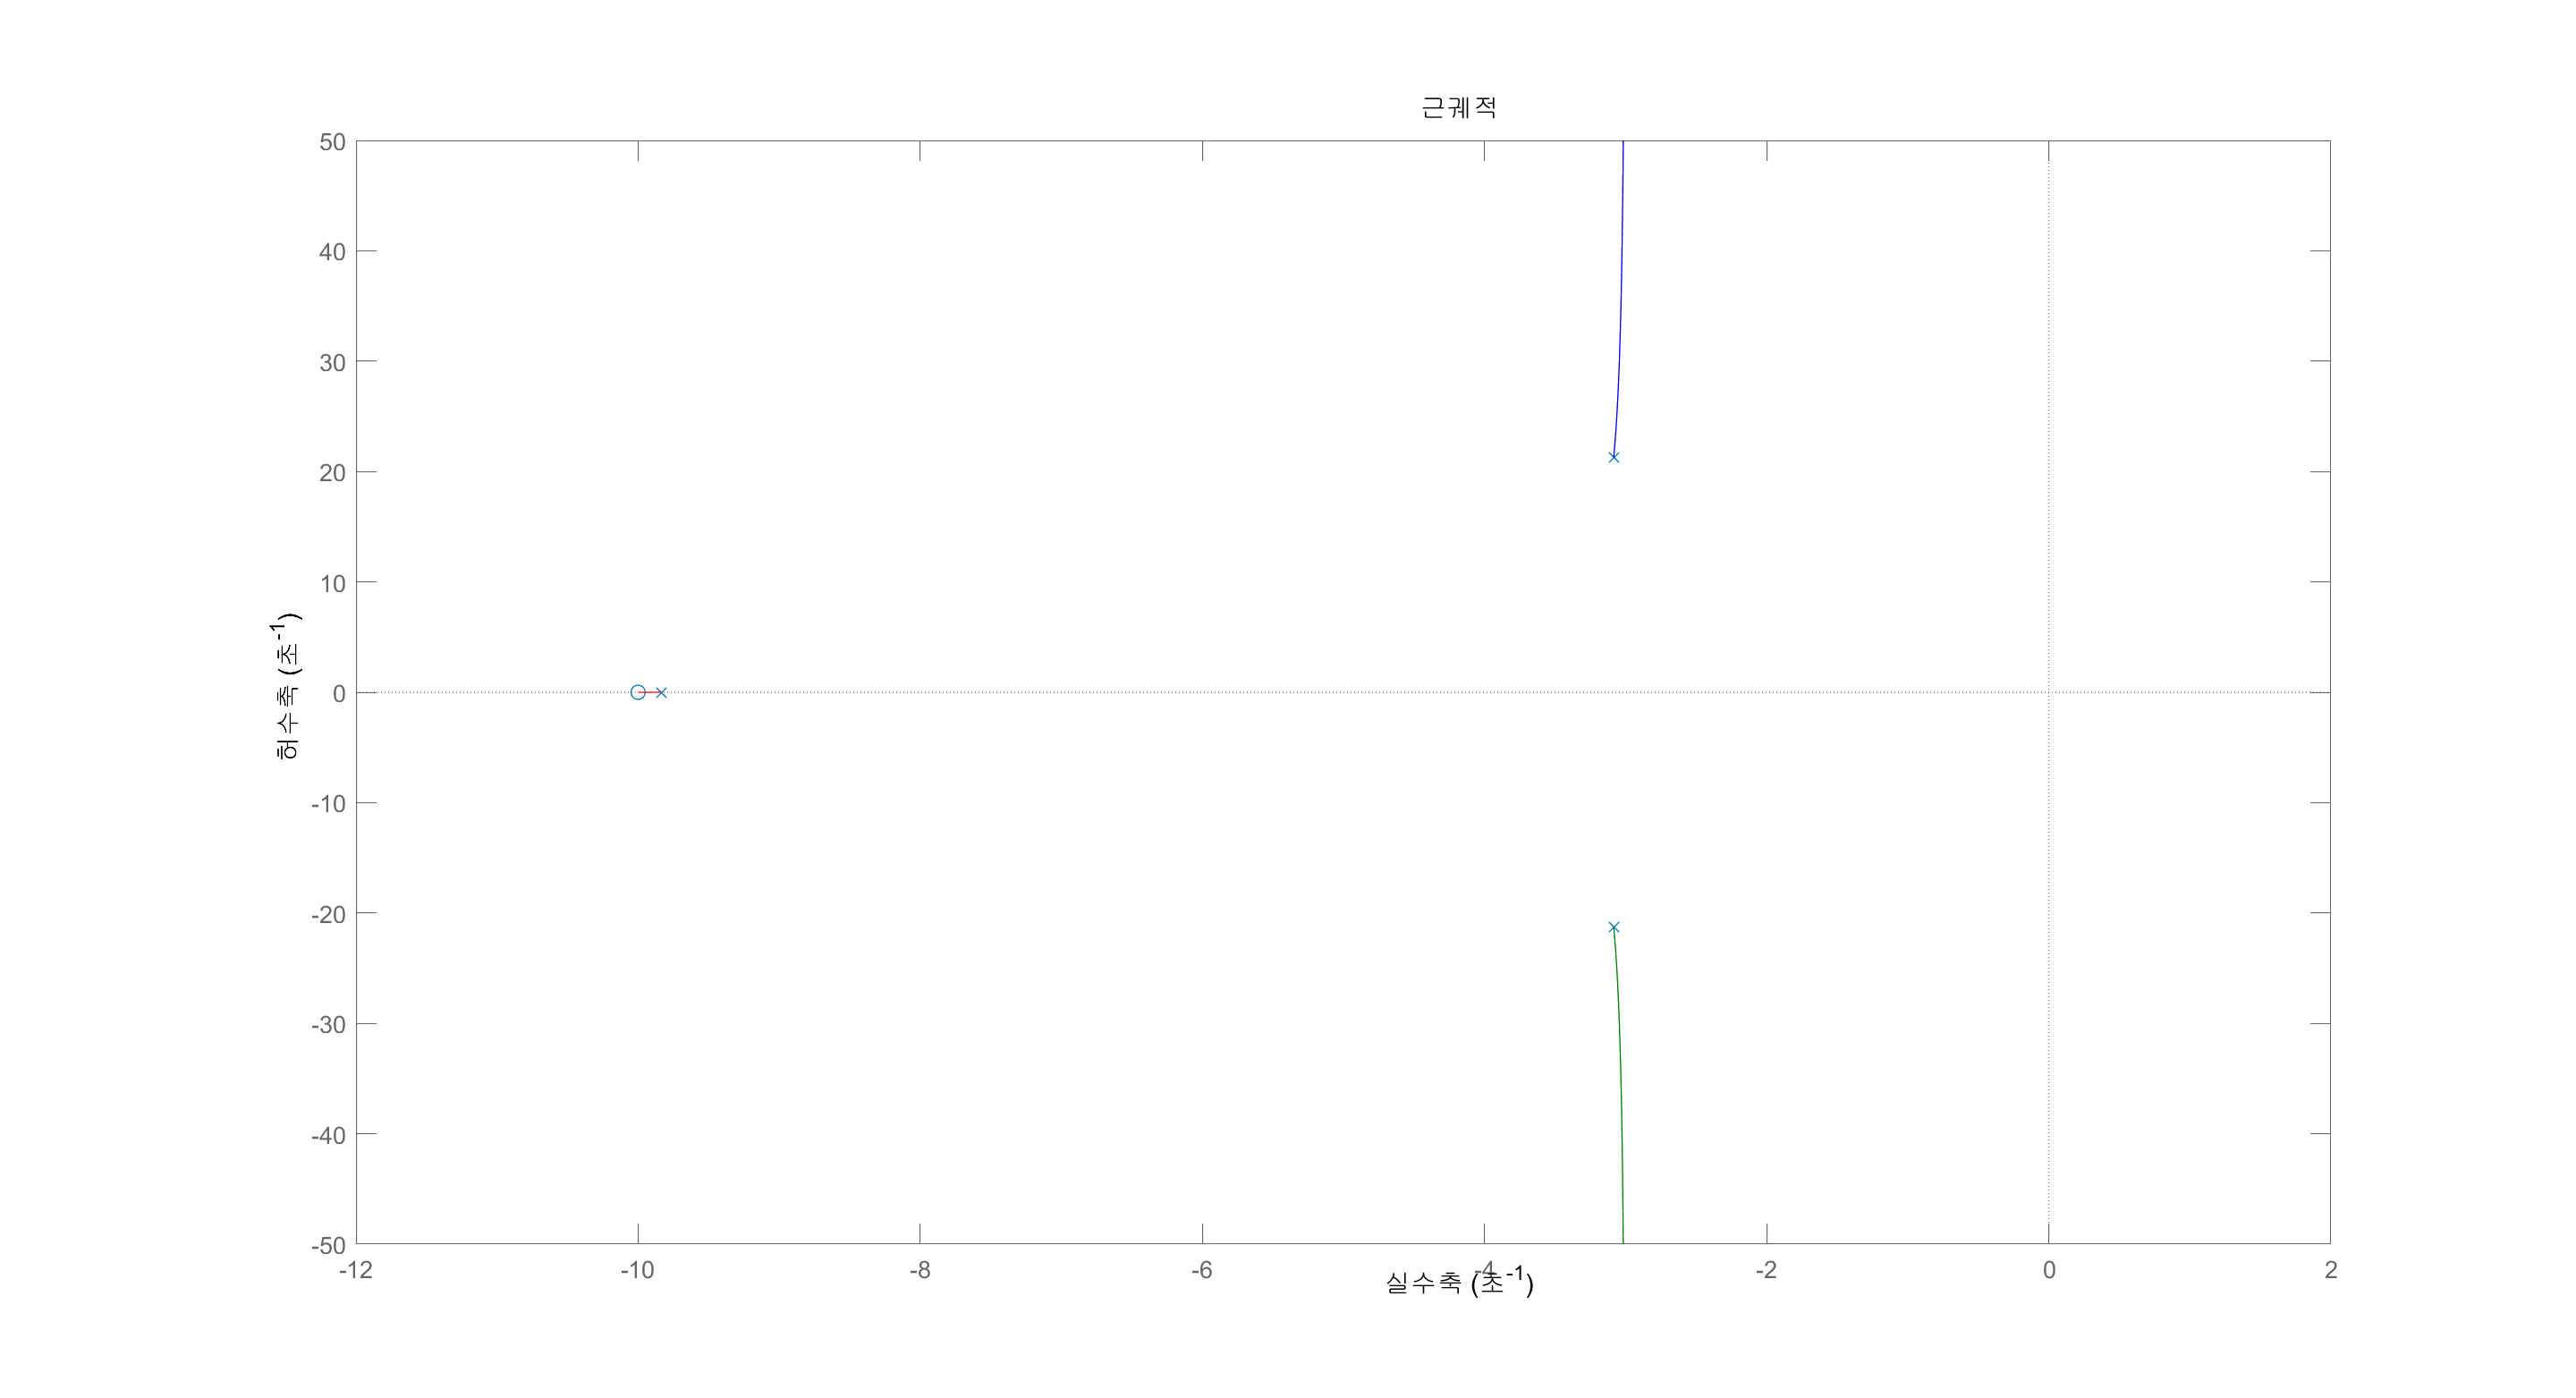

rlocus(T)

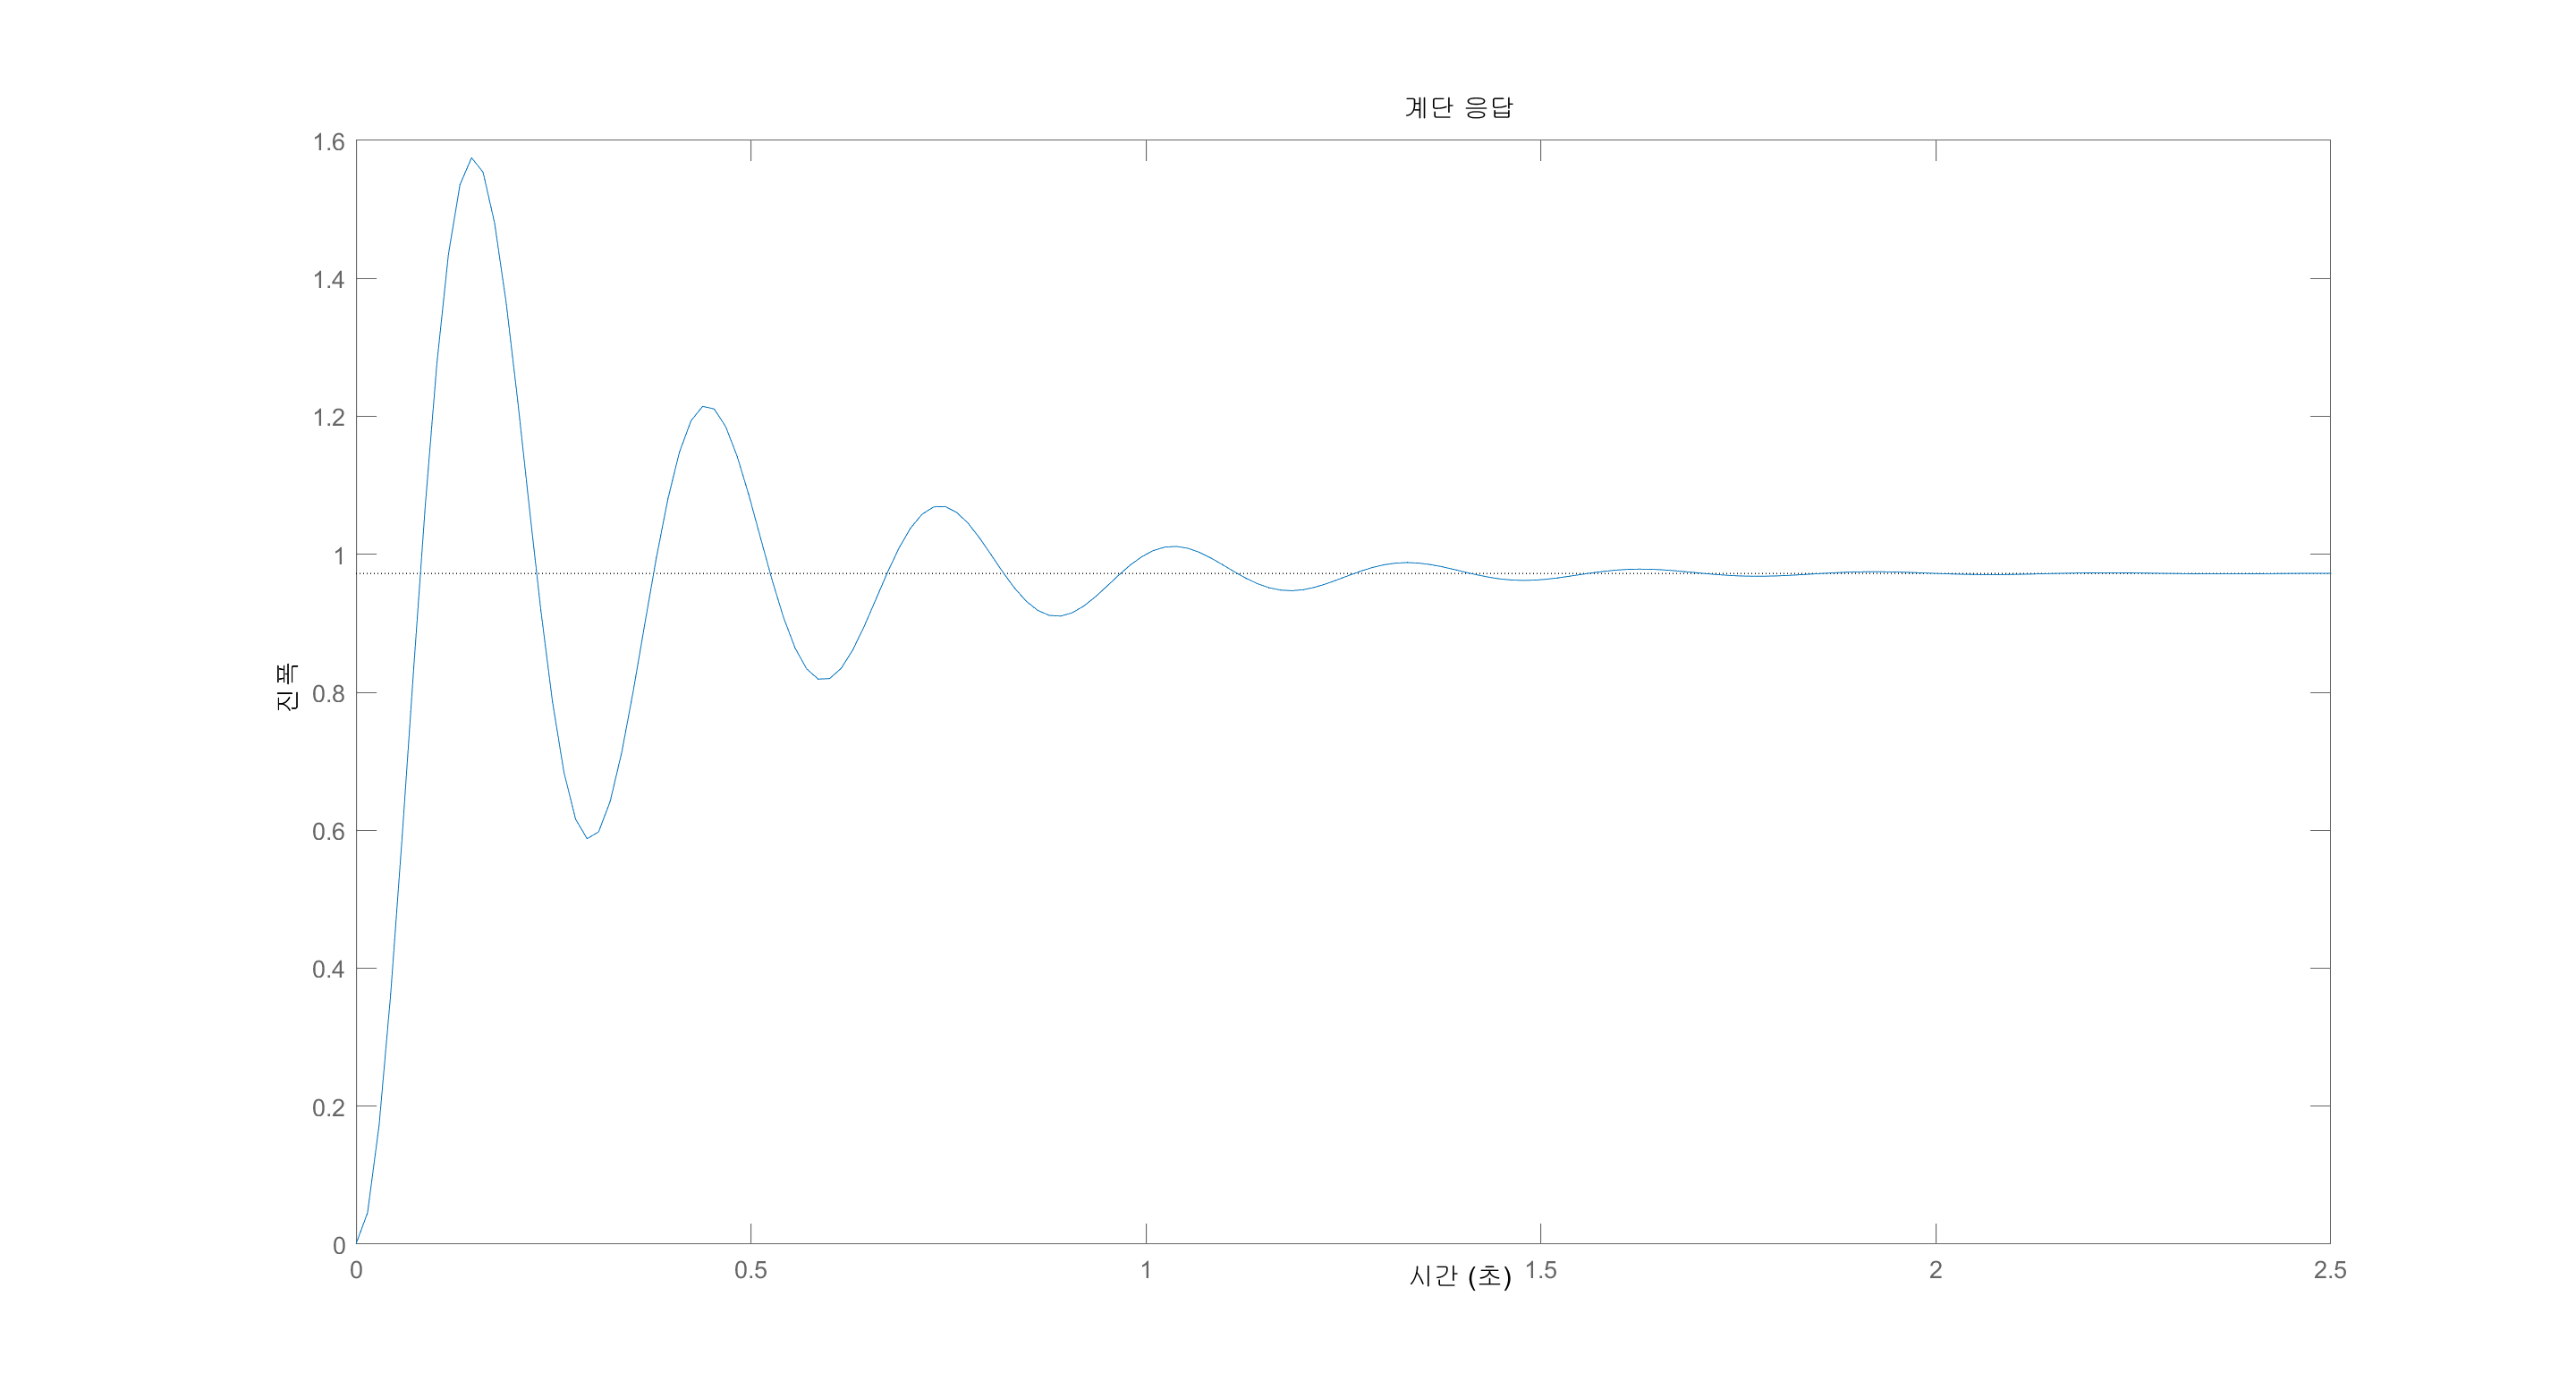

step(T)

stepinfo(T)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.0550
    TransientTime: 1.2152
     SettlingTime: 1.2152
      SettlingMin: 0.5878
      SettlingMax: 1.5749
        Overshoot: 61.9863
       Undershoot: 0
             Peak: 1.5749
         PeakTime: 0.1463
